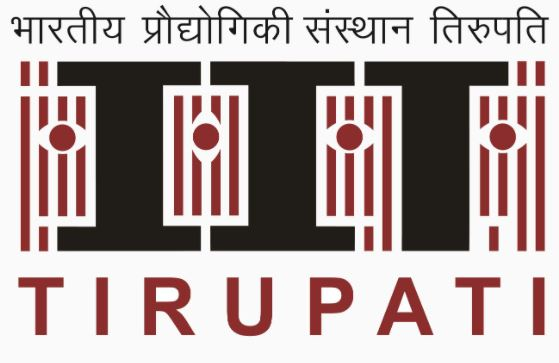

### **Digital Signal Processing Laboratory**

**LabSheet-01**

Name: Suriyaa MM

Roll Number: EE23B054

## **Discrete Time Sinusoids and Exponentials**

**A. Properties of Sinusoids**

**I. Frequencies Separated by Interval 2 pi**


$$$x(t) = A * cos((\omega_0 + (2 * \pi * k)) * t + \phi) $$$



$$$x[n] = A * cos[(\omega_0 + (2 * \pi * k)) * n + \phi] $$$


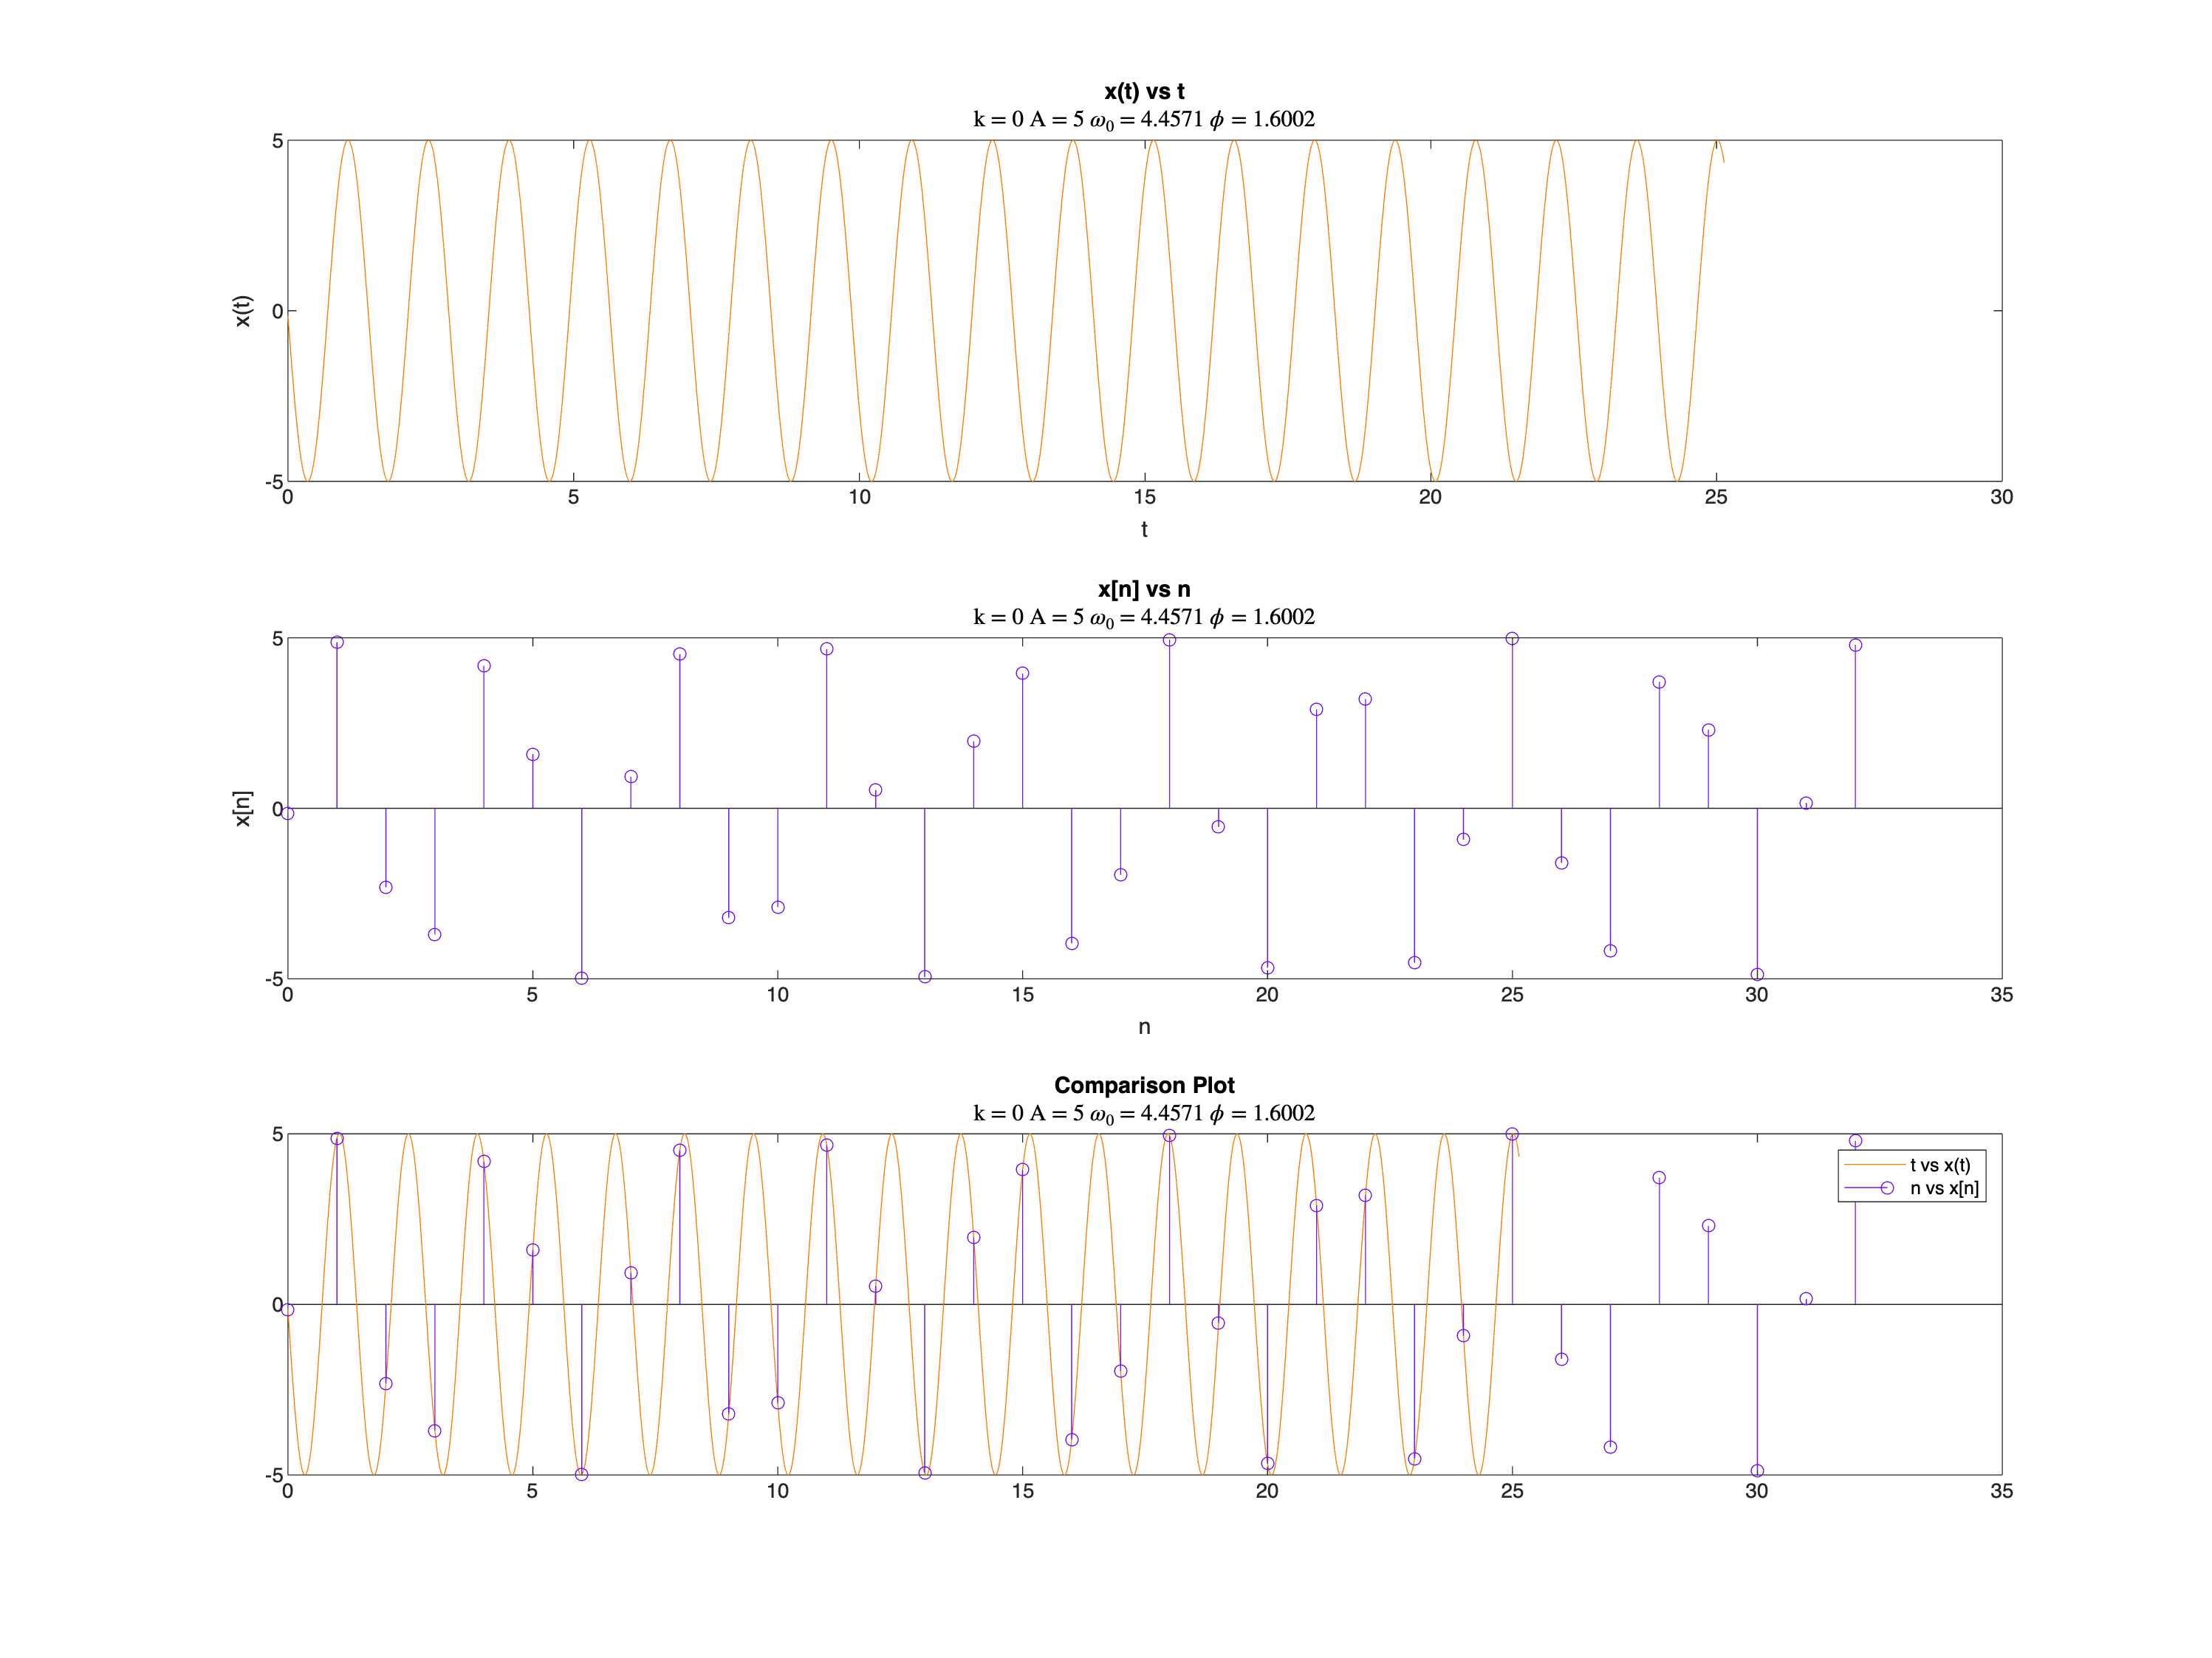

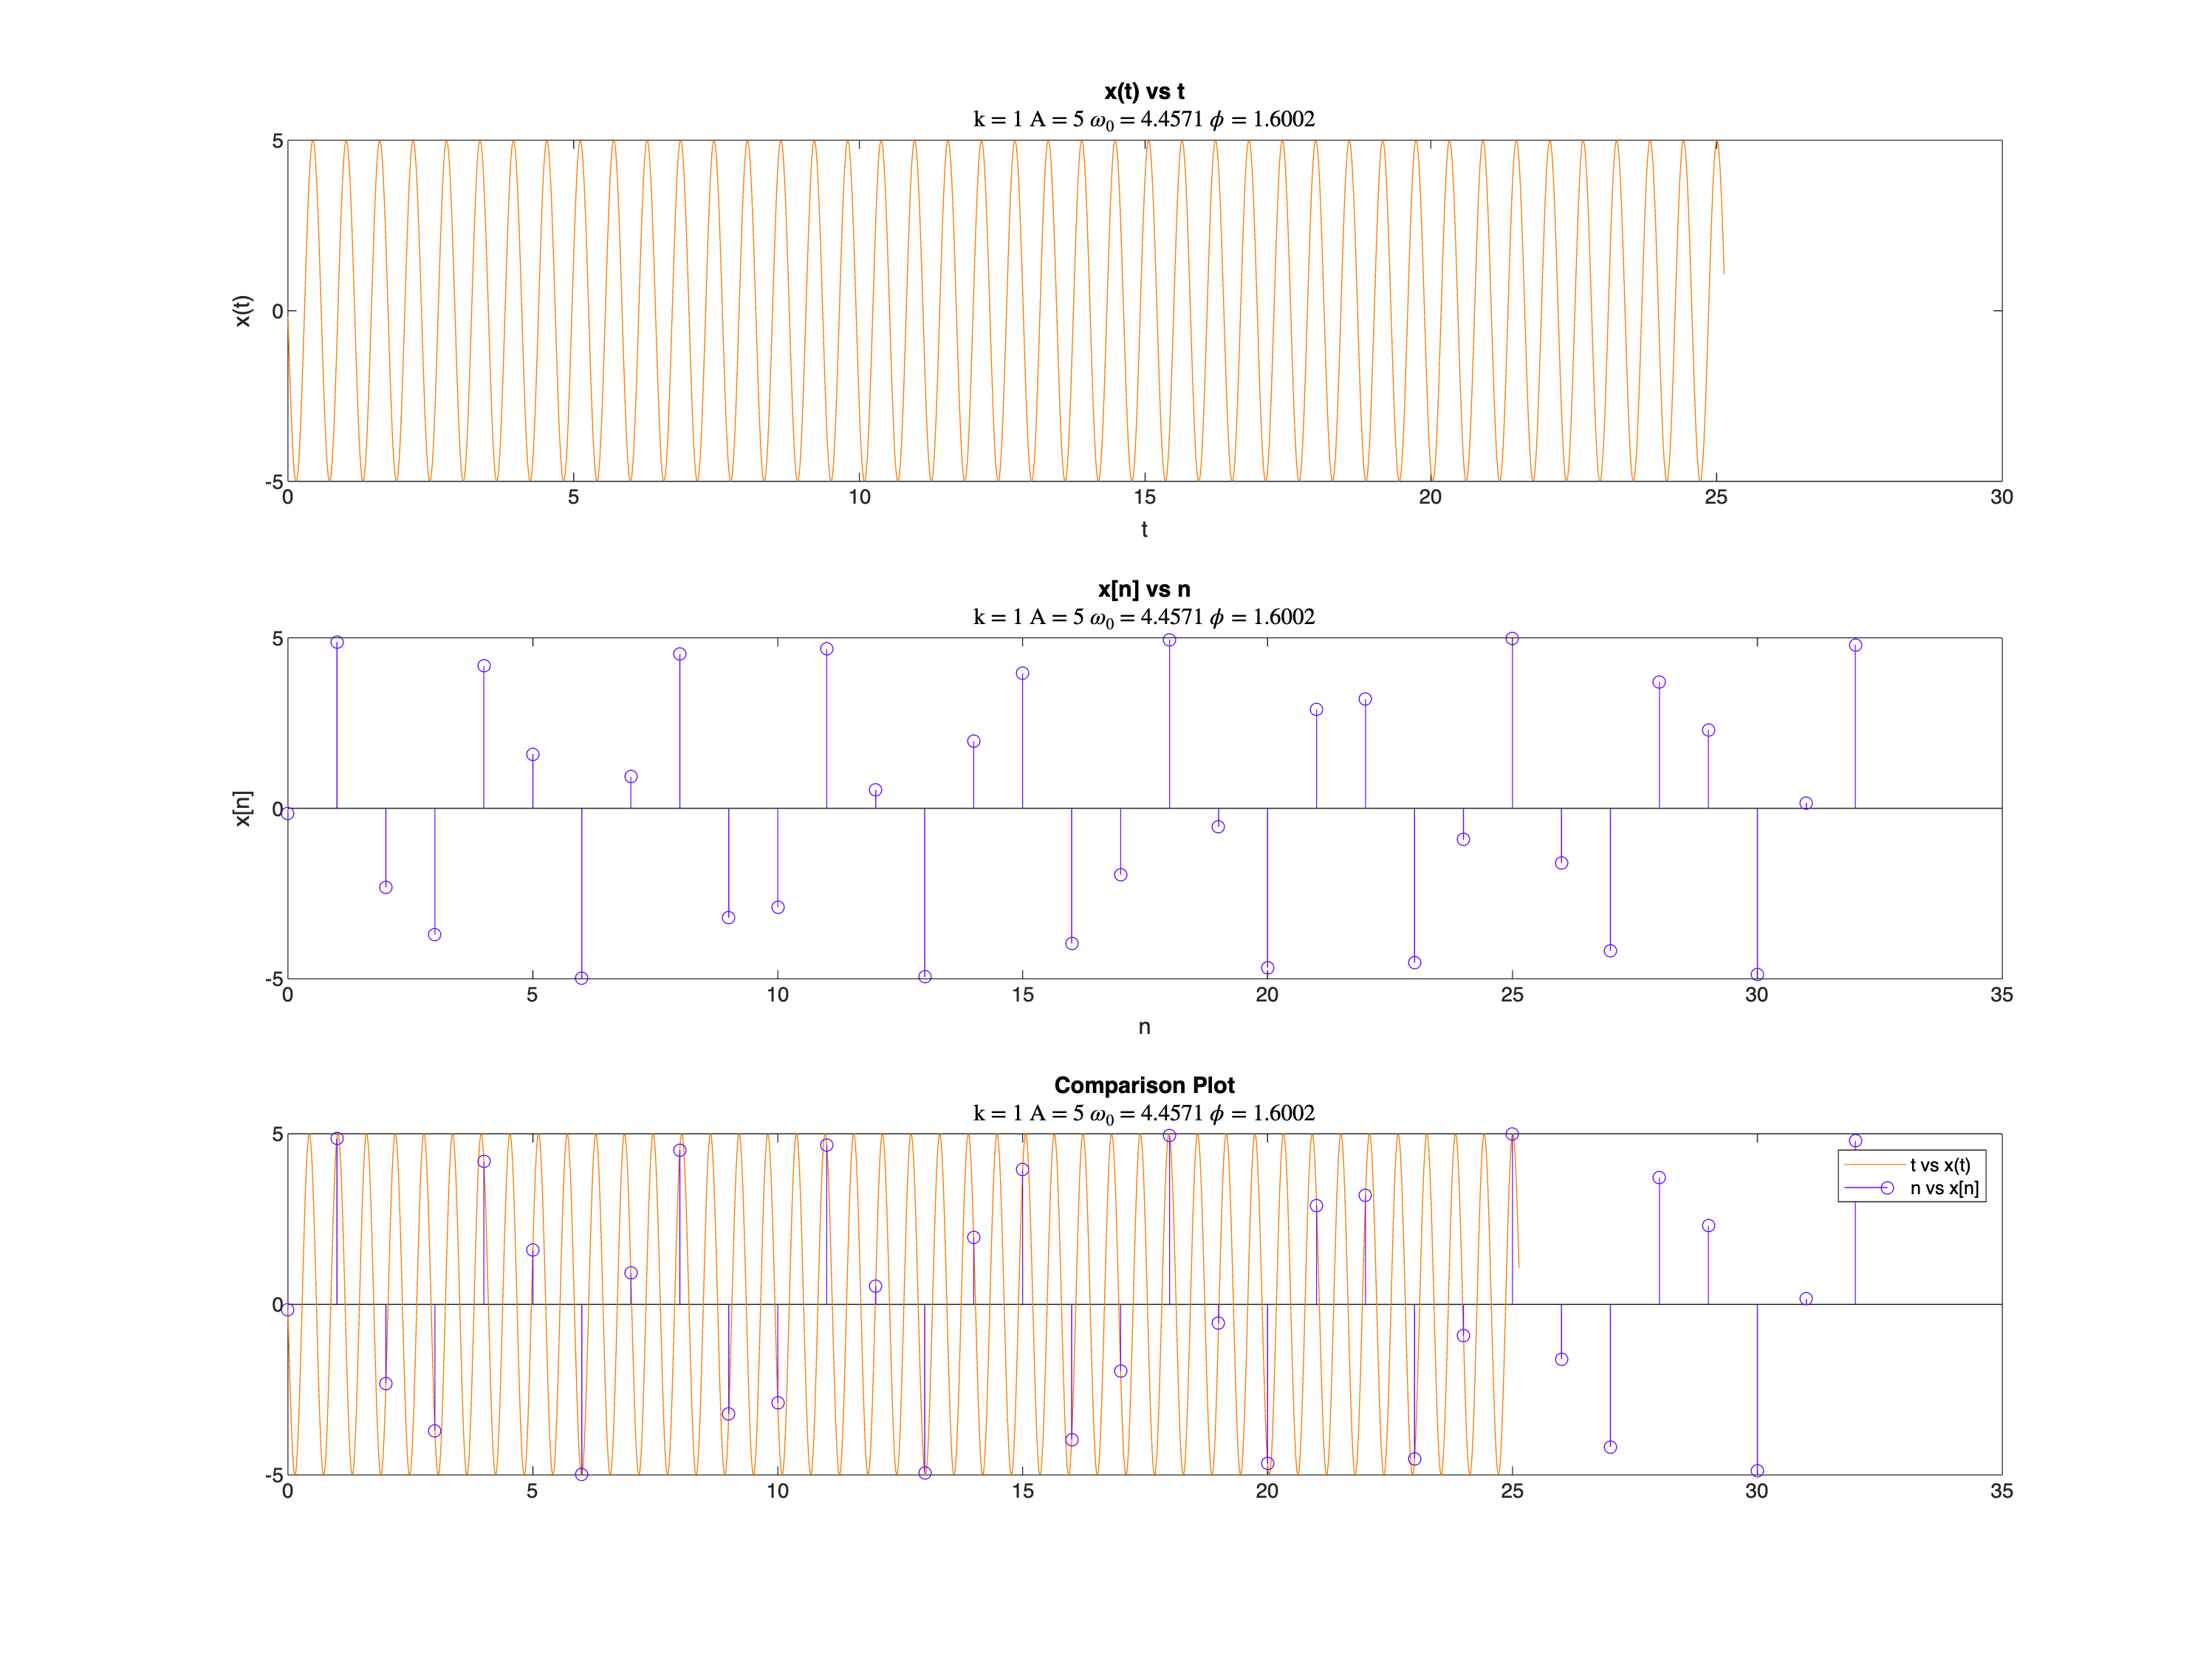

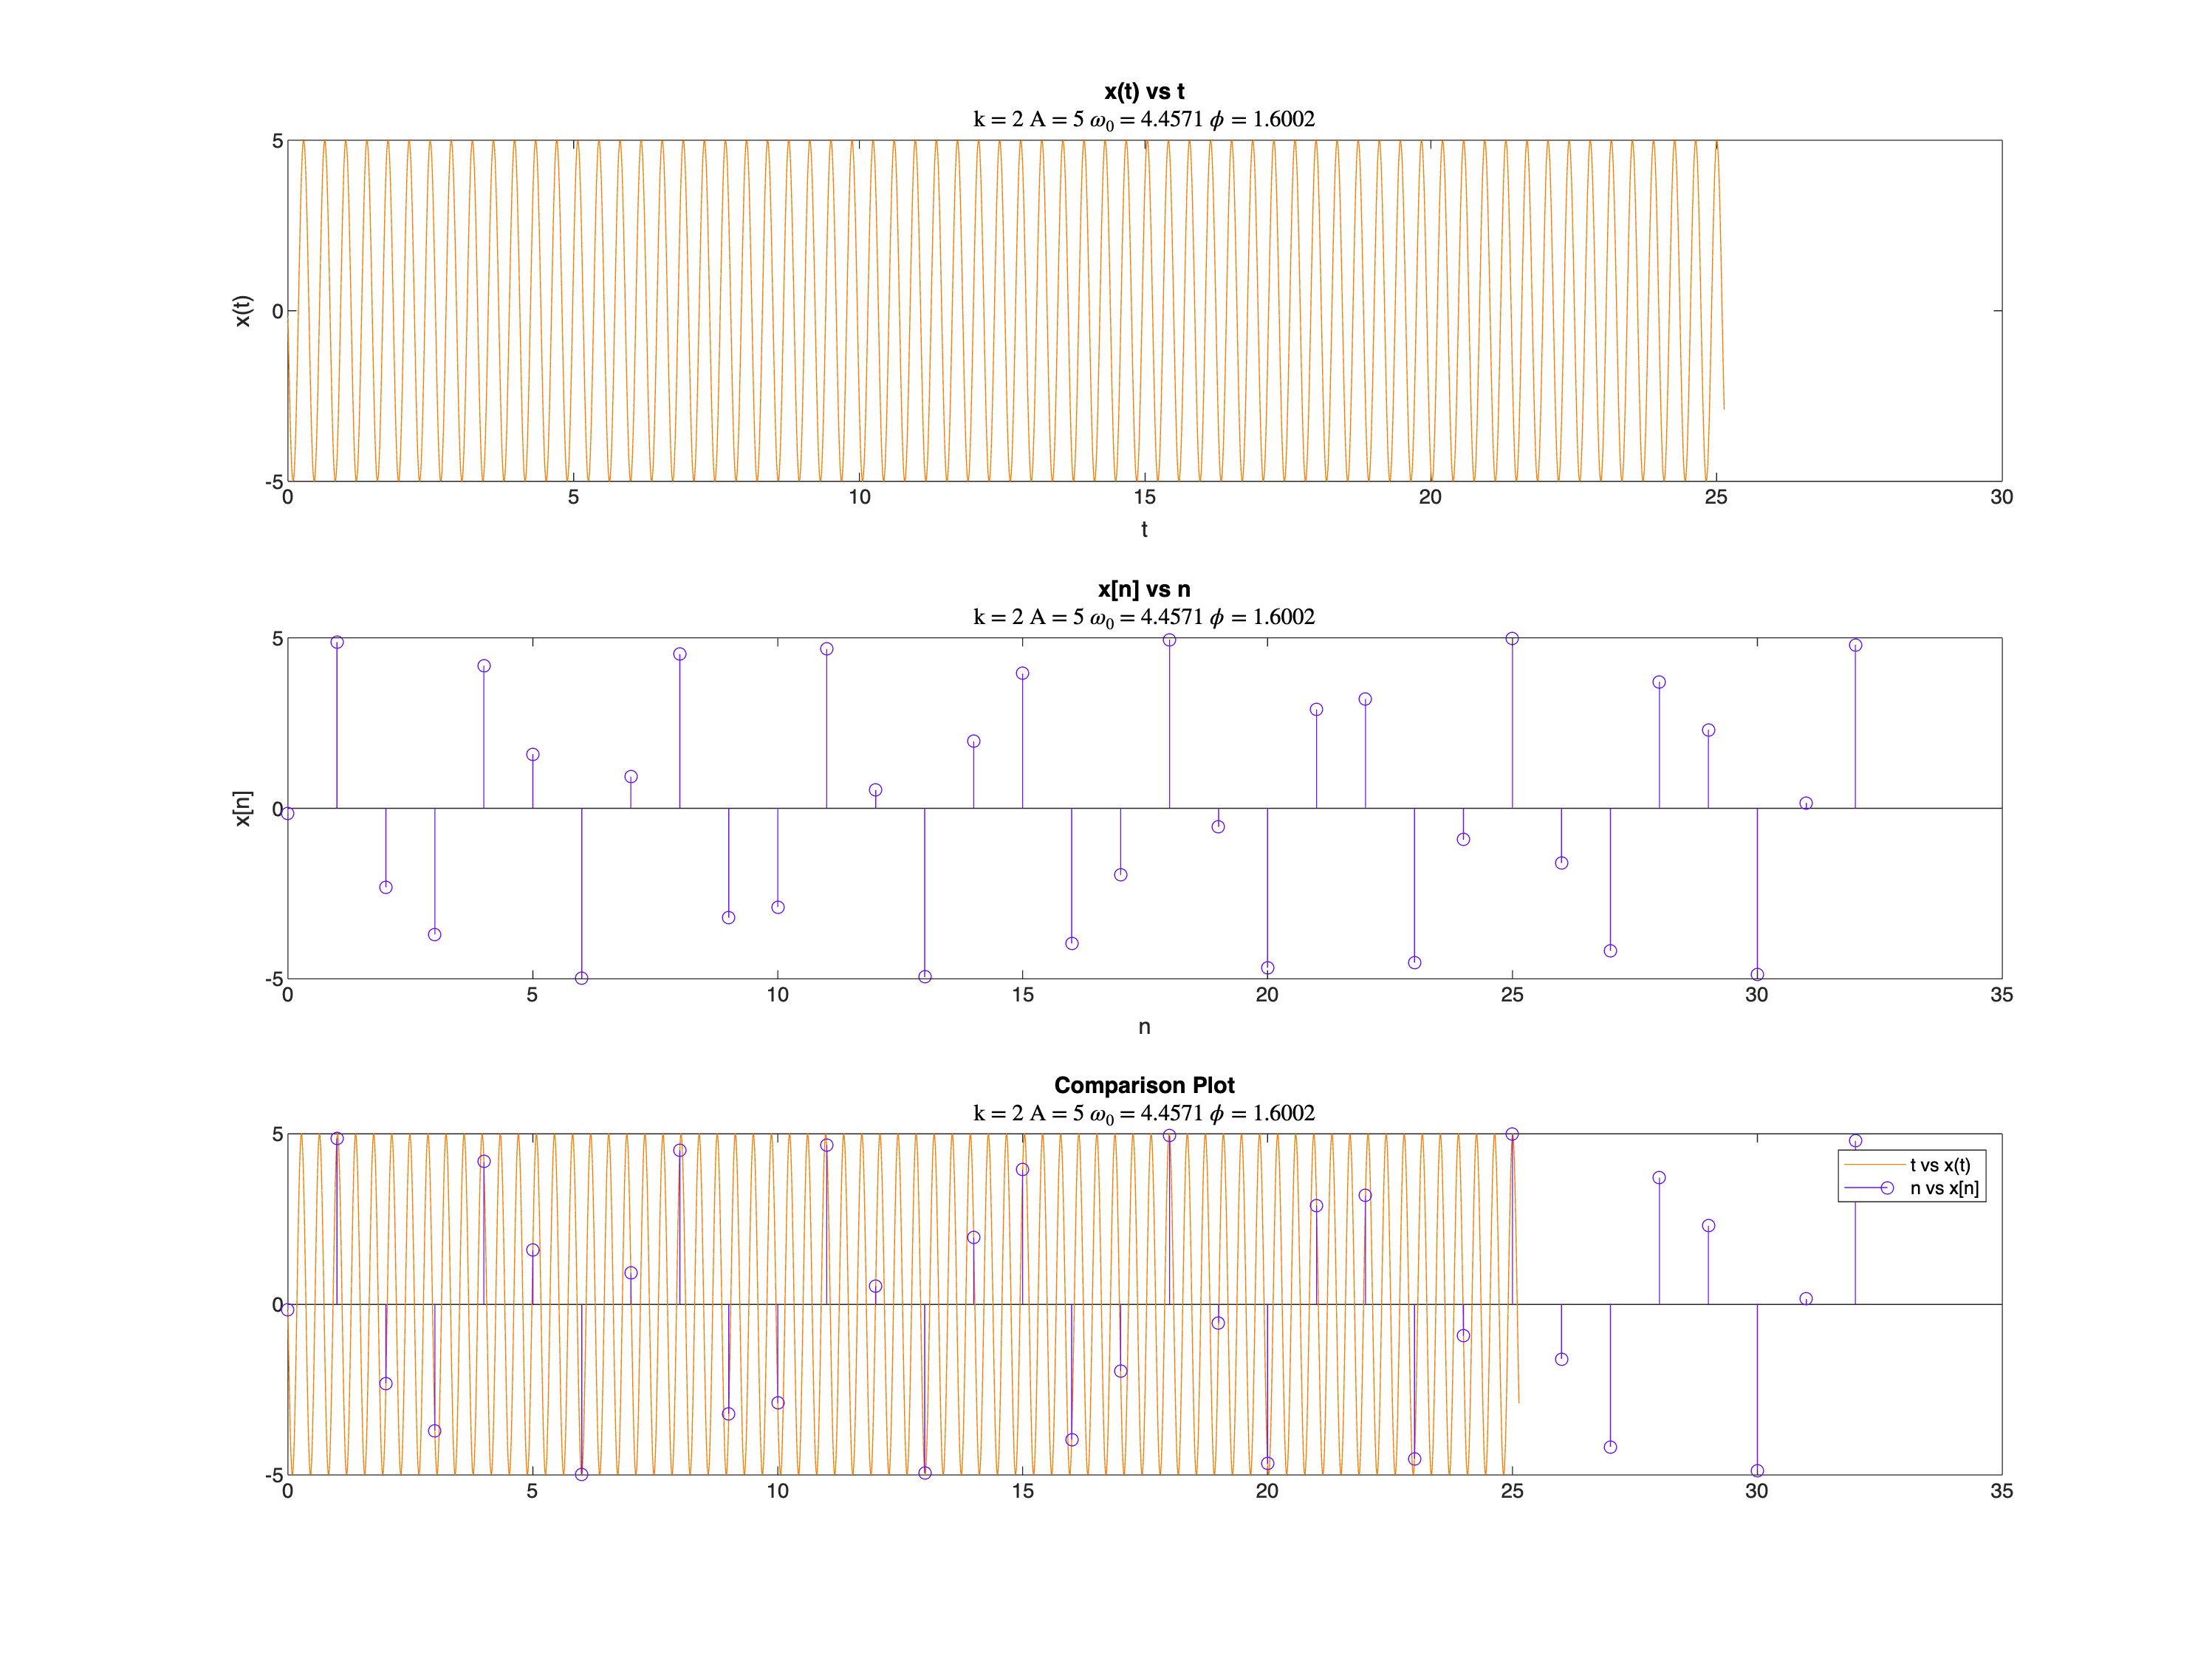

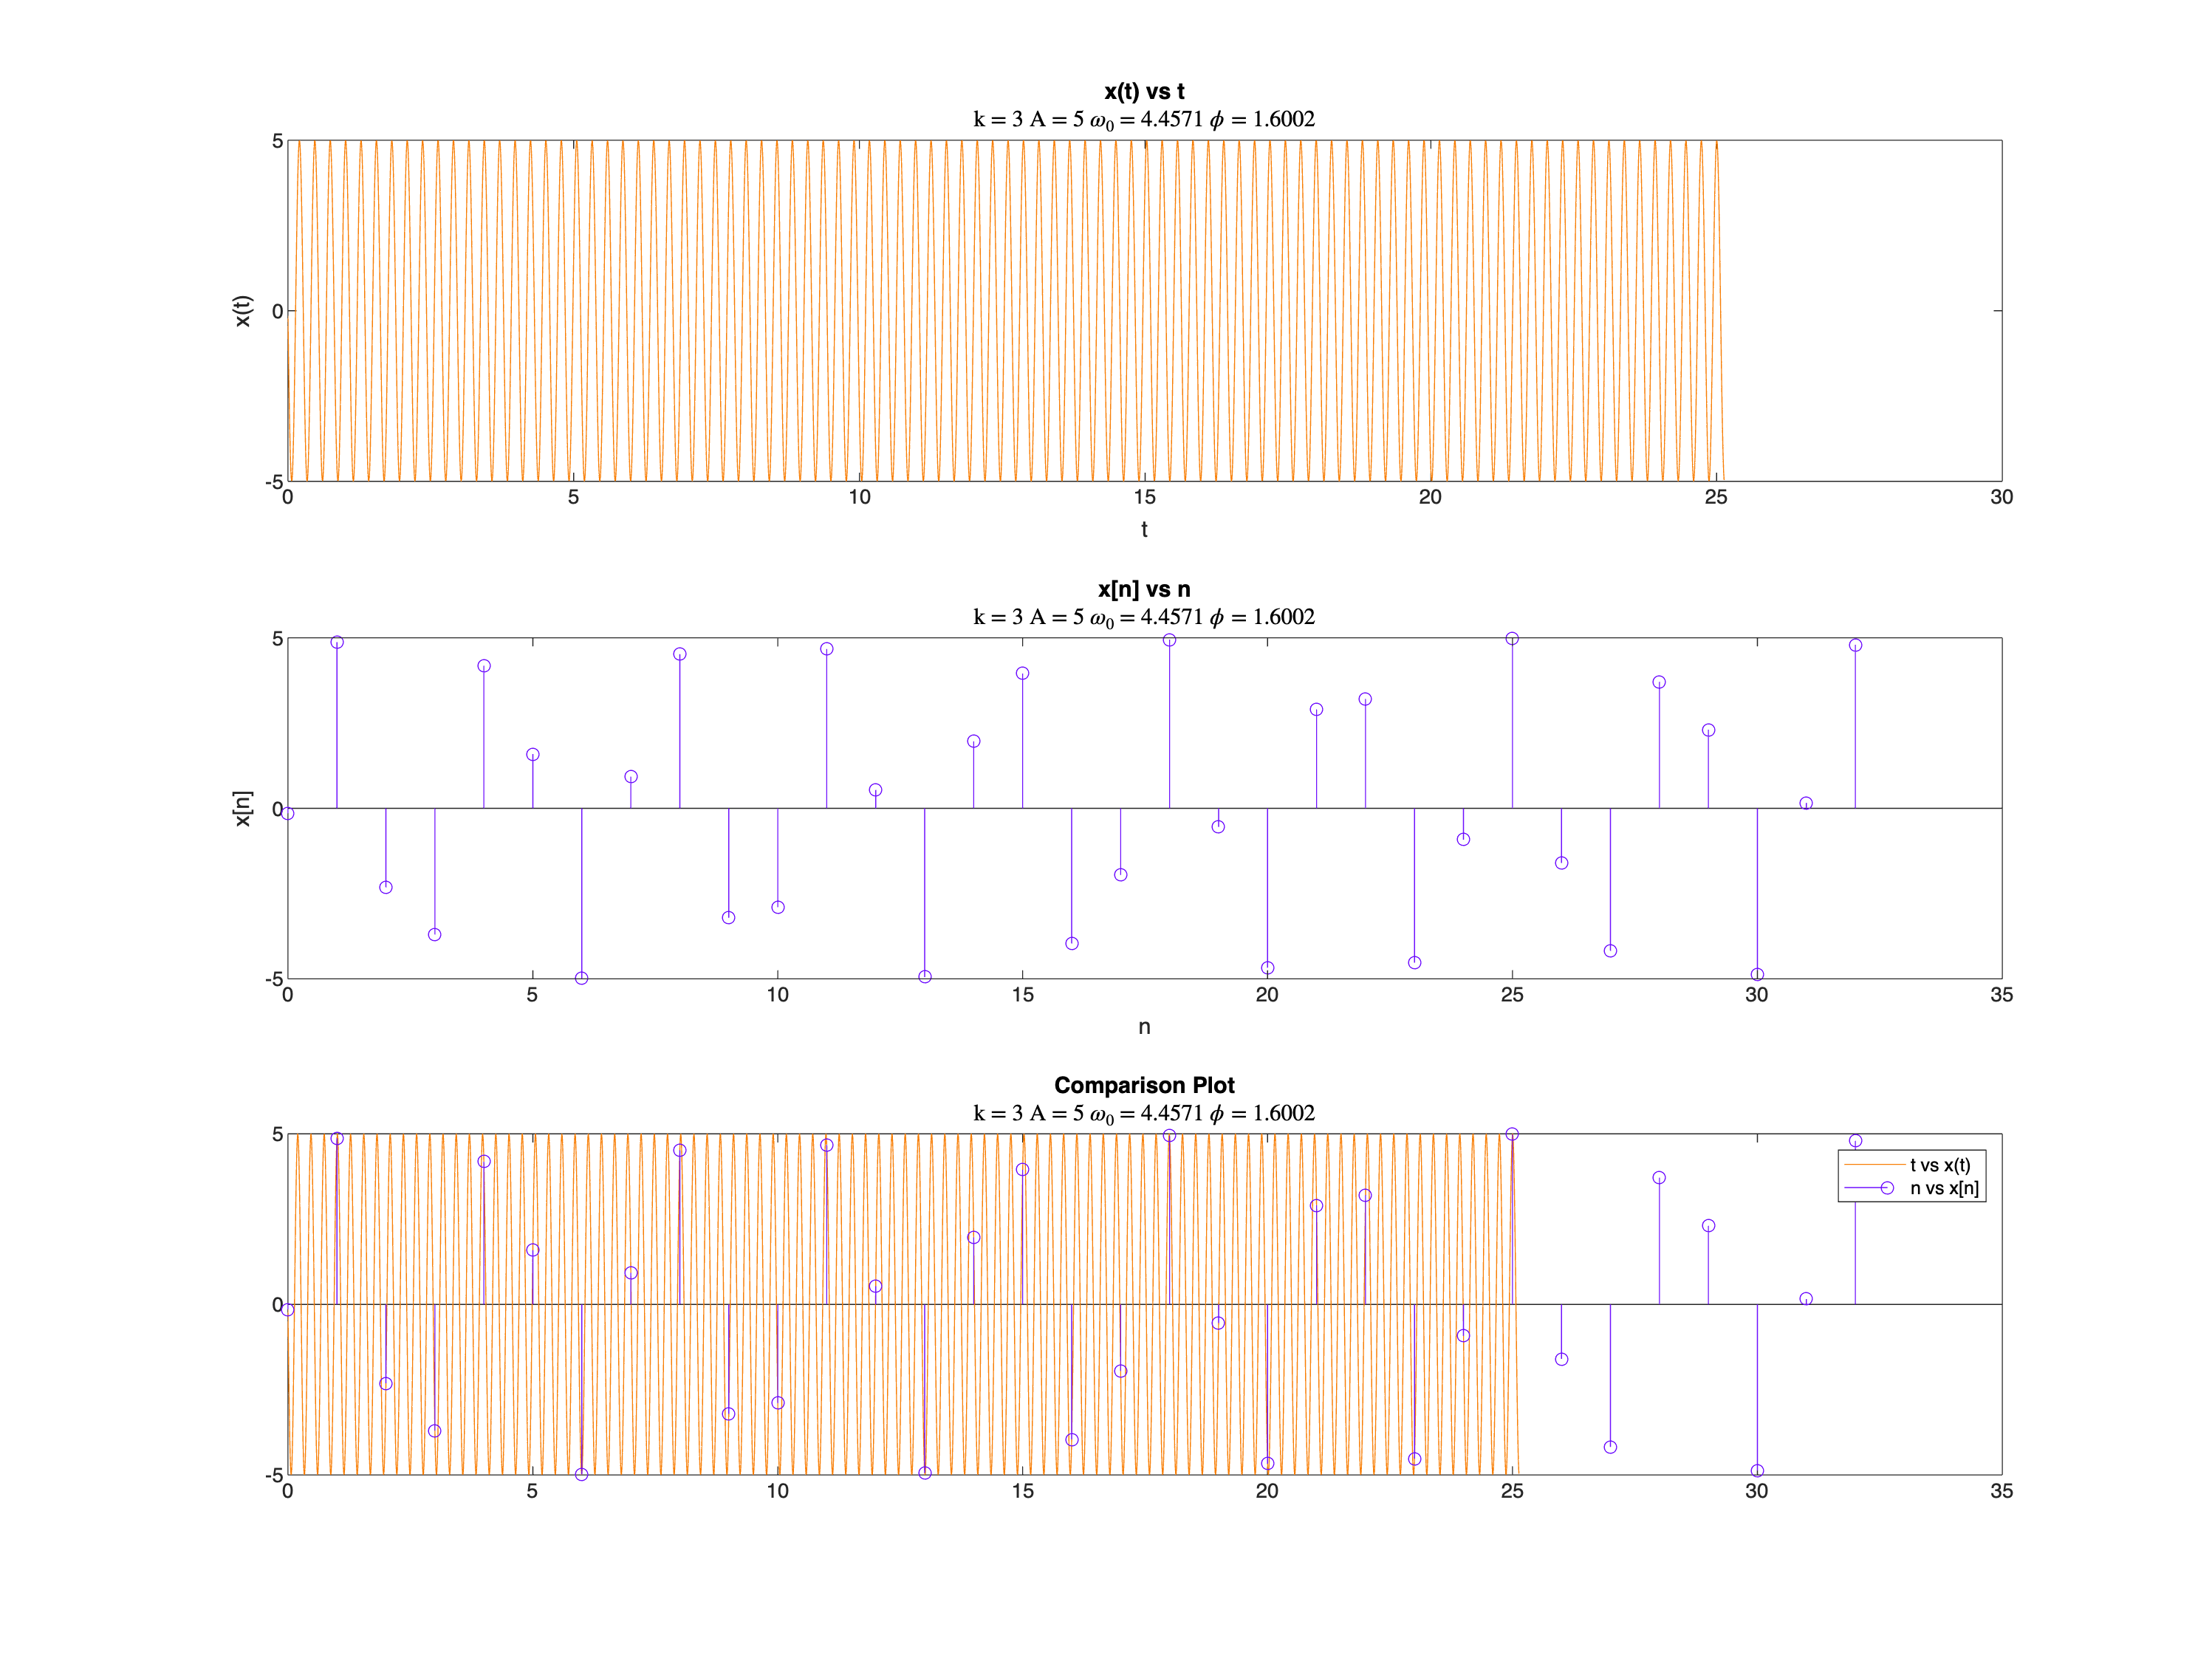

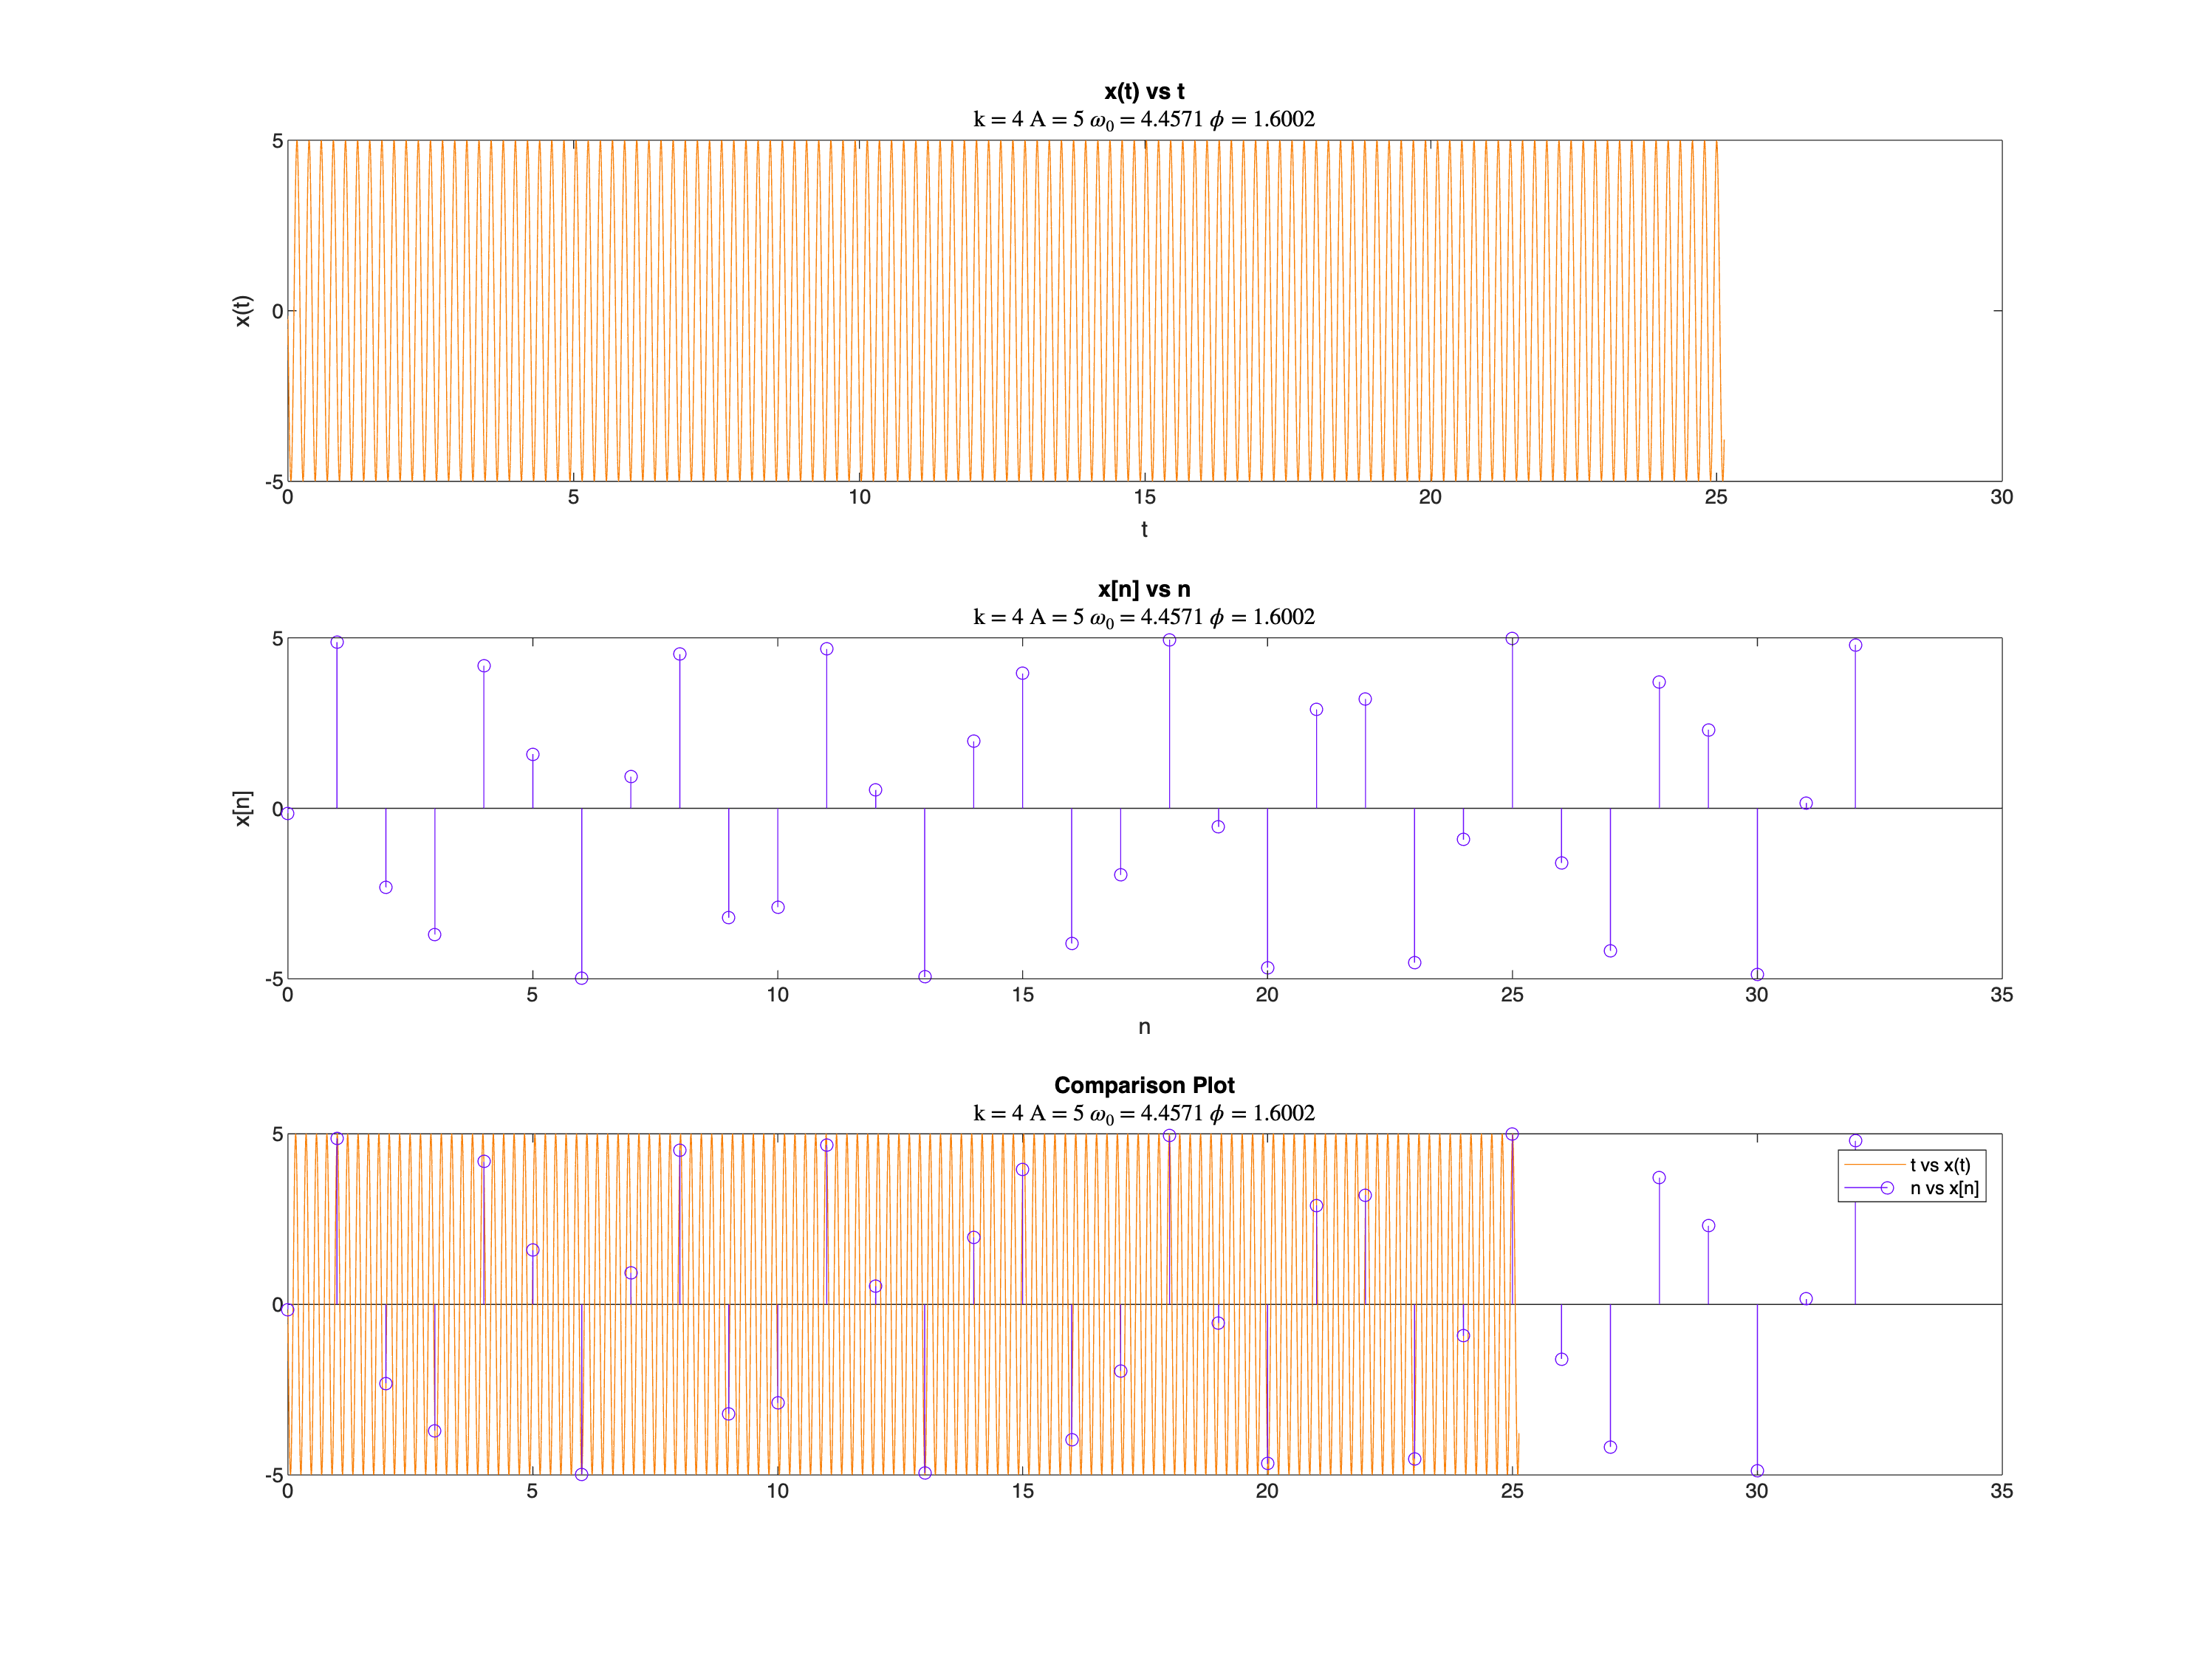

% Colour Constants
COLOUR_VIOLET = "#6E0FFE";
COLOUR_ORANGE = "#F87E05";

% Initialization of Required Variables
a = 5;
w0 = rand() * 2 * pi;
phi = -pi + rand() * 2 * pi;

% t for Continuous Time
t = 0:0.0001:8*pi;

% n for Discrete Time
n = 0:1:32;

% Given k = 0, 1, 2, 3, 4
for k = 0:4
    % Computing x(t)
    x_t = a * cos((w0 + (2 * pi * k)) * t + phi);
    
    % New Figure for Plotting
    figure;
    
    % 1st Subplot, x(t)
    subplot(3,1,1);
    plot(t, x_t, Color = COLOUR_ORANGE);
    xlabel('t'); 
    ylabel('x(t)');
    %xlim([-1, 8*pi + 1]);
    %ylim([-6, 6])
    title('x(t) vs t');
    subtitle(['k = ' num2str(k) ' A = ' num2str(a) ' $\omega_0$ = ' num2str(w0) ' $\phi$ = ' num2str(phi)], Interpreter = 'latex');
    
    % Increasing Subplot size by 3 (Subplot Scales down by 3)
    figProps = gcf;
    figProps.Position(3:4) = figProps.Position(3:4) * 3;
    
    % 2nd Subplot, x[n]
    x_n = a * cos((w0 + (2 * pi * k)) * n + phi);
    subplot(3,1,2);
    stem(n, x_n, Color = COLOUR_VIOLET);
    xlabel('n'); 
    ylabel('x[n]');
    %ylim([-6,6])
    %xlim([-1,33]);
    title('x[n] vs n');
    subtitle(['k = ' num2str(k) ' A = ' num2str(a) ' $\omega_0$ = ' num2str(w0) ' $\phi$ = ' num2str(phi)], Interpreter = 'latex');
    
    % 3rd Subplot, x(t) & x[n]
    % First Plot x(t), Hold Figure and Plot x[n] (Sketches in Same Plot)
    subplot(3,1,3);
    plot(t, x_t, Color = COLOUR_ORANGE);
    hold on;
    stem(n, x_n, Color = COLOUR_VIOLET);
    title("Comparison Plot");
    legend({'t vs x(t)' 'n vs x[n]'})
    subtitle(['k = ' num2str(k) ' A = ' num2str(a) ' $\omega_0$ = ' num2str(w0) ' $\phi$ = ' num2str(phi)], Interpreter = 'latex');
    
end

### **Observation:**

For continuous time plots, as k increases, angular frequency increases which in turn makes the graph look compressed like a spring. 

For discrete time plots, frequencies as integral multiple of $$2\pi$
$ added to $$\omega_0$$ gives the same discrete time plot as for the original $$\omega_0$
$.

**II. Frequencies within **$$[0, 2\pi]$$

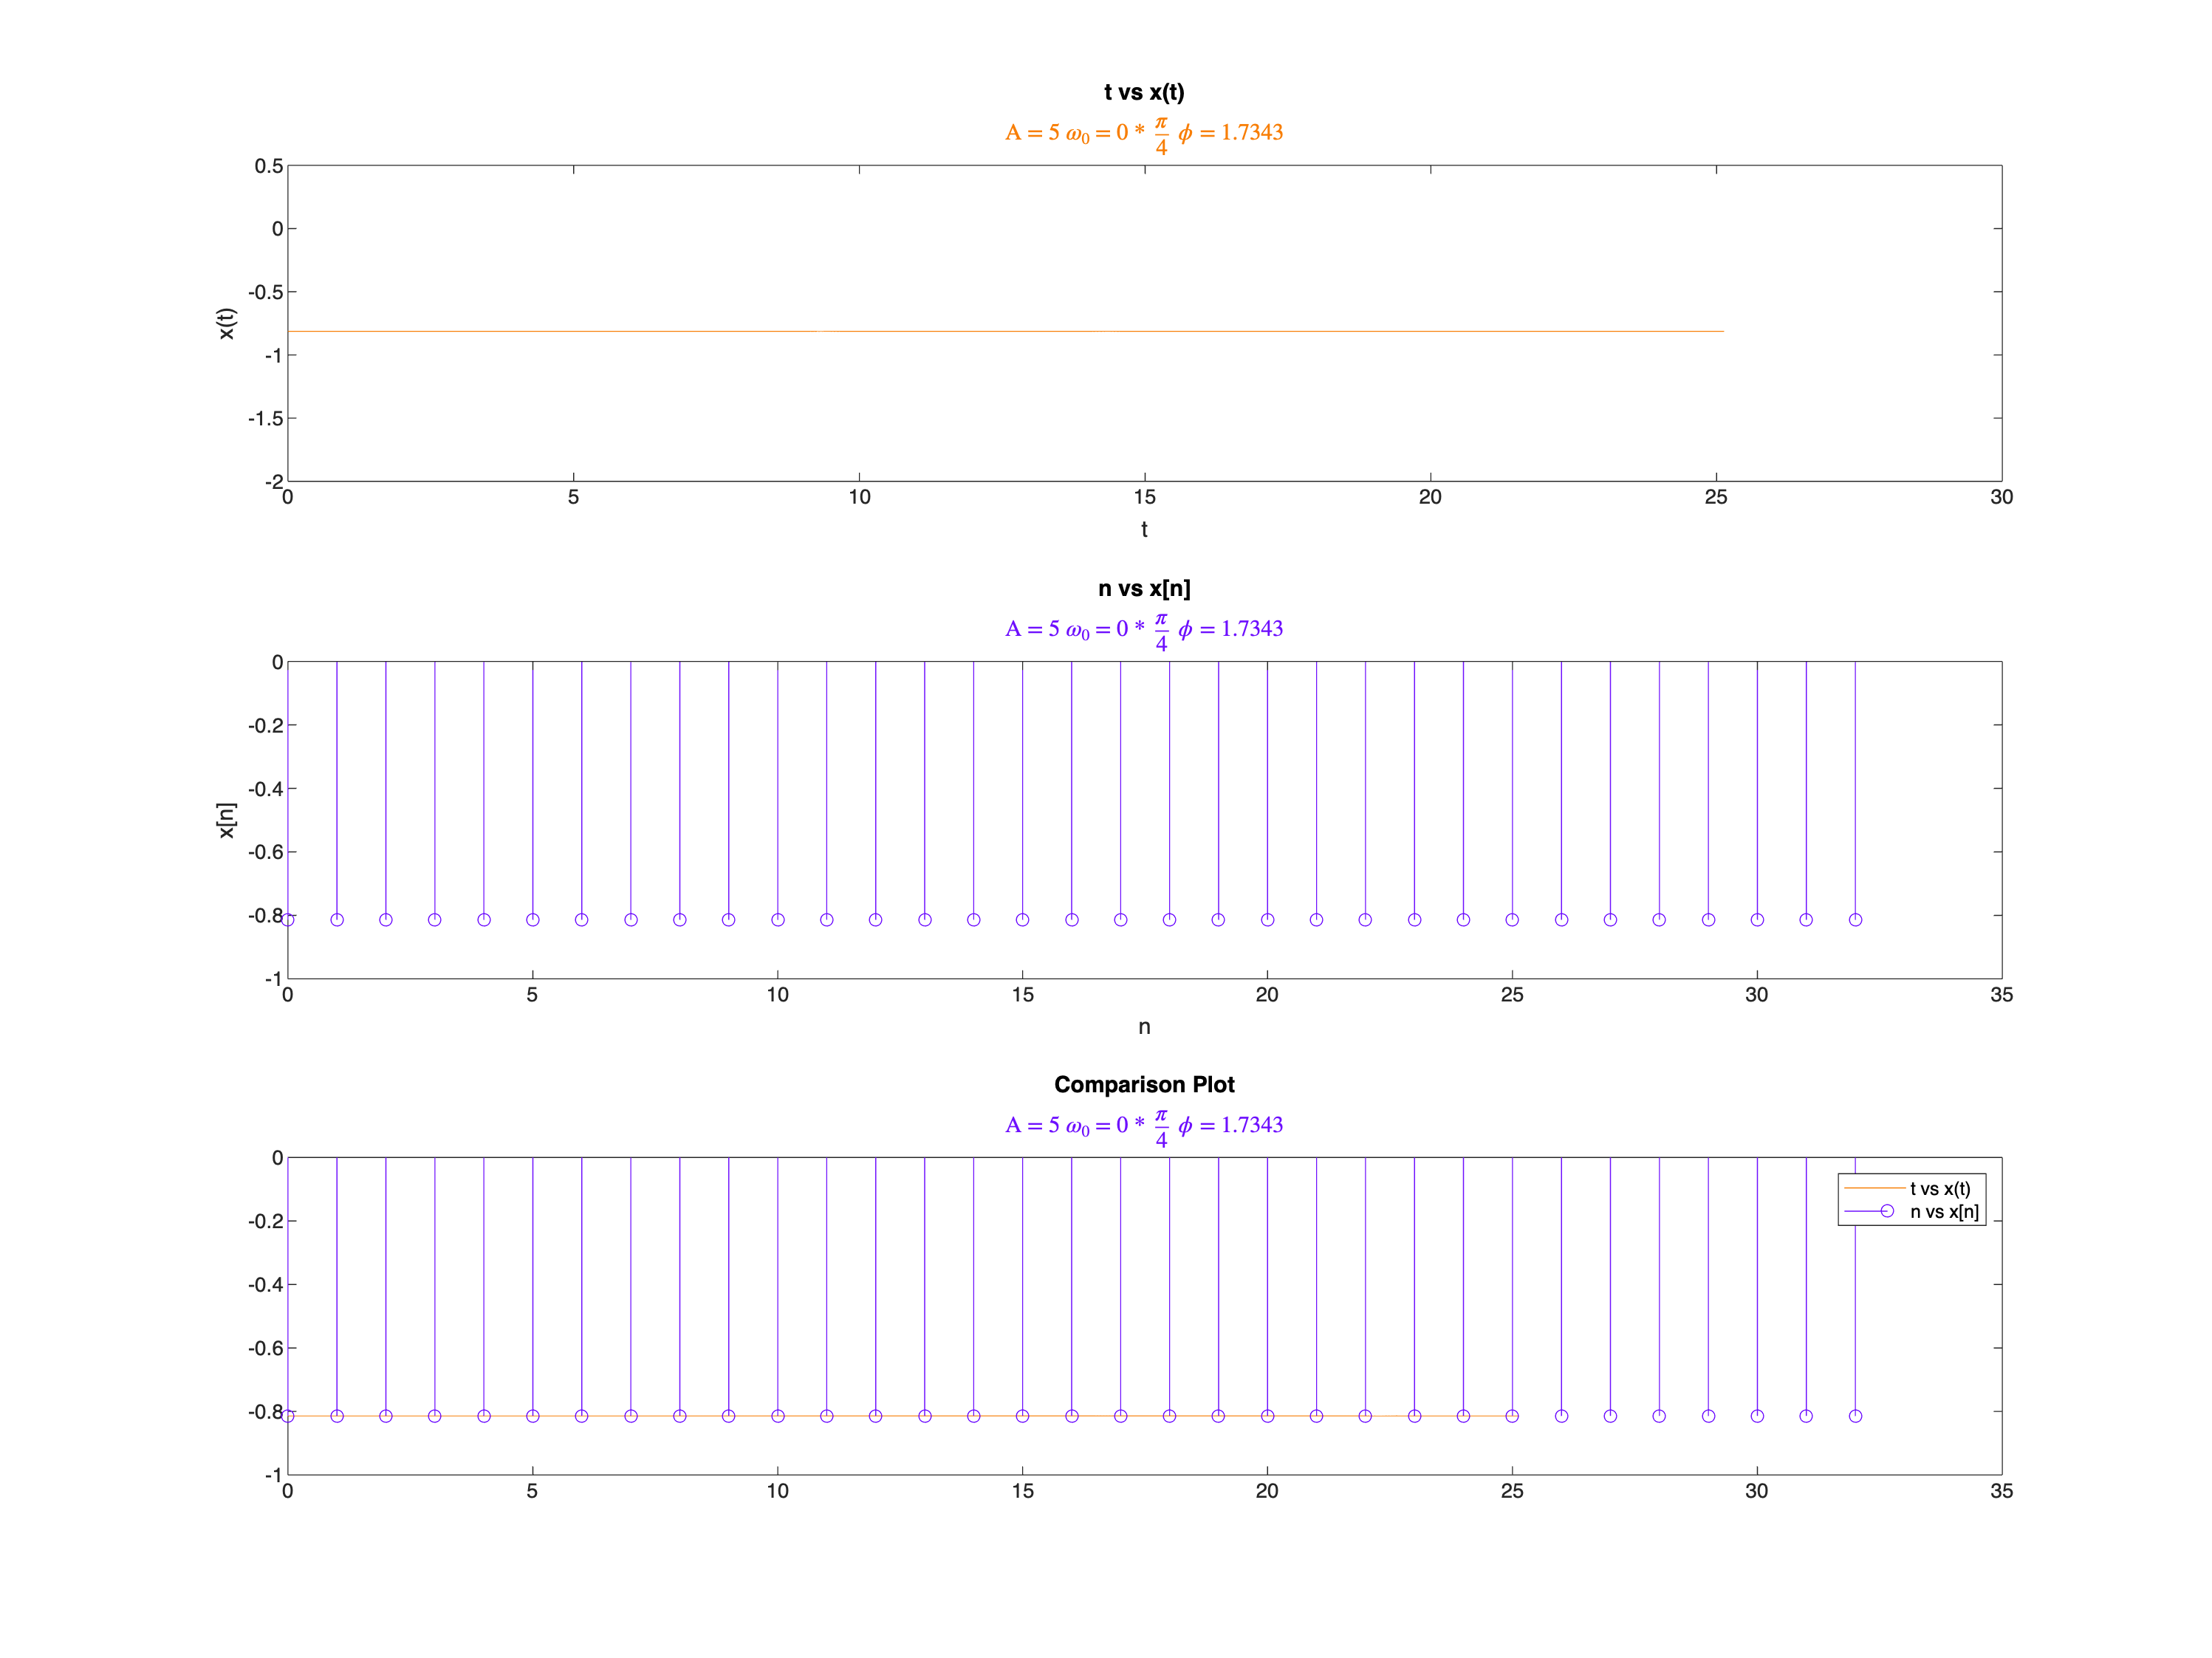

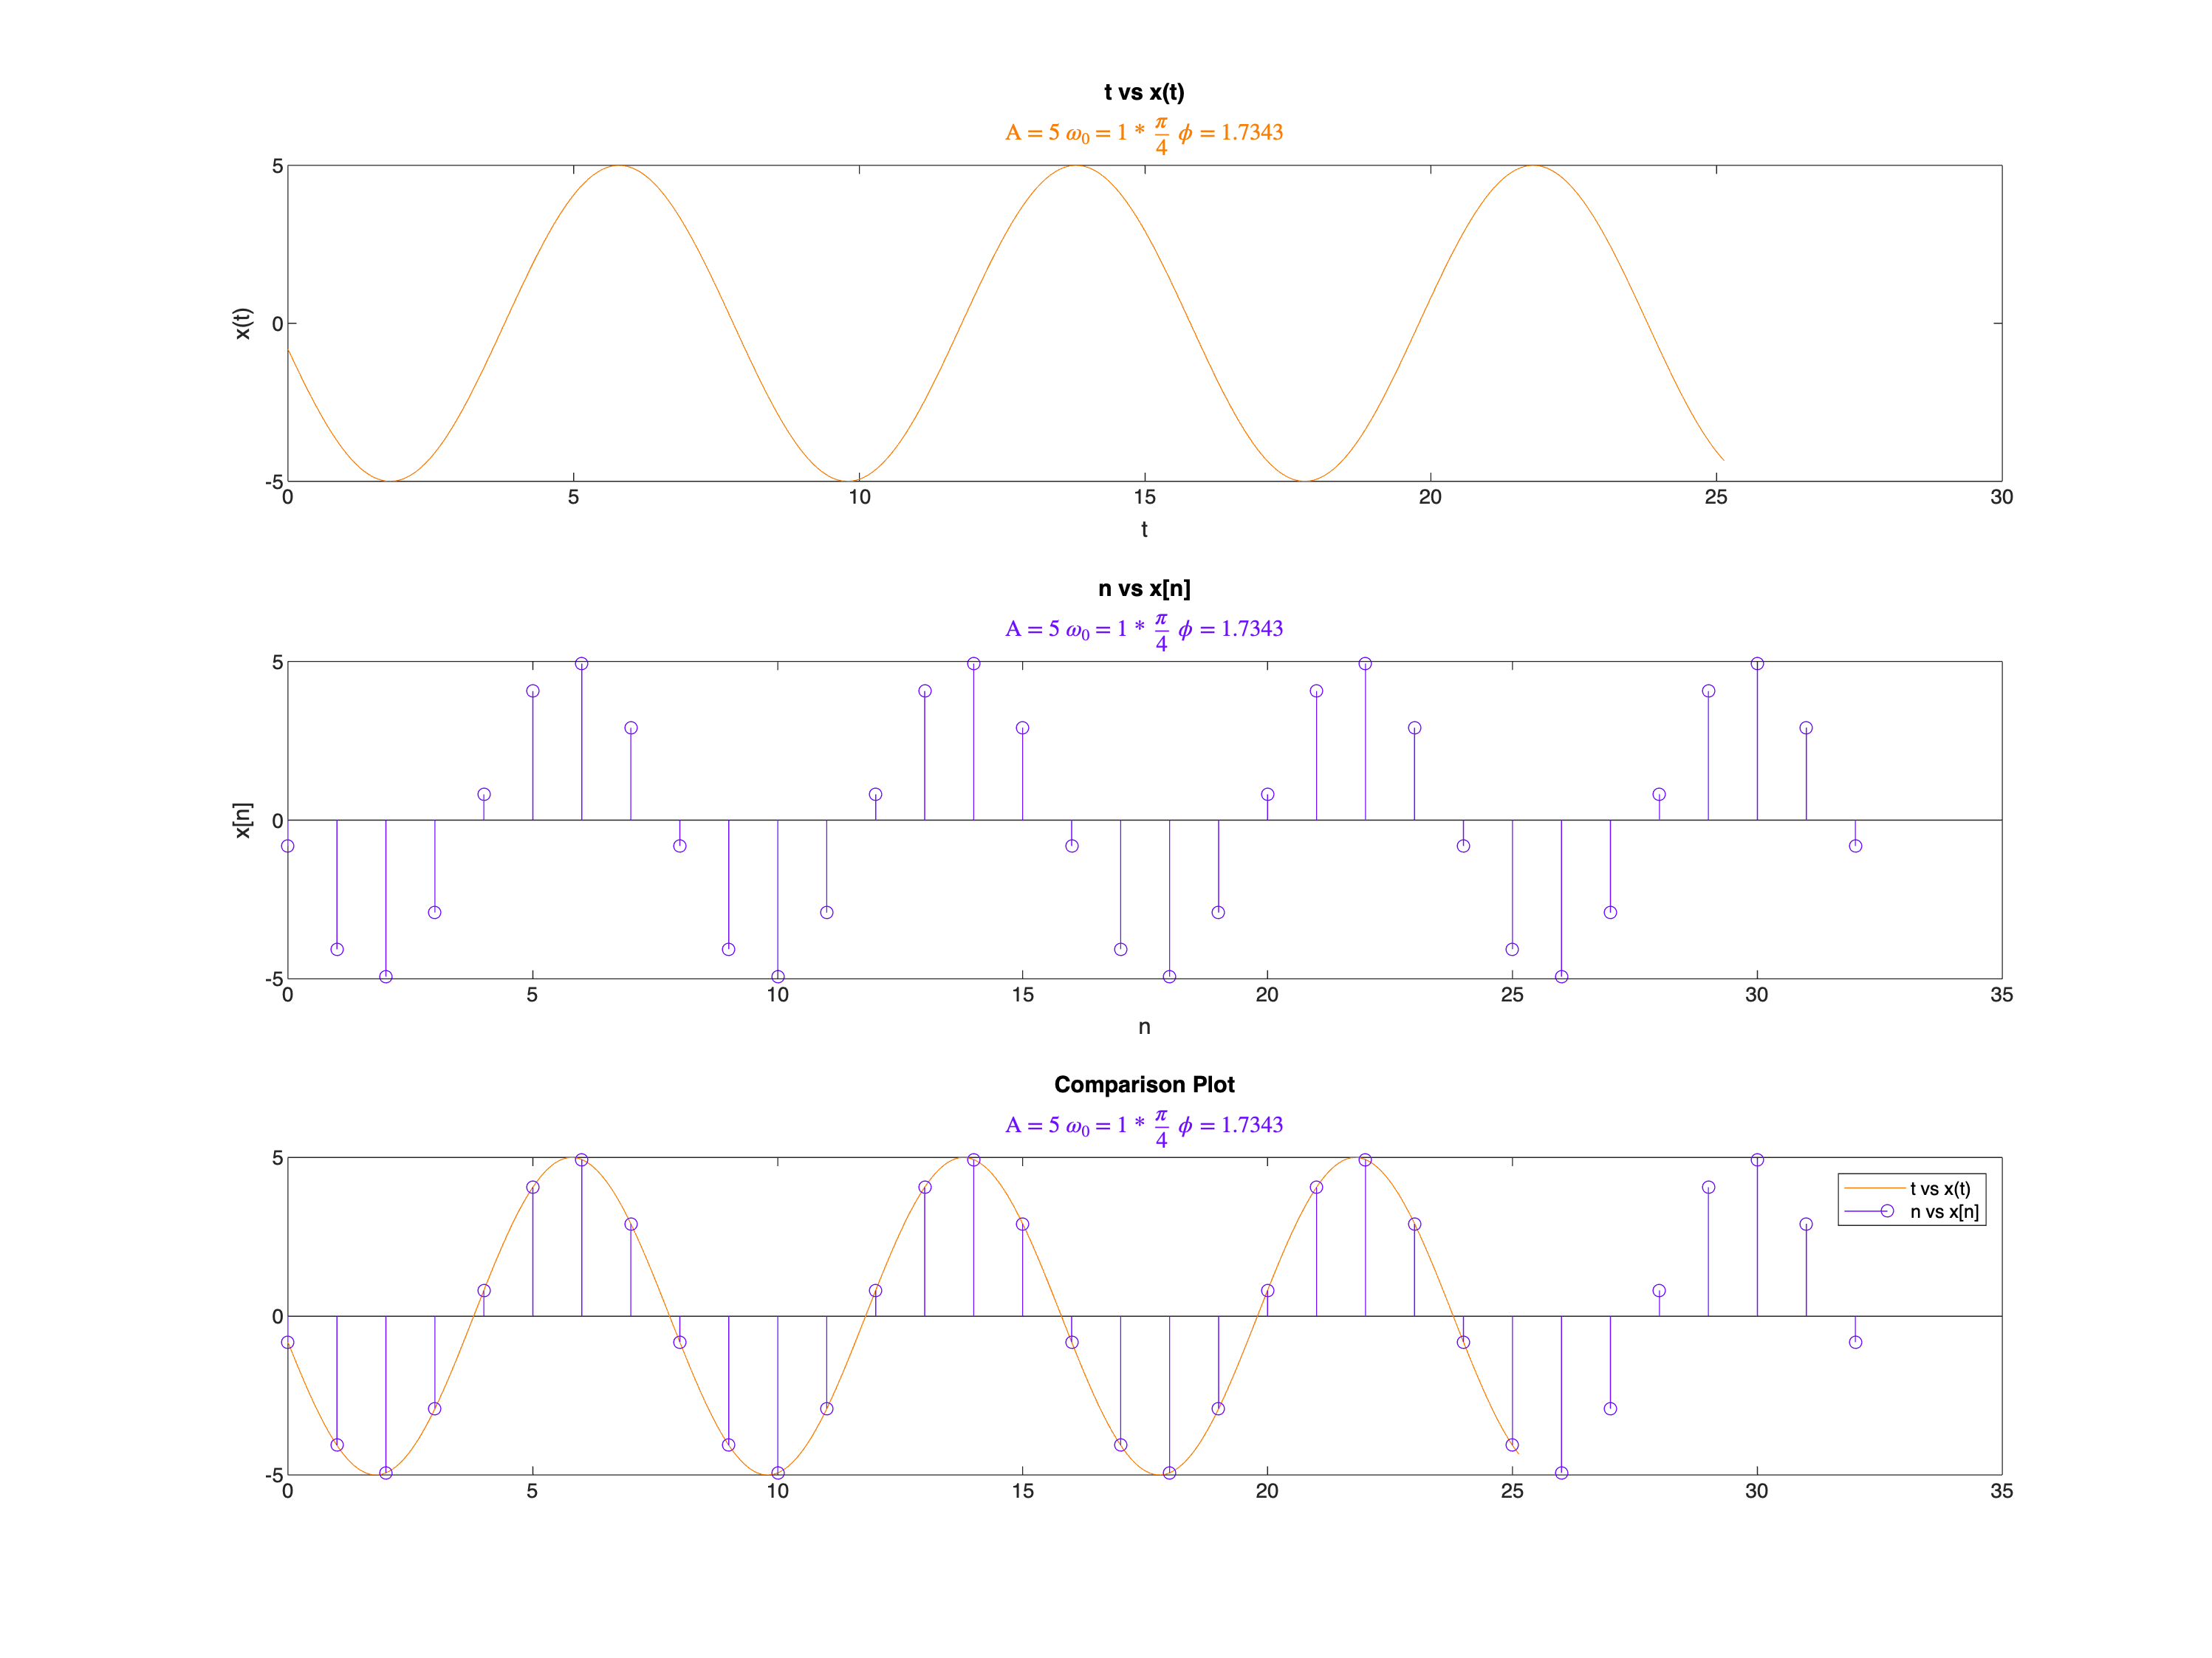

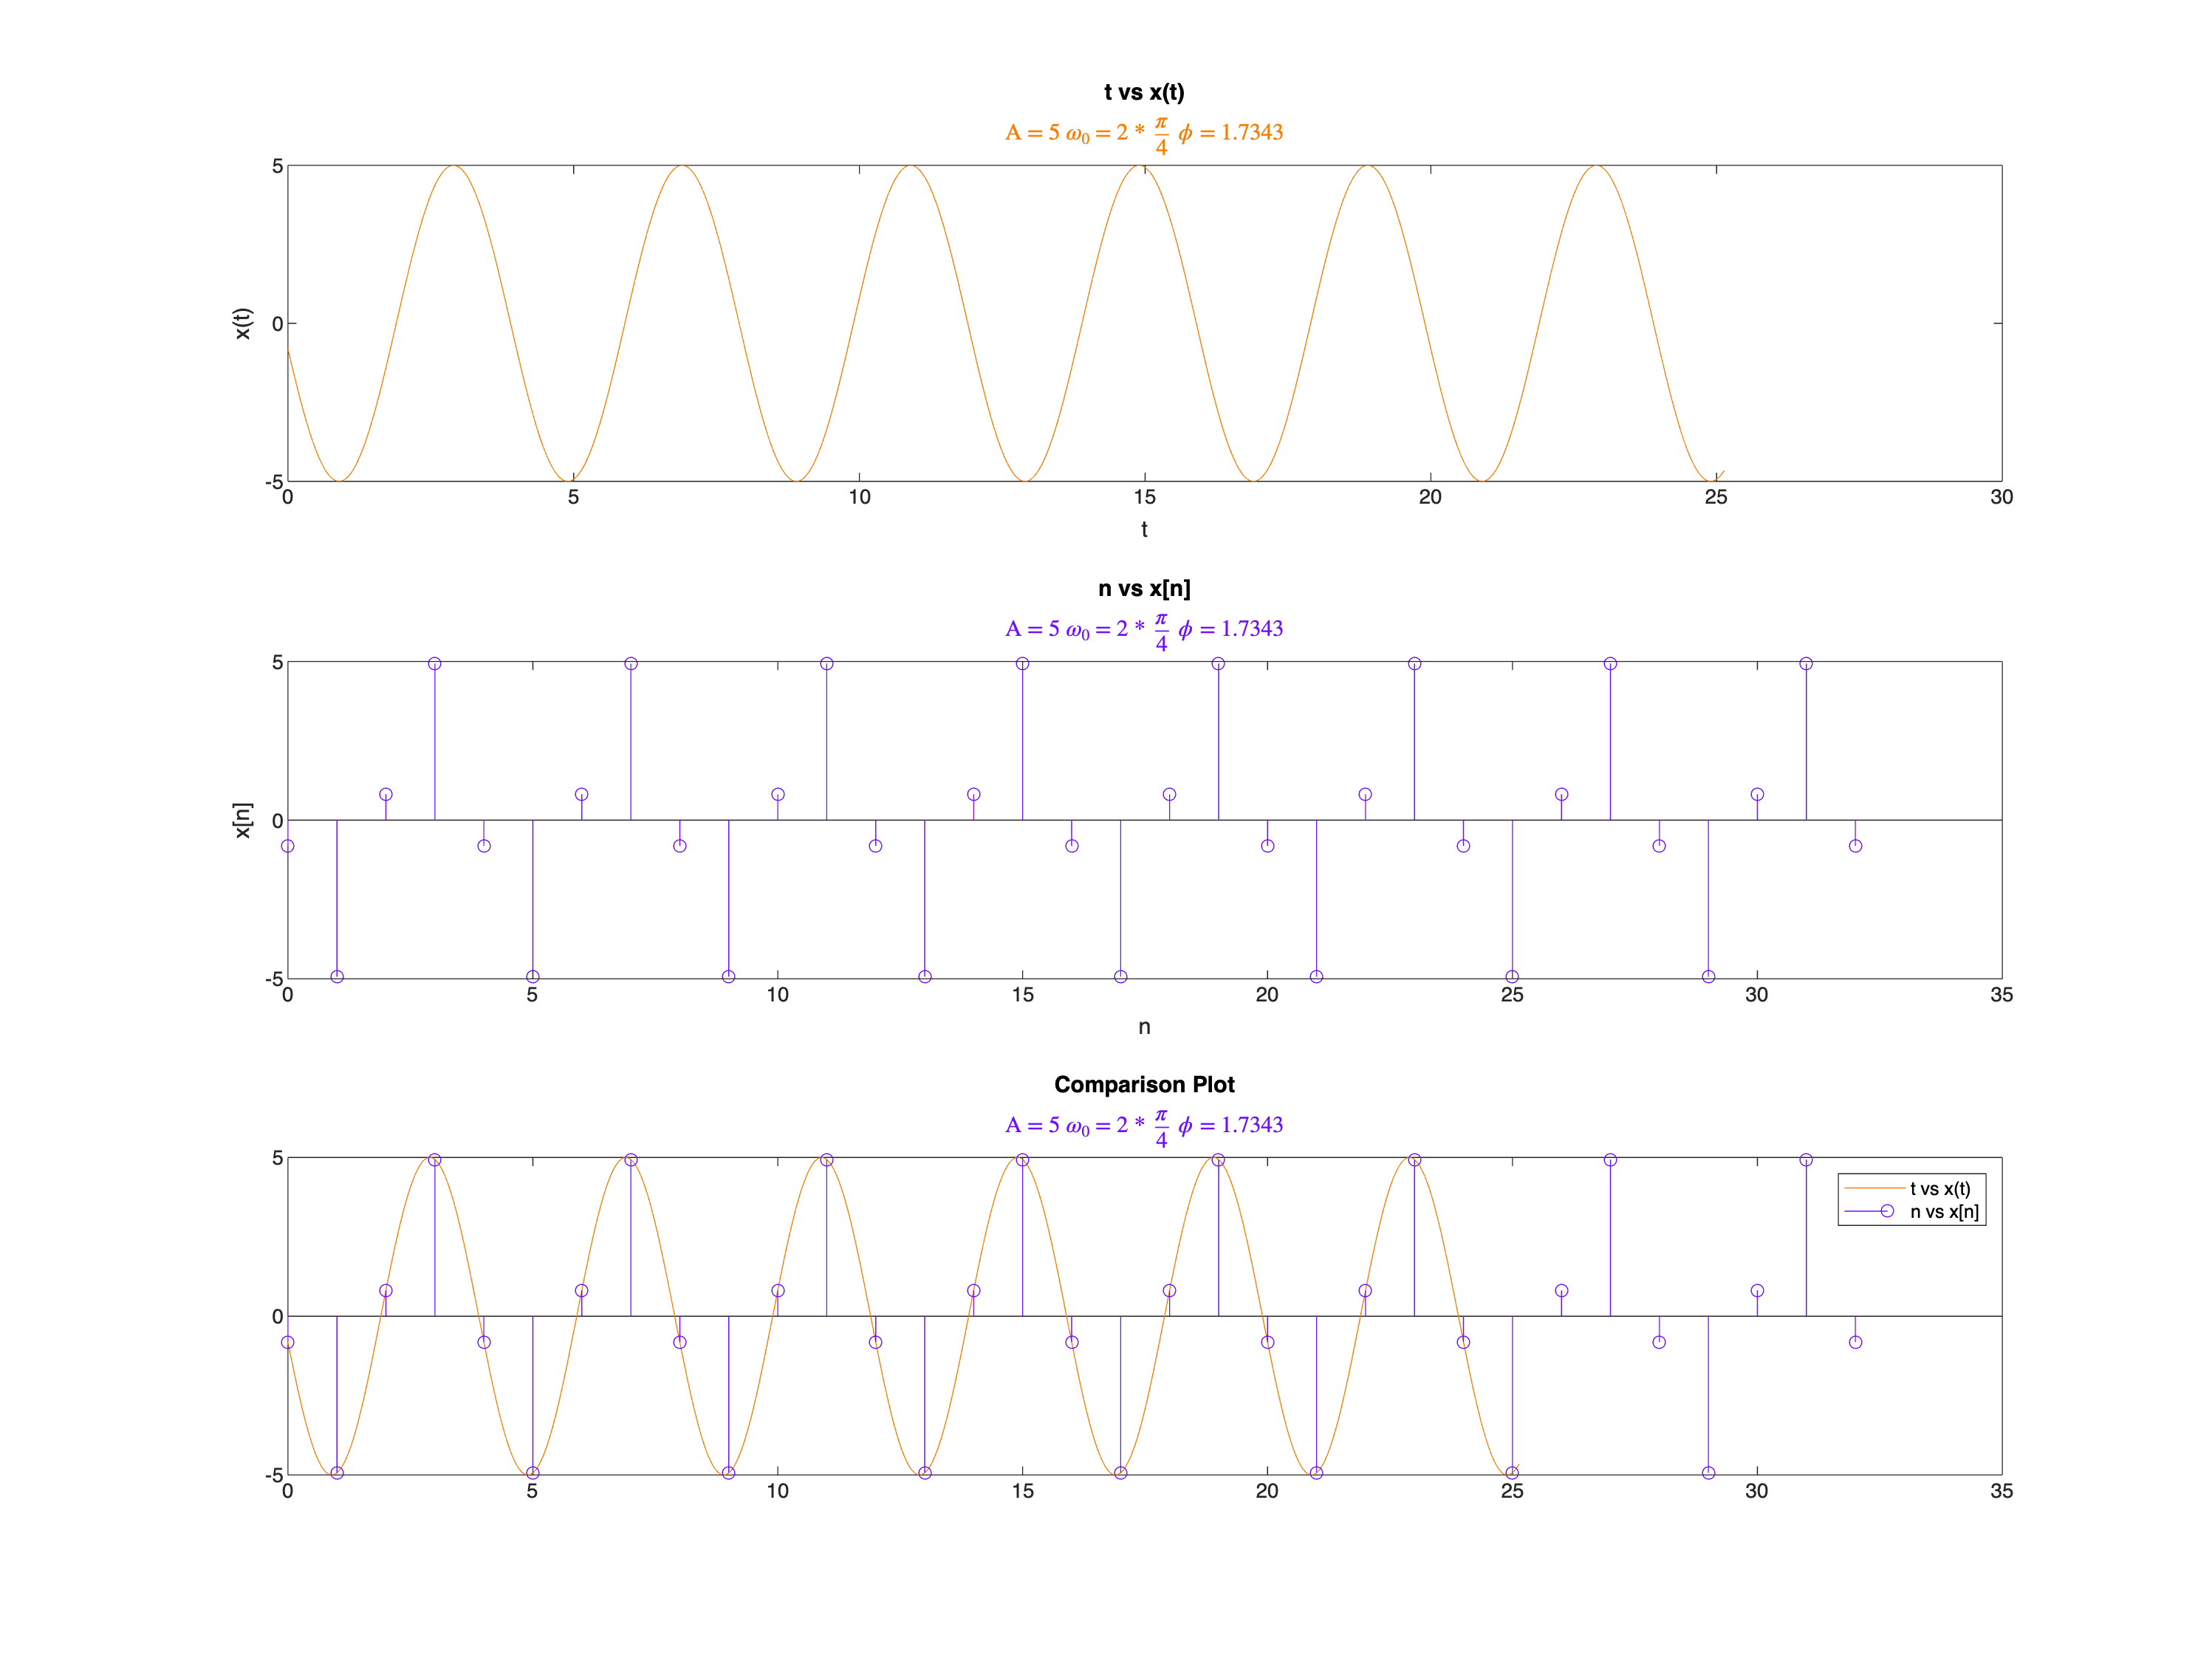

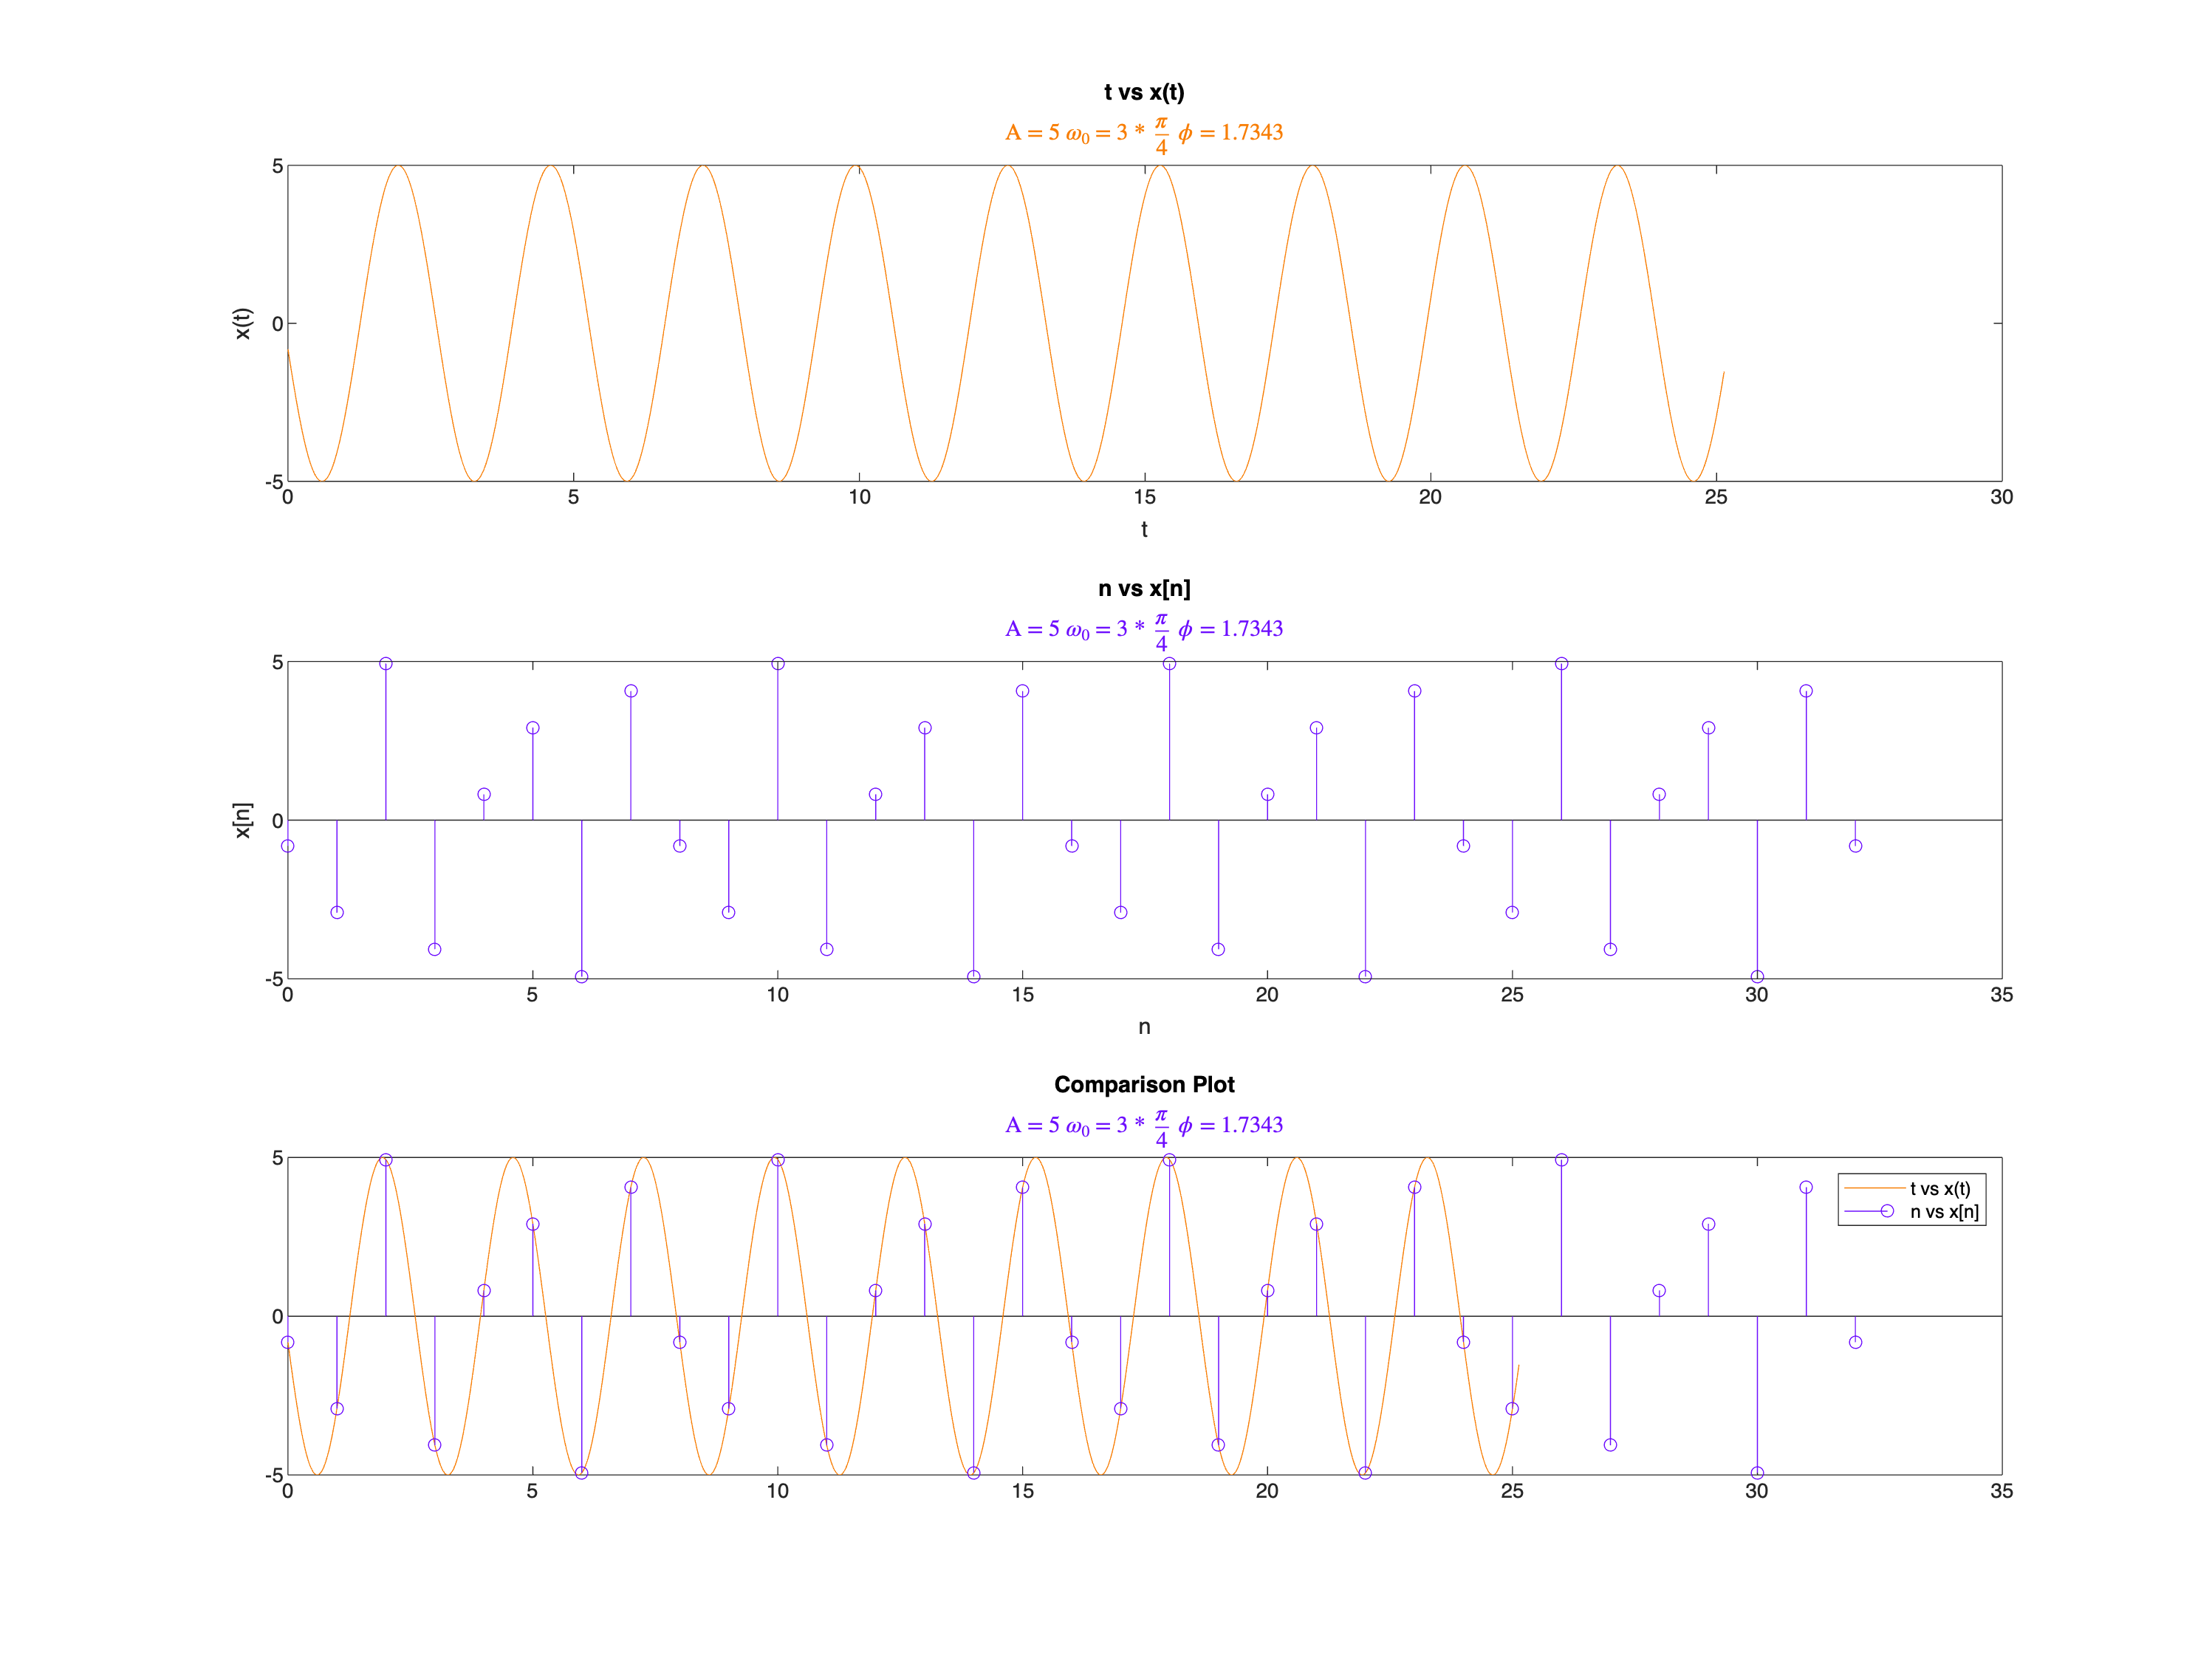

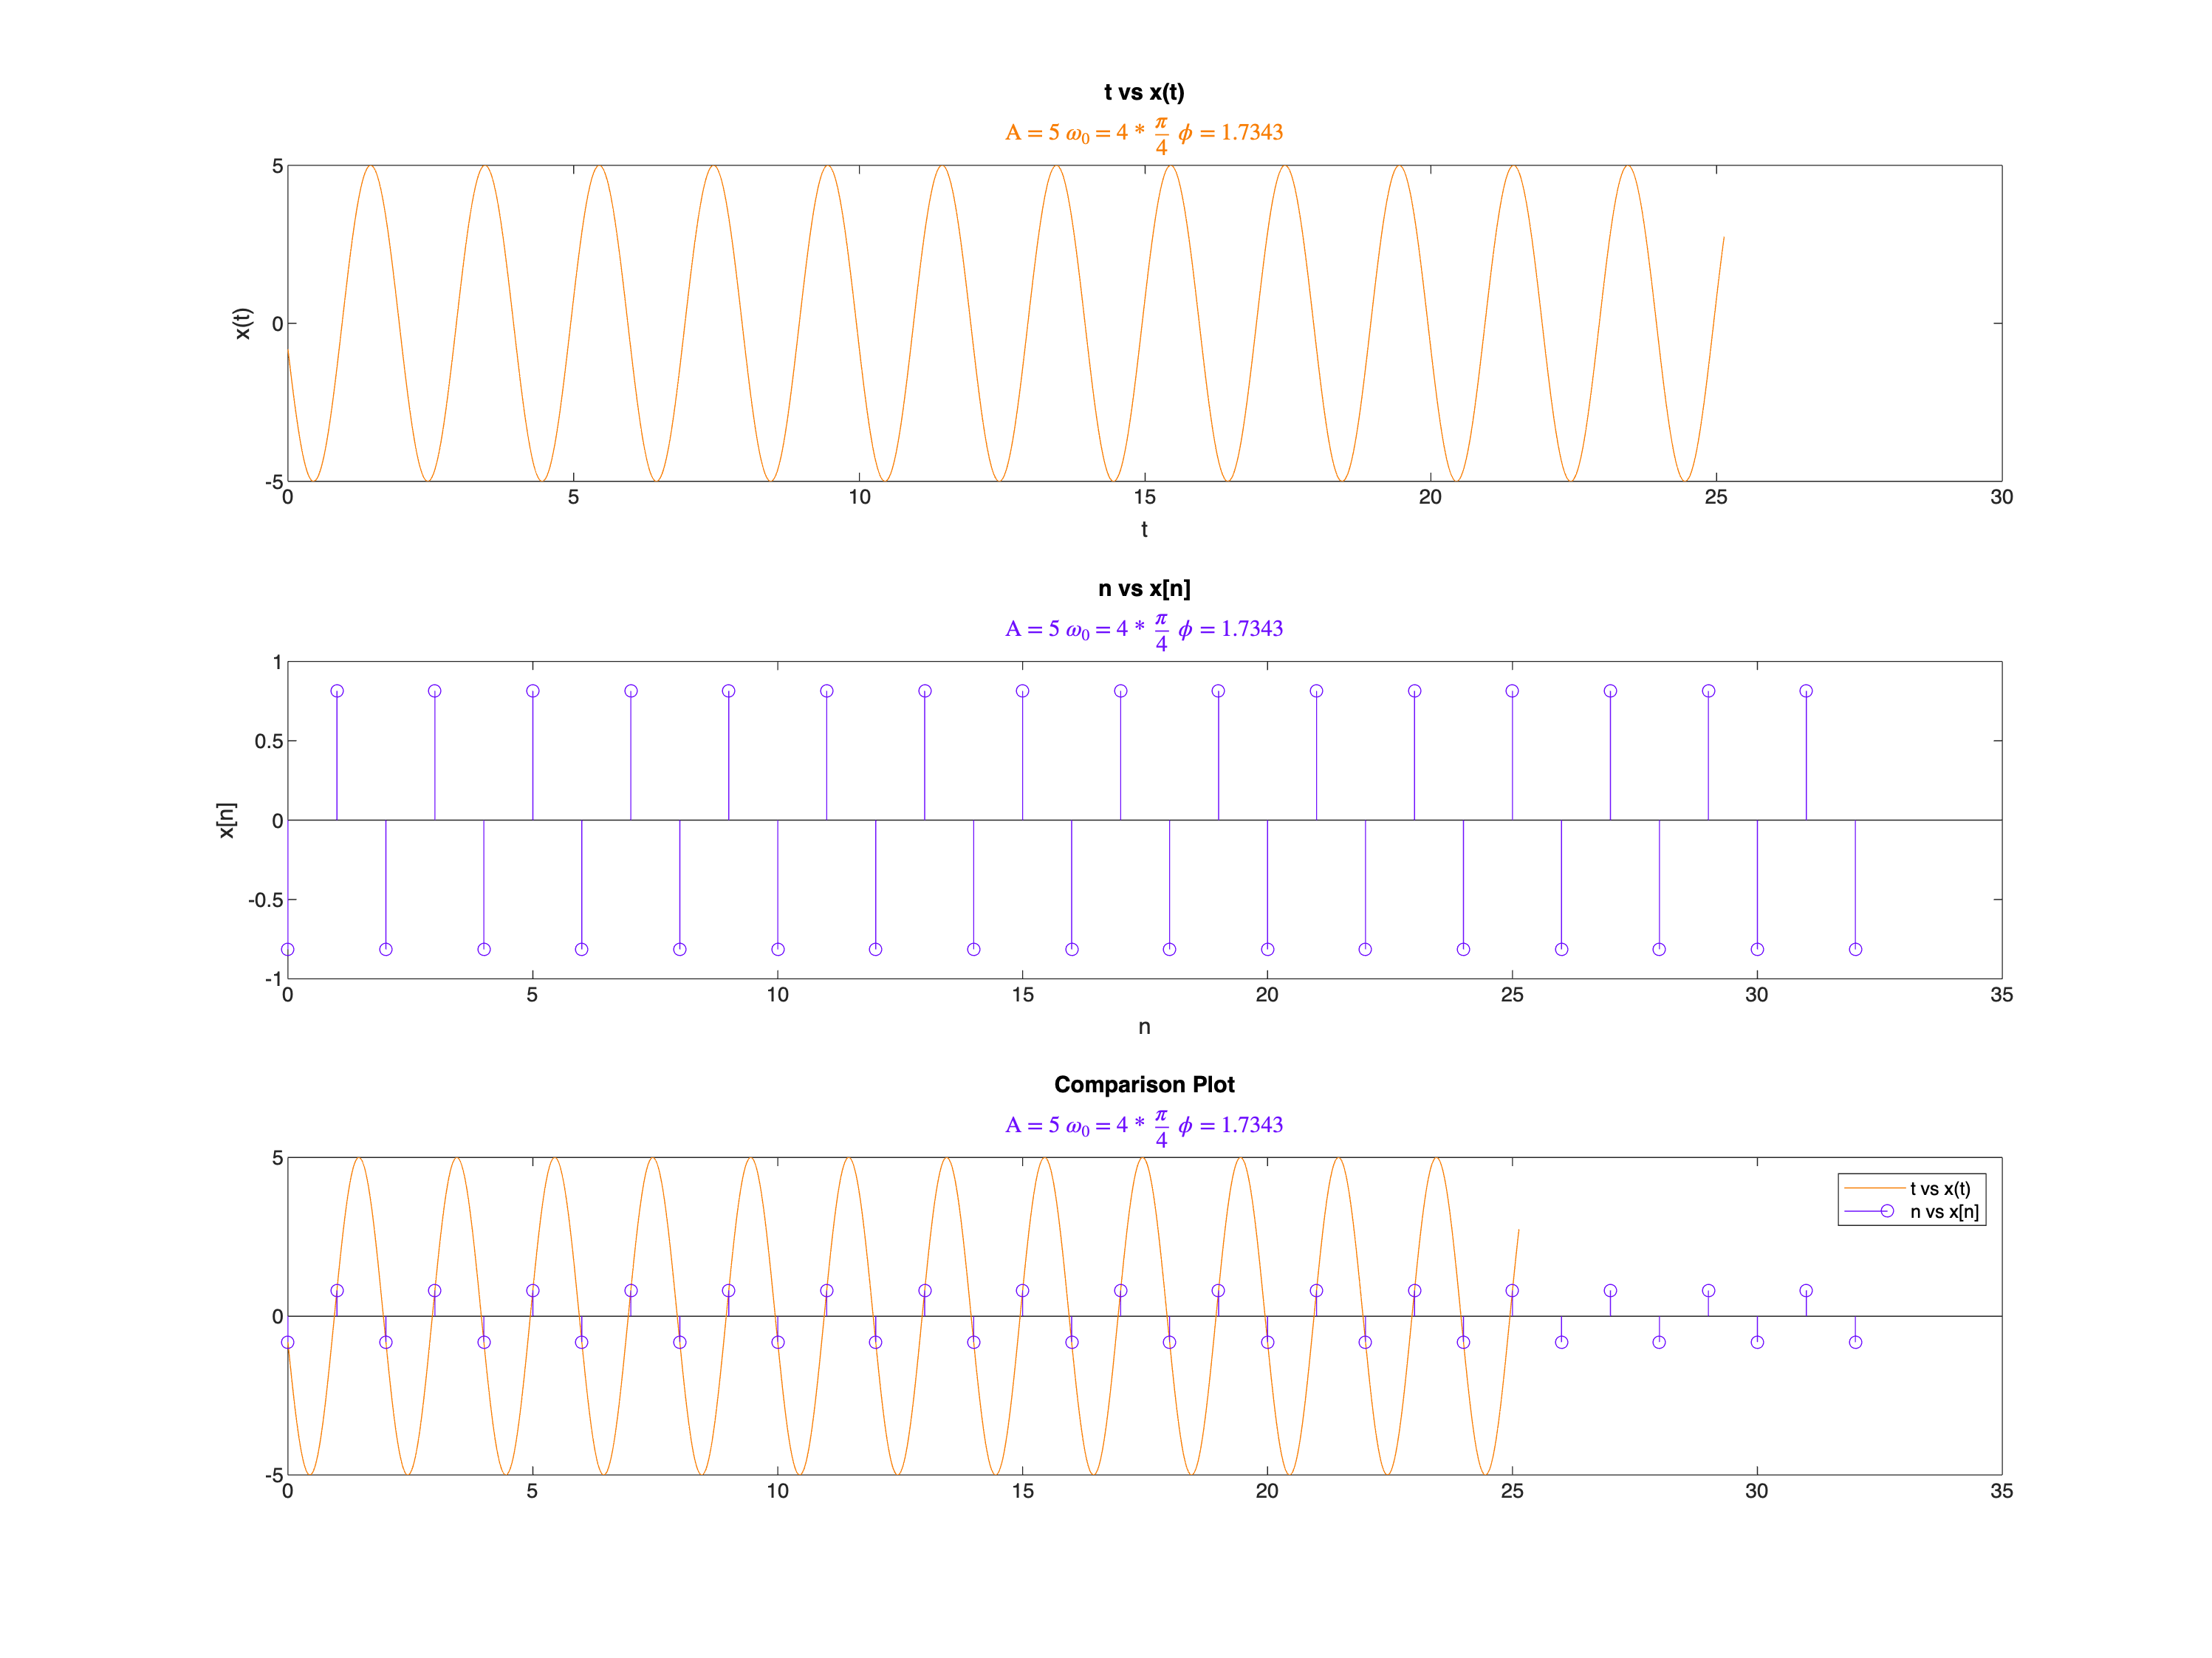

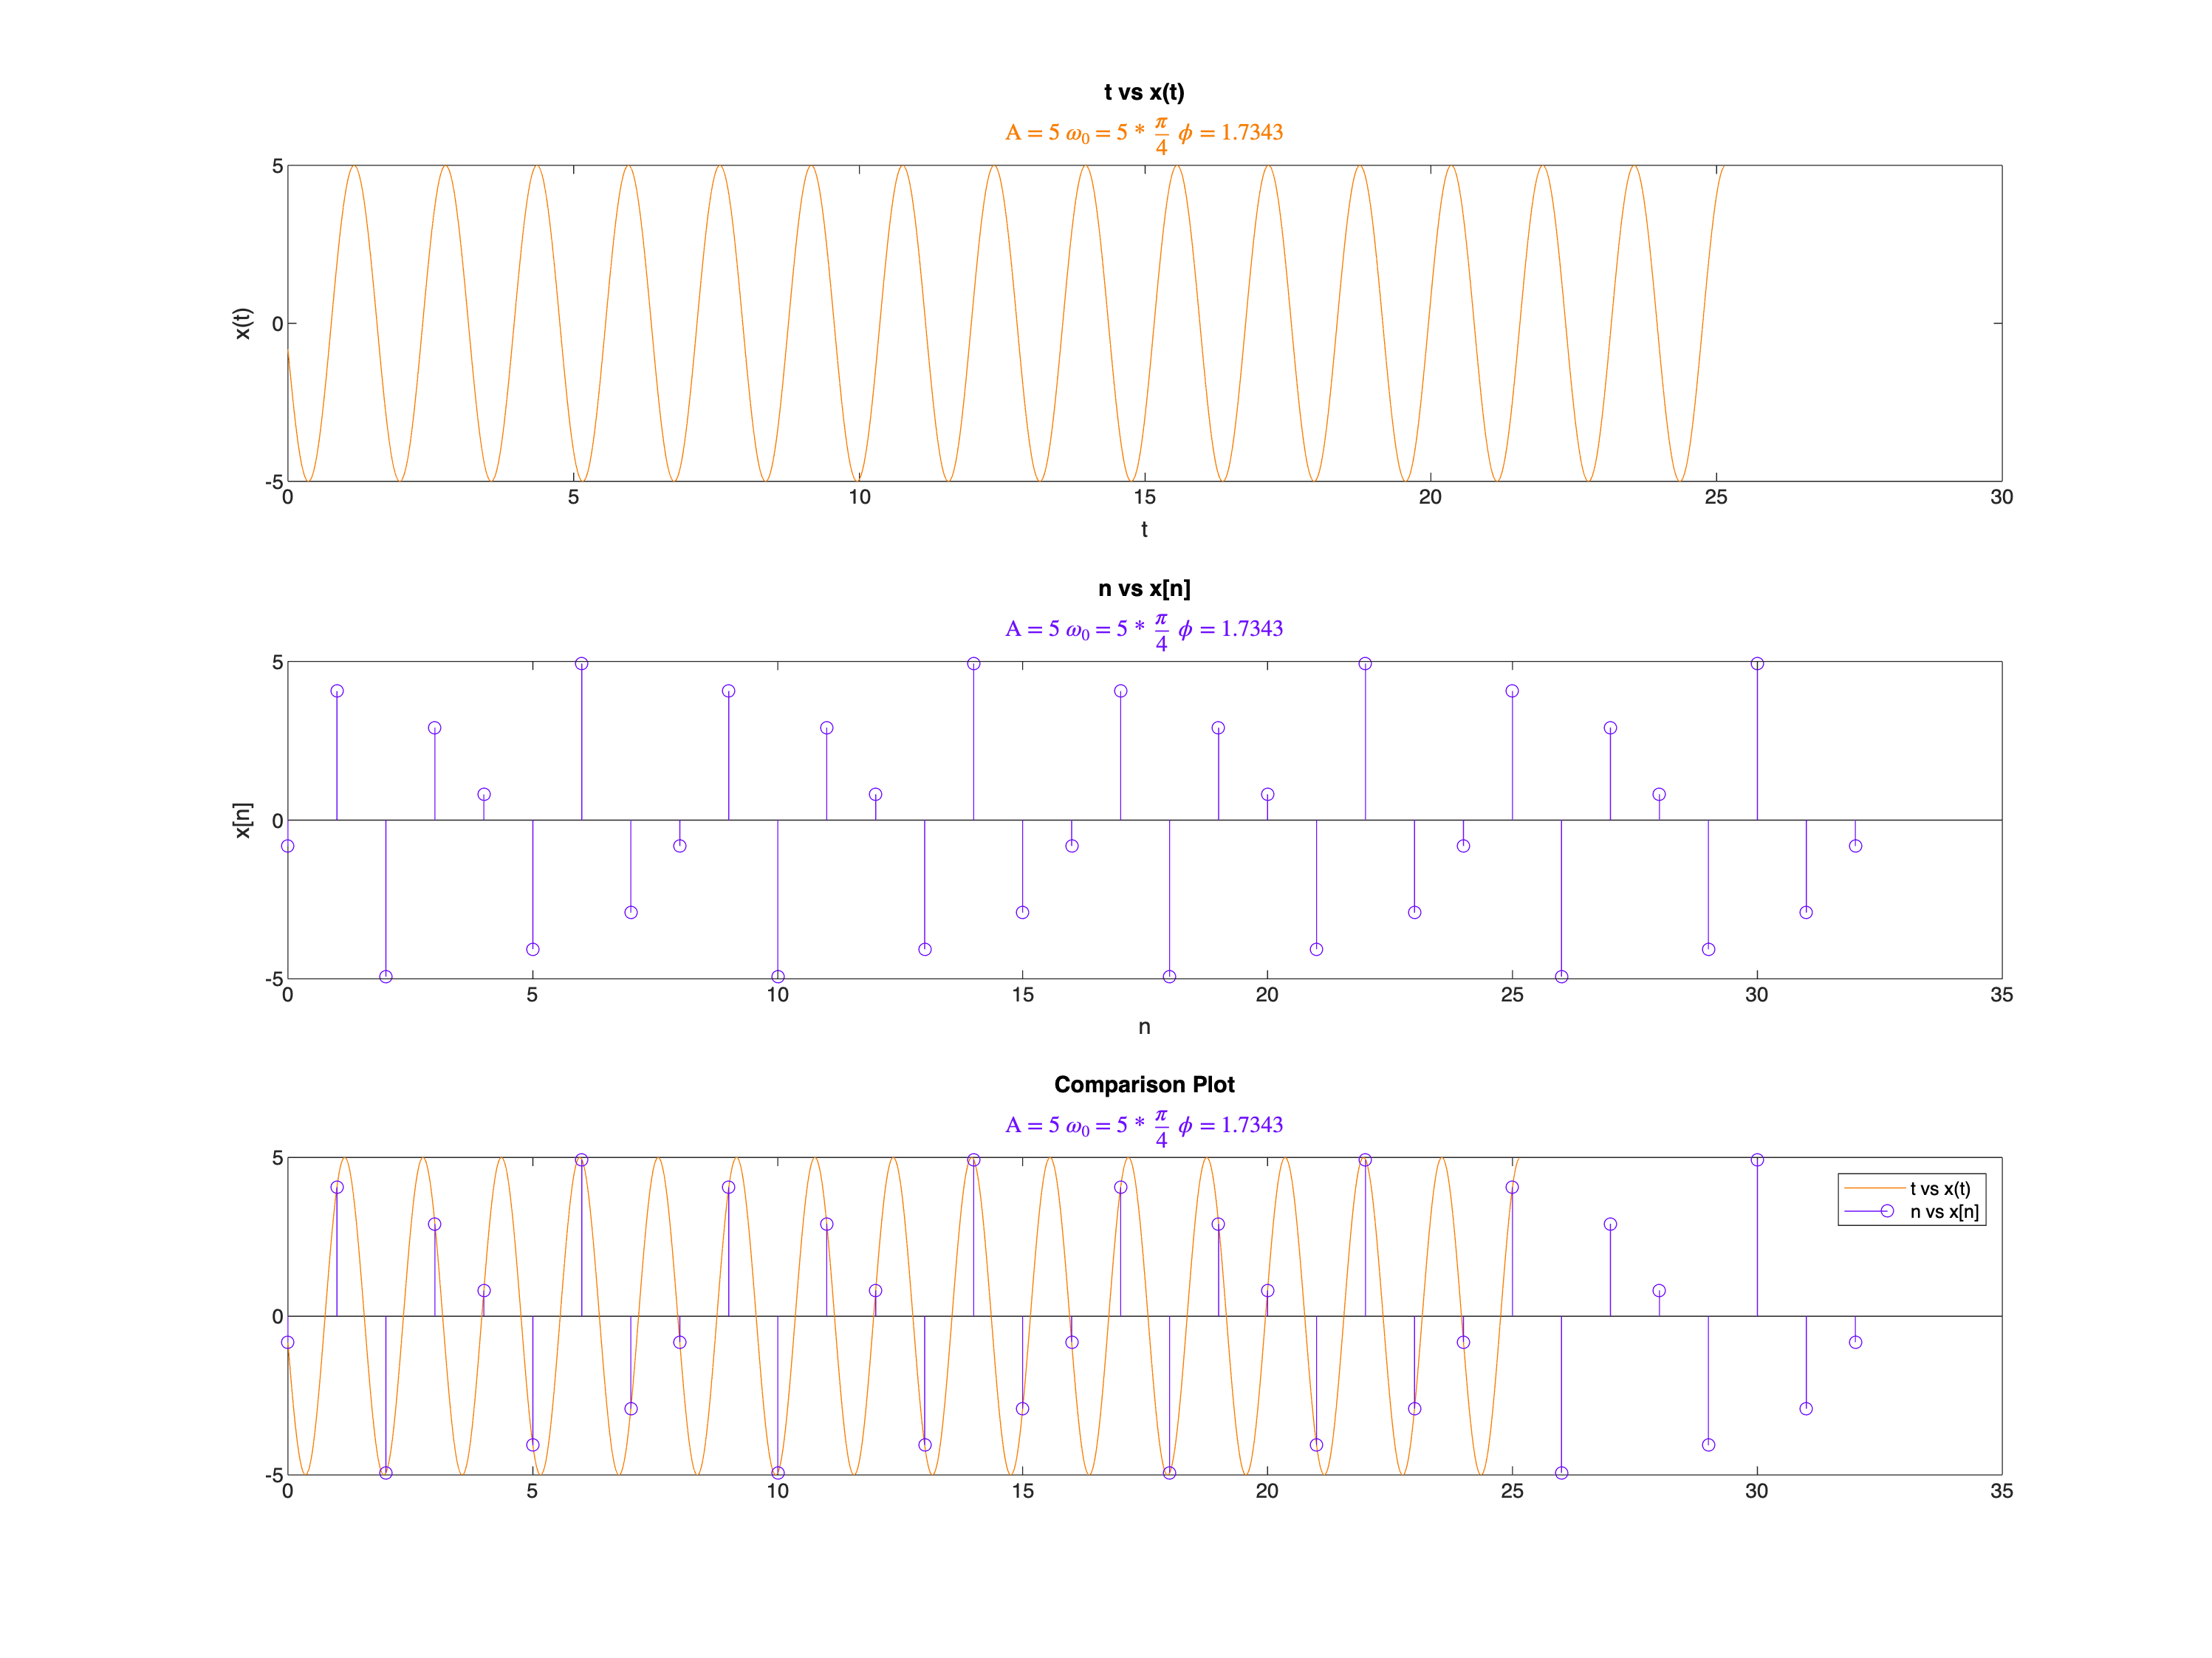

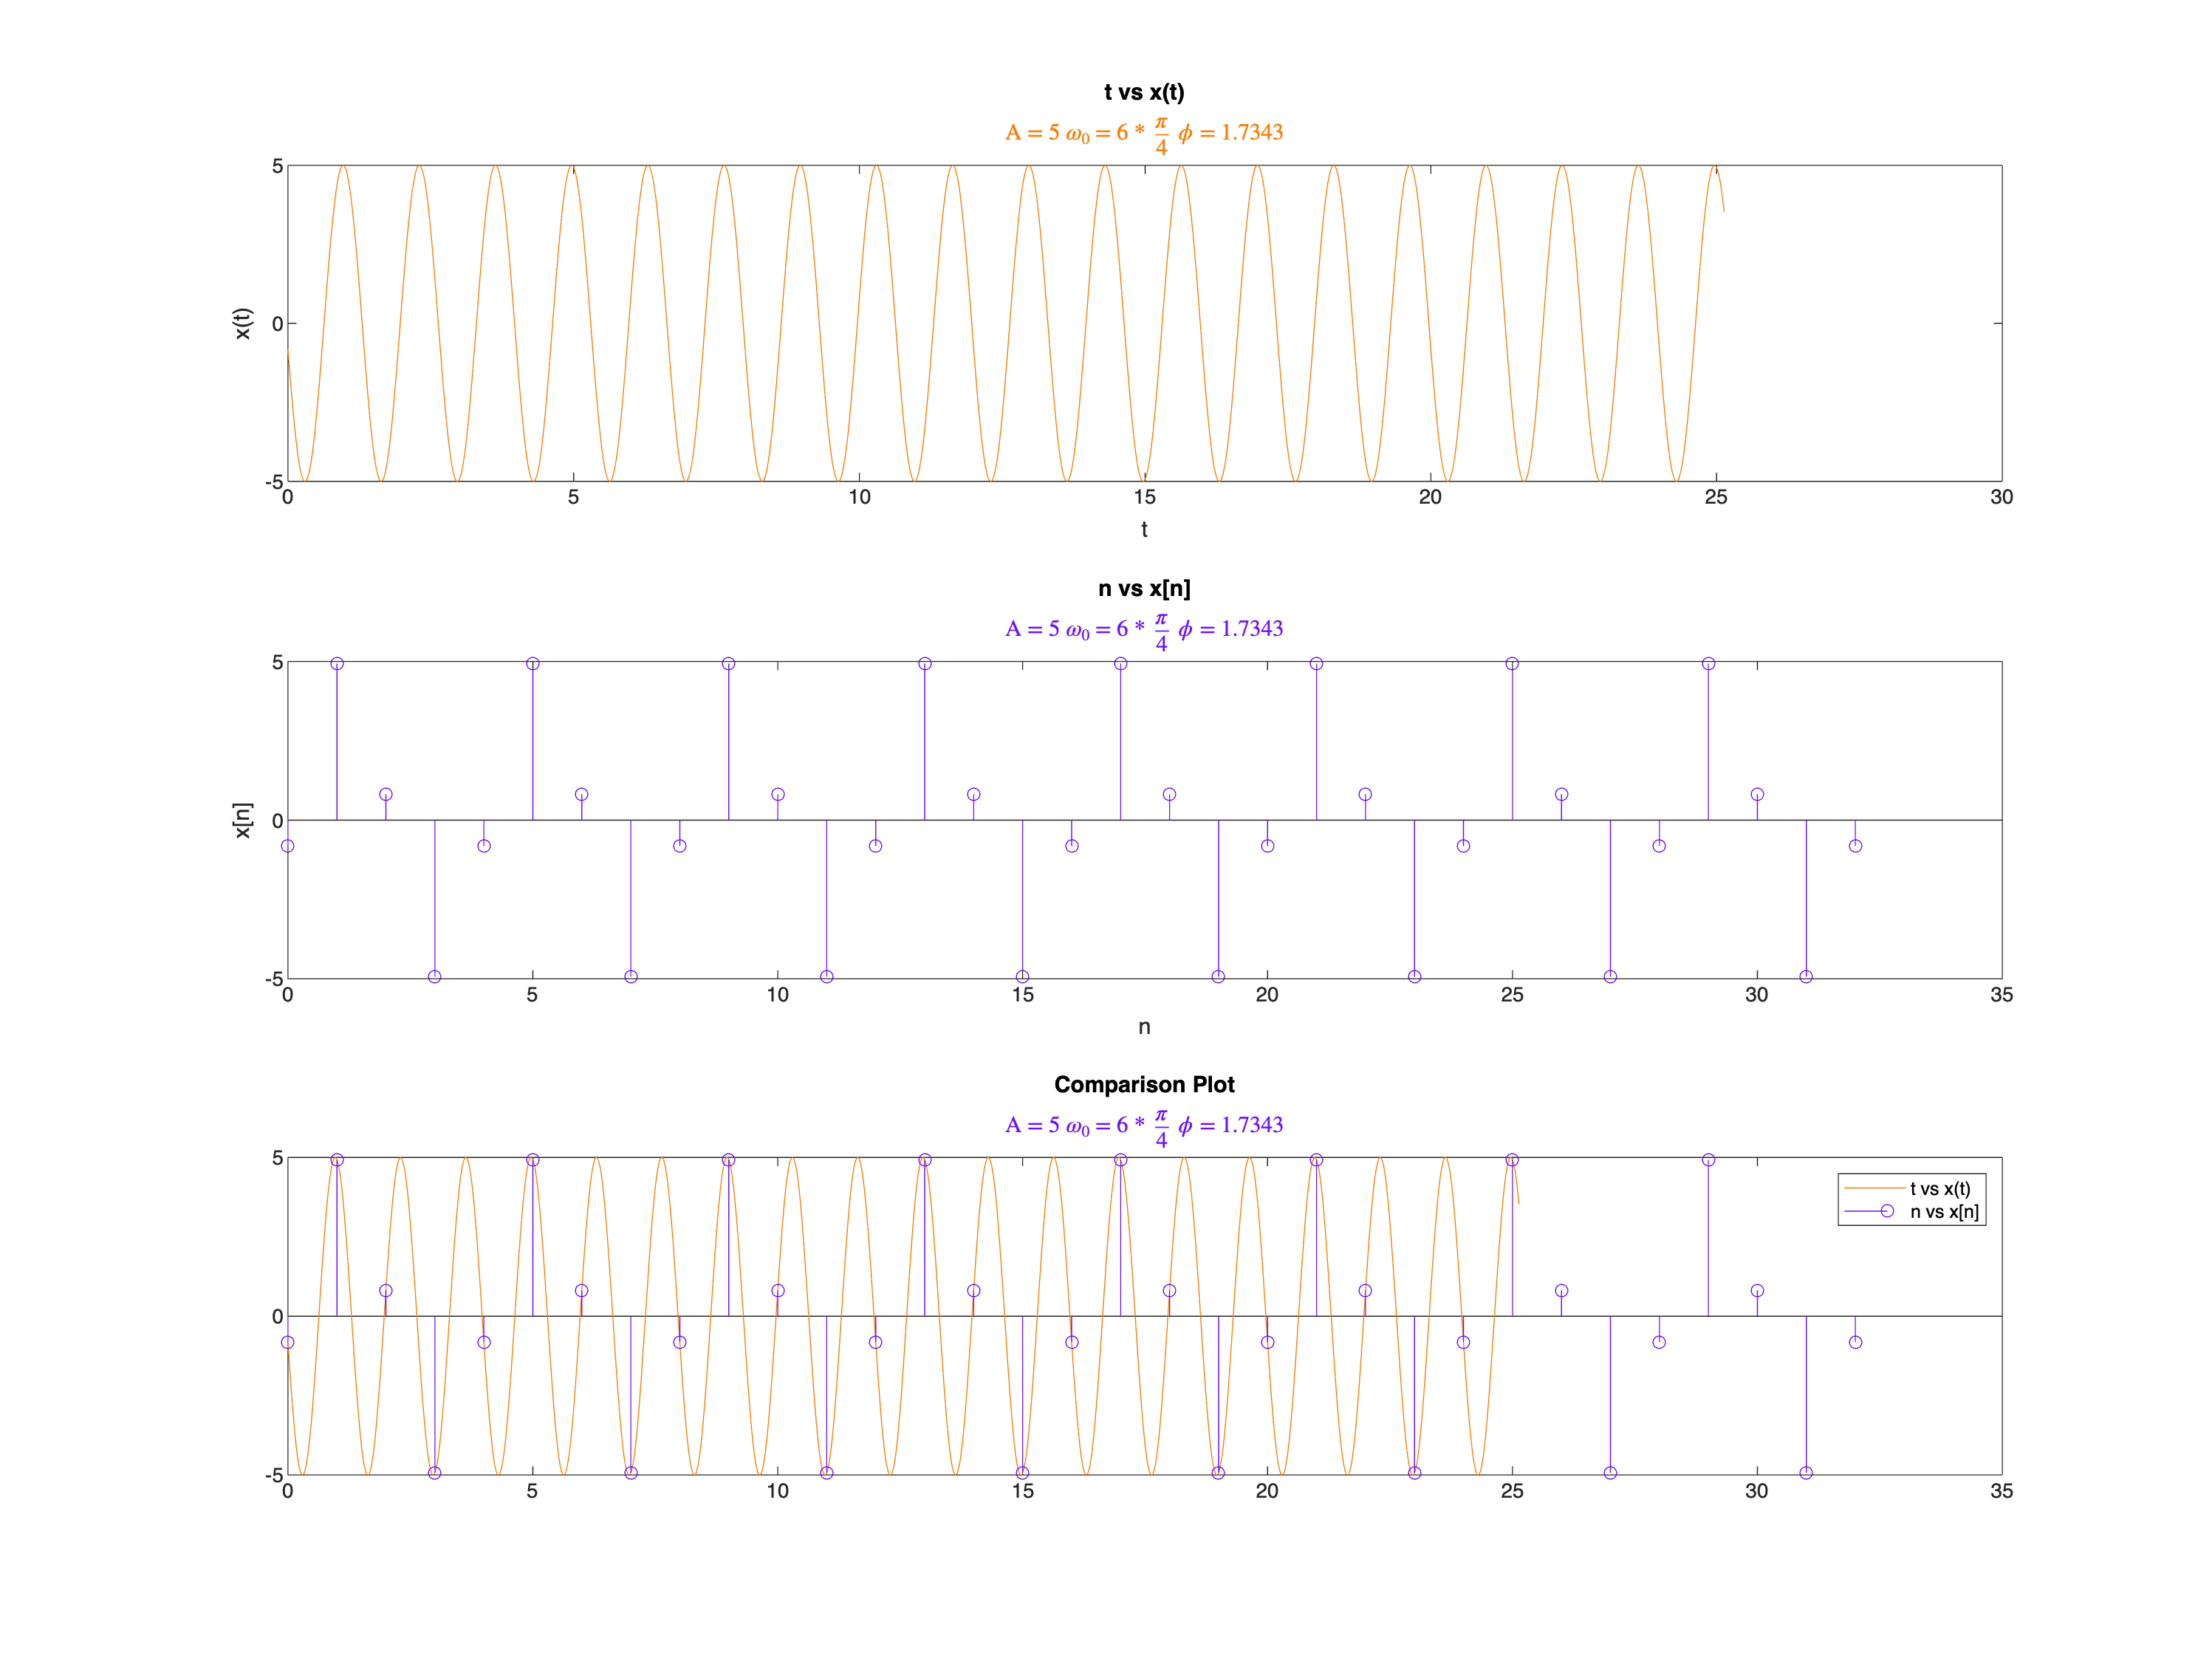

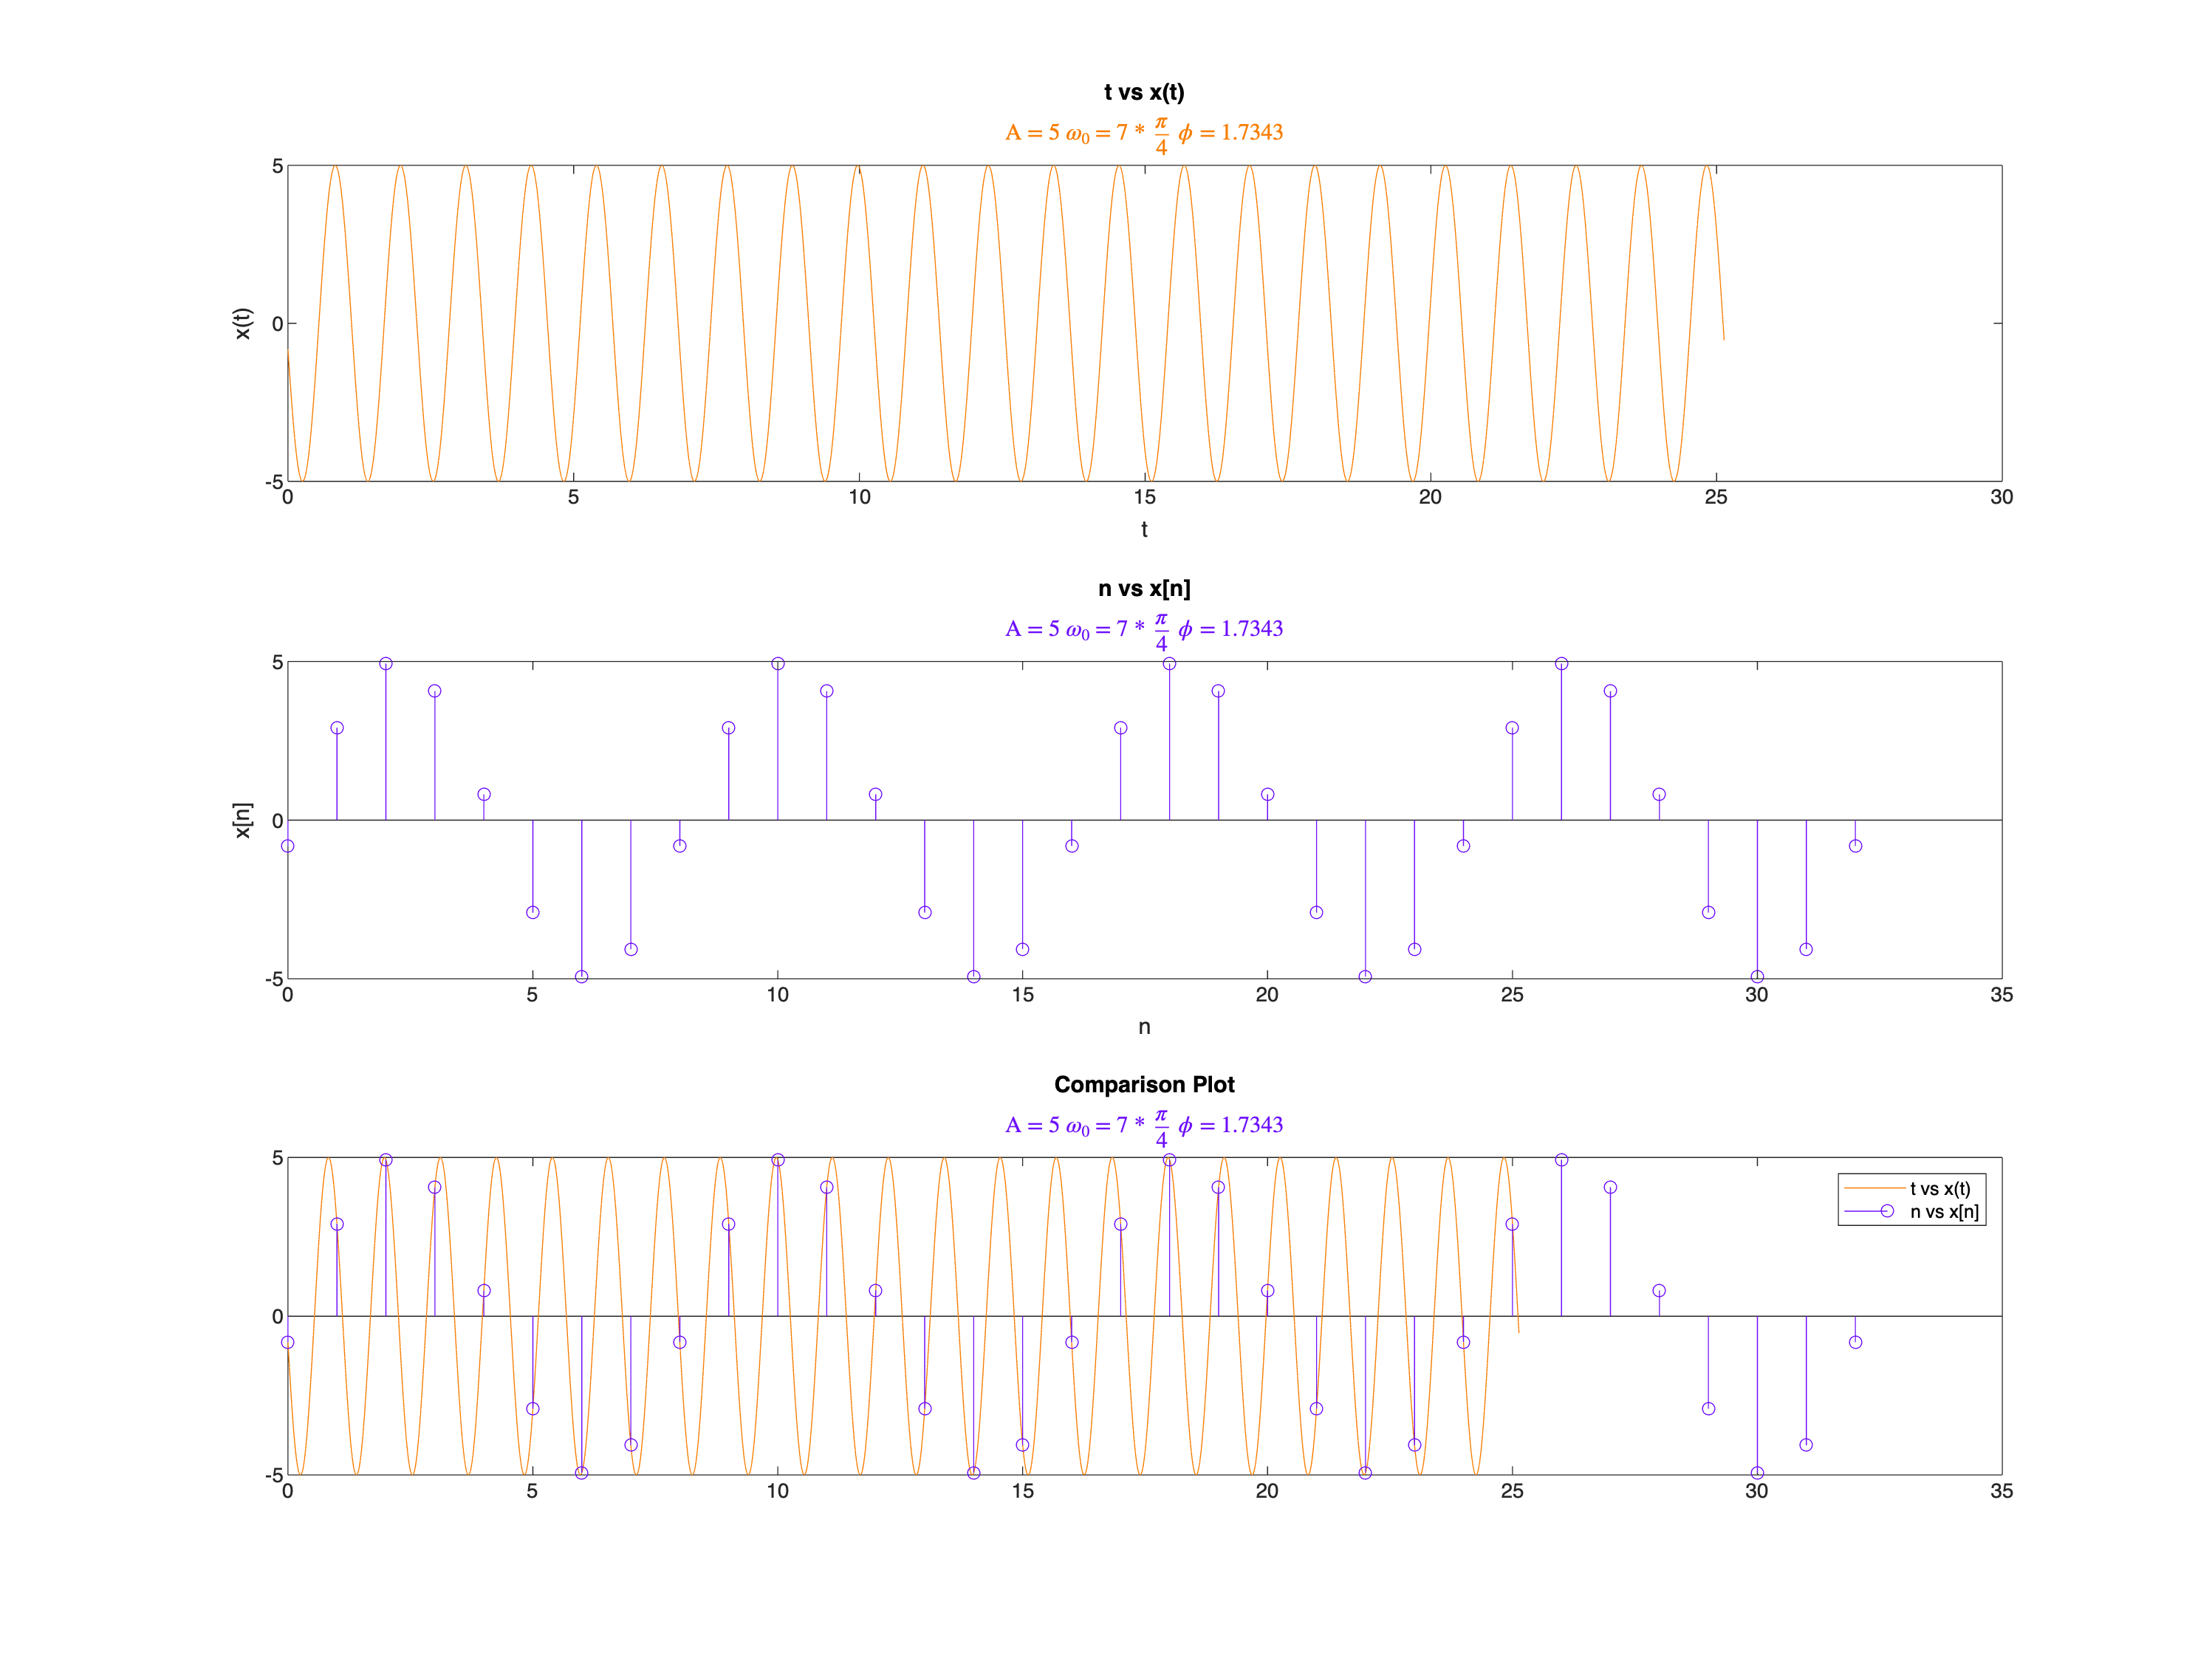

% Initialization of Required Variables
a = 5;
phi = rand() * 2 * pi;

% t for Continuous Time
t = 0:0.0001:8*pi;

% n for Discrete Time
n = 0:1:32;

for k = 0:8
    w0 = k * pi / 4;
    % Computing x_t and x_n
    x_t = a * cos((w0 * t) + phi);
    x_n = a * cos((w0 * n) + phi);
    
    % New Figure
    figure;
    
    %1st Subplot x(t)
    subplot(3,1,1);
    plot(t, x_t, Color = COLOUR_ORANGE);
    xlabel('t'); 
    ylabel('x(t)');
    %xlim([-1, 8*pi + 1]);
    %ylim([-6, 6])
    title('t vs x(t)');
    subtitle(['A = ' num2str(a) ' $\omega_0$ = ' num2str(k) ' * $\frac{\pi}{4}$ ' ' $\phi$ = ' num2str(phi)], Interpreter = 'latex', Color = COLOUR_ORANGE);
    
    figProps = gcf;
    figProps.Position(3:4) = figProps.Position(3:4) * 3;
    
    %2nd Subplot x[n]
    subplot(3,1,2);
    stem(n, x_n, Color = COLOUR_VIOLET);
    xlabel('n'); 
    ylabel('x[n]');
    %ylim([-6,6])
    %xlim([-1,33]);
    title('n vs x[n]');
    subtitle(['A = ' num2str(a) ' $\omega_0$ = ' num2str(k) ' * $\frac{\pi}{4}$ ' ' $\phi$ = ' num2str(phi)], Interpreter = 'latex', Color = COLOUR_VIOLET);
       
    %3rd Subplot x(t) & x[n]
    subplot(3,1,3);
    plot(t, x_t, Color = COLOUR_ORANGE);
    hold on;
    stem(n, x_n, Color = COLOUR_VIOLET);
    title("Comparison Plot");
    legend({'t vs x(t)' 'n vs x[n]'})
    subtitle(['A = ' num2str(a) ' $\omega_0$ = ' num2str(k) ' * $\frac{\pi}{4}$ ' ' $\phi$ = ' num2str(phi)], Interpreter = 'latex', Color = COLOUR_VIOLET);
end

**Observation:**

For discrete time sinusoid $$x_n = Acos(\omega_0n + \phi)$$ as $\omega_0
$ increases from $$[0, \pi]
$, $x_n
$ oscillates progressively and more rapidly. However as $\omega_0
$ increases from $[\pi, 2\pi]$ oscillation decreases and rapidity decreases.

**III. Periodicity**

Continuous Sinusoids:

(1) $$x_t = Acos(\frac{\pi}{4}t + \phi)$$

(2) $x_t = A cos(\frac{3\pi}{8}t + \phi)$

(3) $x_t = A cos(t + \phi)$

Discrete Sinusoids:

(1) $x[n] = Acos[\frac{\pi}{4}n + \phi]$

(2) $x[n] = Acos[\frac{3\pi}{8}n + \phi]$

(3) $x[n] = Acos[n + \phi]$

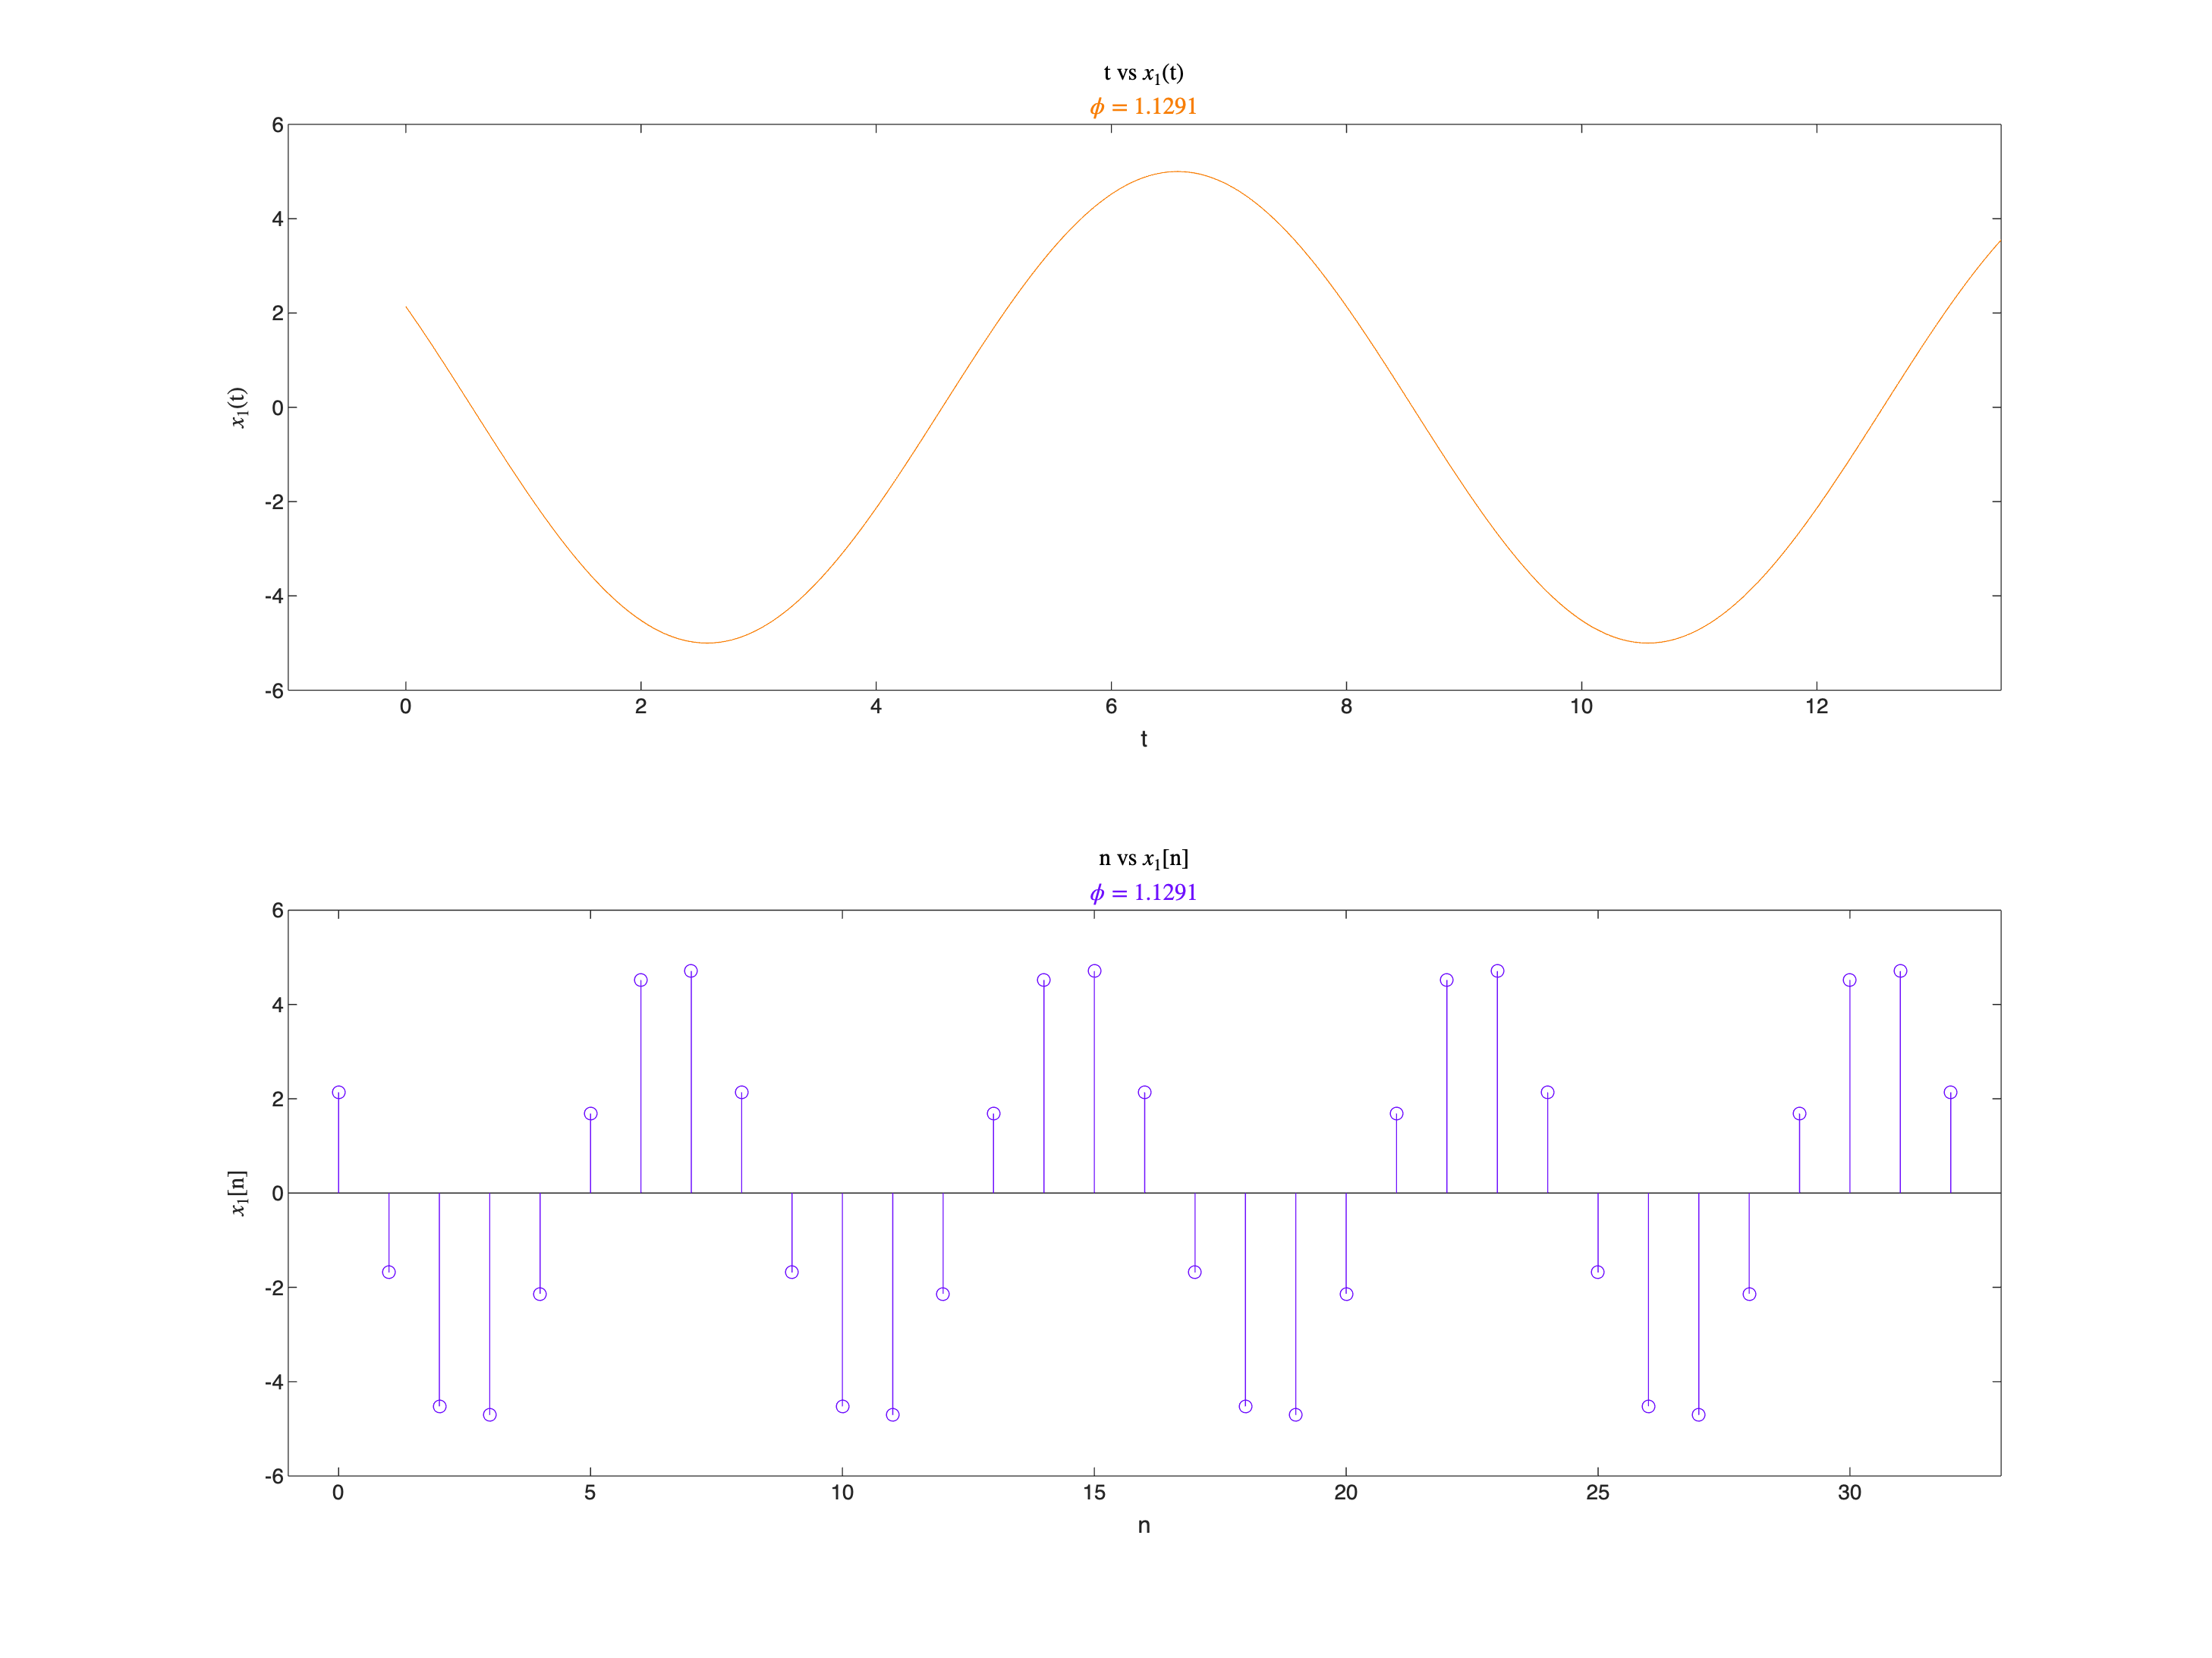

% Initialization of required variables
a = 5;
phi = -pi + rand() * 2 * pi;
t = 0:0.0001:8*pi;
n = 0:1:32;

% Computing of x(t) as given above
x1_t = a * cos(((pi/4) * t) + phi);
x2_t = a * cos(((3 * pi/8) * t) + phi);
x3_t = a * cos(t + phi);

% Computing of x[n] as given above
x1_n = a * cos(((pi/4) * n) + phi);
x2_n = a * cos(((3 * pi/8) * n) + phi);
x3_n = a * cos(n + phi);

% Plotting x1_t, x2_t, x3_t, x1_n, x2_n, x3_n

figure;
subplot(2,1,1);
plot(t, x1_t, Color = COLOUR_ORANGE);
xlabel("t"); 
ylabel("$x_1$(t)", Interpreter = "latex");
xlim([-1, 4*pi + 1]);
ylim([-6, 6])
title("t vs $x_1$(t)", Interpreter = "latex");
subtitle(['$\phi$ = ' num2str(phi)], Color = COLOUR_ORANGE, Interpreter = 'latex');

figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 2;

subplot(2,1,2);
stem(n, x1_n, Color = COLOUR_VIOLET);
xlabel("n"); 
ylabel("$x_1$[n]", Interpreter = "latex");
ylim([-6,6])
xlim([-1,33]);
title("n vs $x_1$[n]", Interpreter = "latex");
subtitle(['$\phi$ = ' num2str(phi)], Color = COLOUR_VIOLET, Interpreter = 'latex');

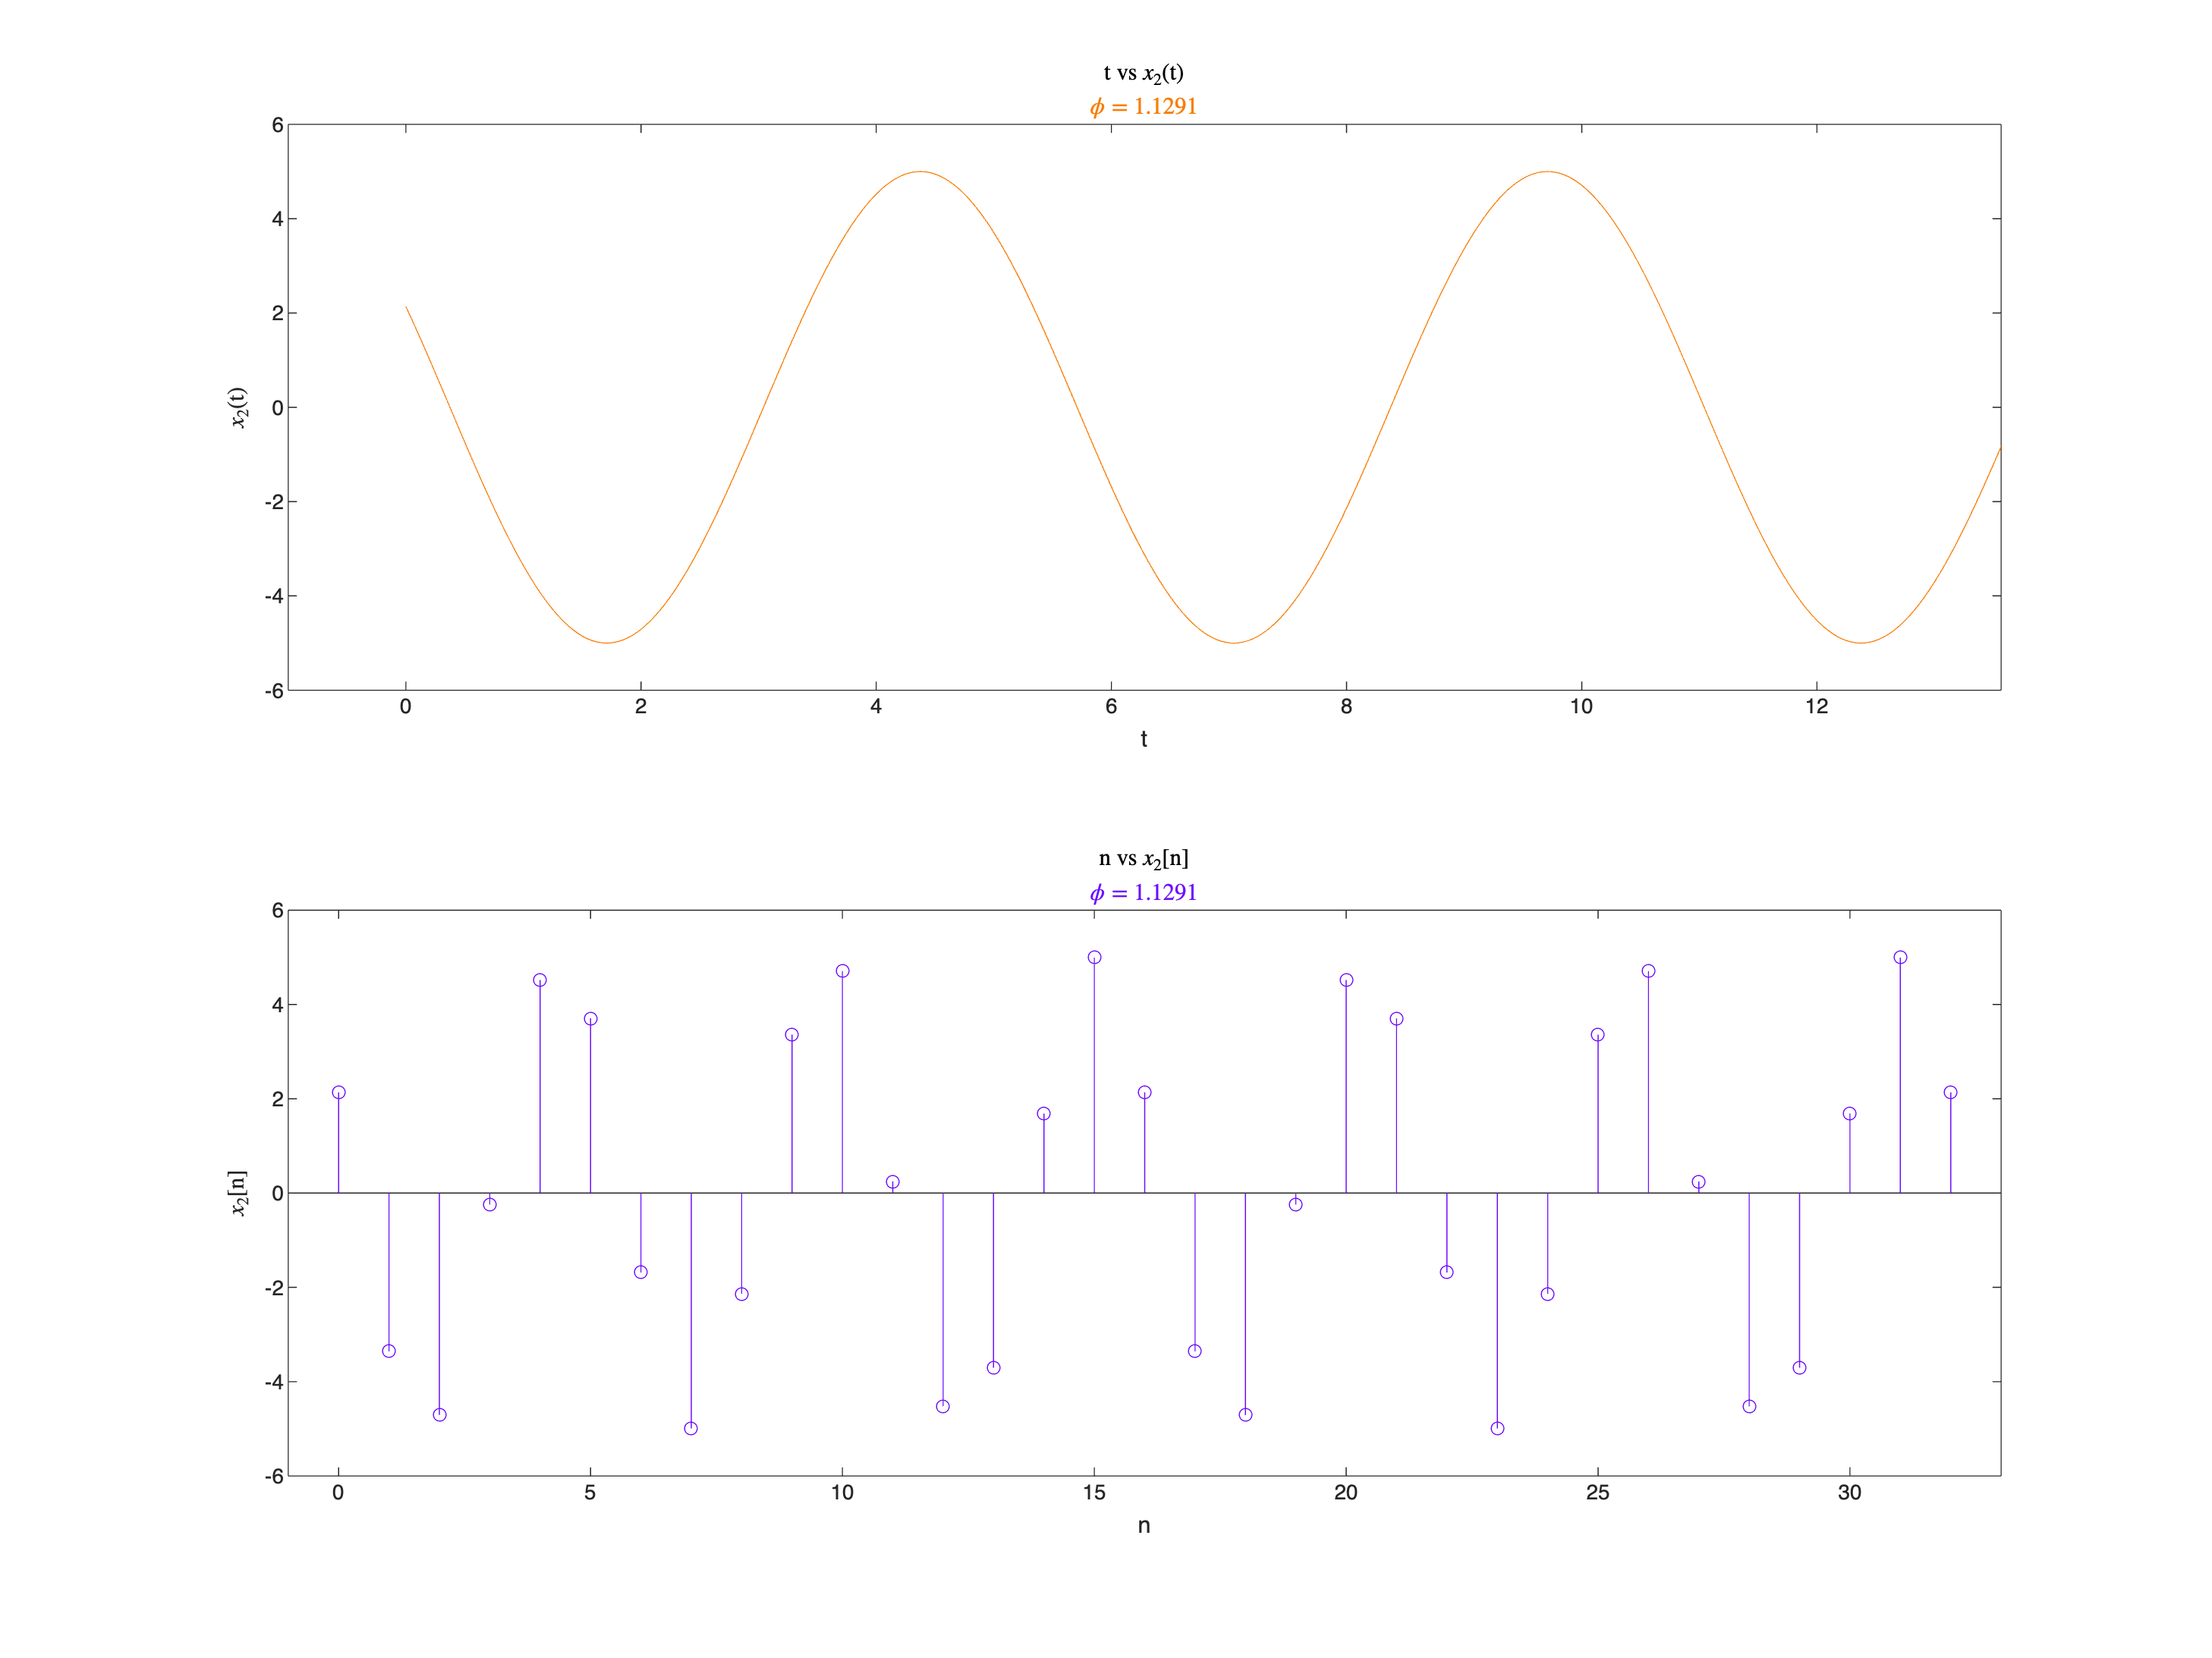


figure;
subplot(2,1,1);
plot(t, x2_t, Color = COLOUR_ORANGE);
xlabel("t"); 
ylabel("$x_2$(t)", Interpreter = "latex");
xlim([-1, 4*pi + 1]);
ylim([-6, 6])
title("t vs $x_2$(t)", Interpreter = "latex");
subtitle(['$\phi$ = ' num2str(phi)], Color = COLOUR_ORANGE, Interpreter = 'latex');

figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 2;

subplot(2,1,2);
stem(n, x2_n, Color = COLOUR_VIOLET);
xlabel("n"); 
ylabel("$x_2$[n]", Interpreter = "latex");
ylim([-6,6])
xlim([-1,33]);
title("n vs $x_2$[n]", Interpreter = "latex");
subtitle(['$\phi$ = ' num2str(phi)], Color = COLOUR_VIOLET, Interpreter = 'latex');

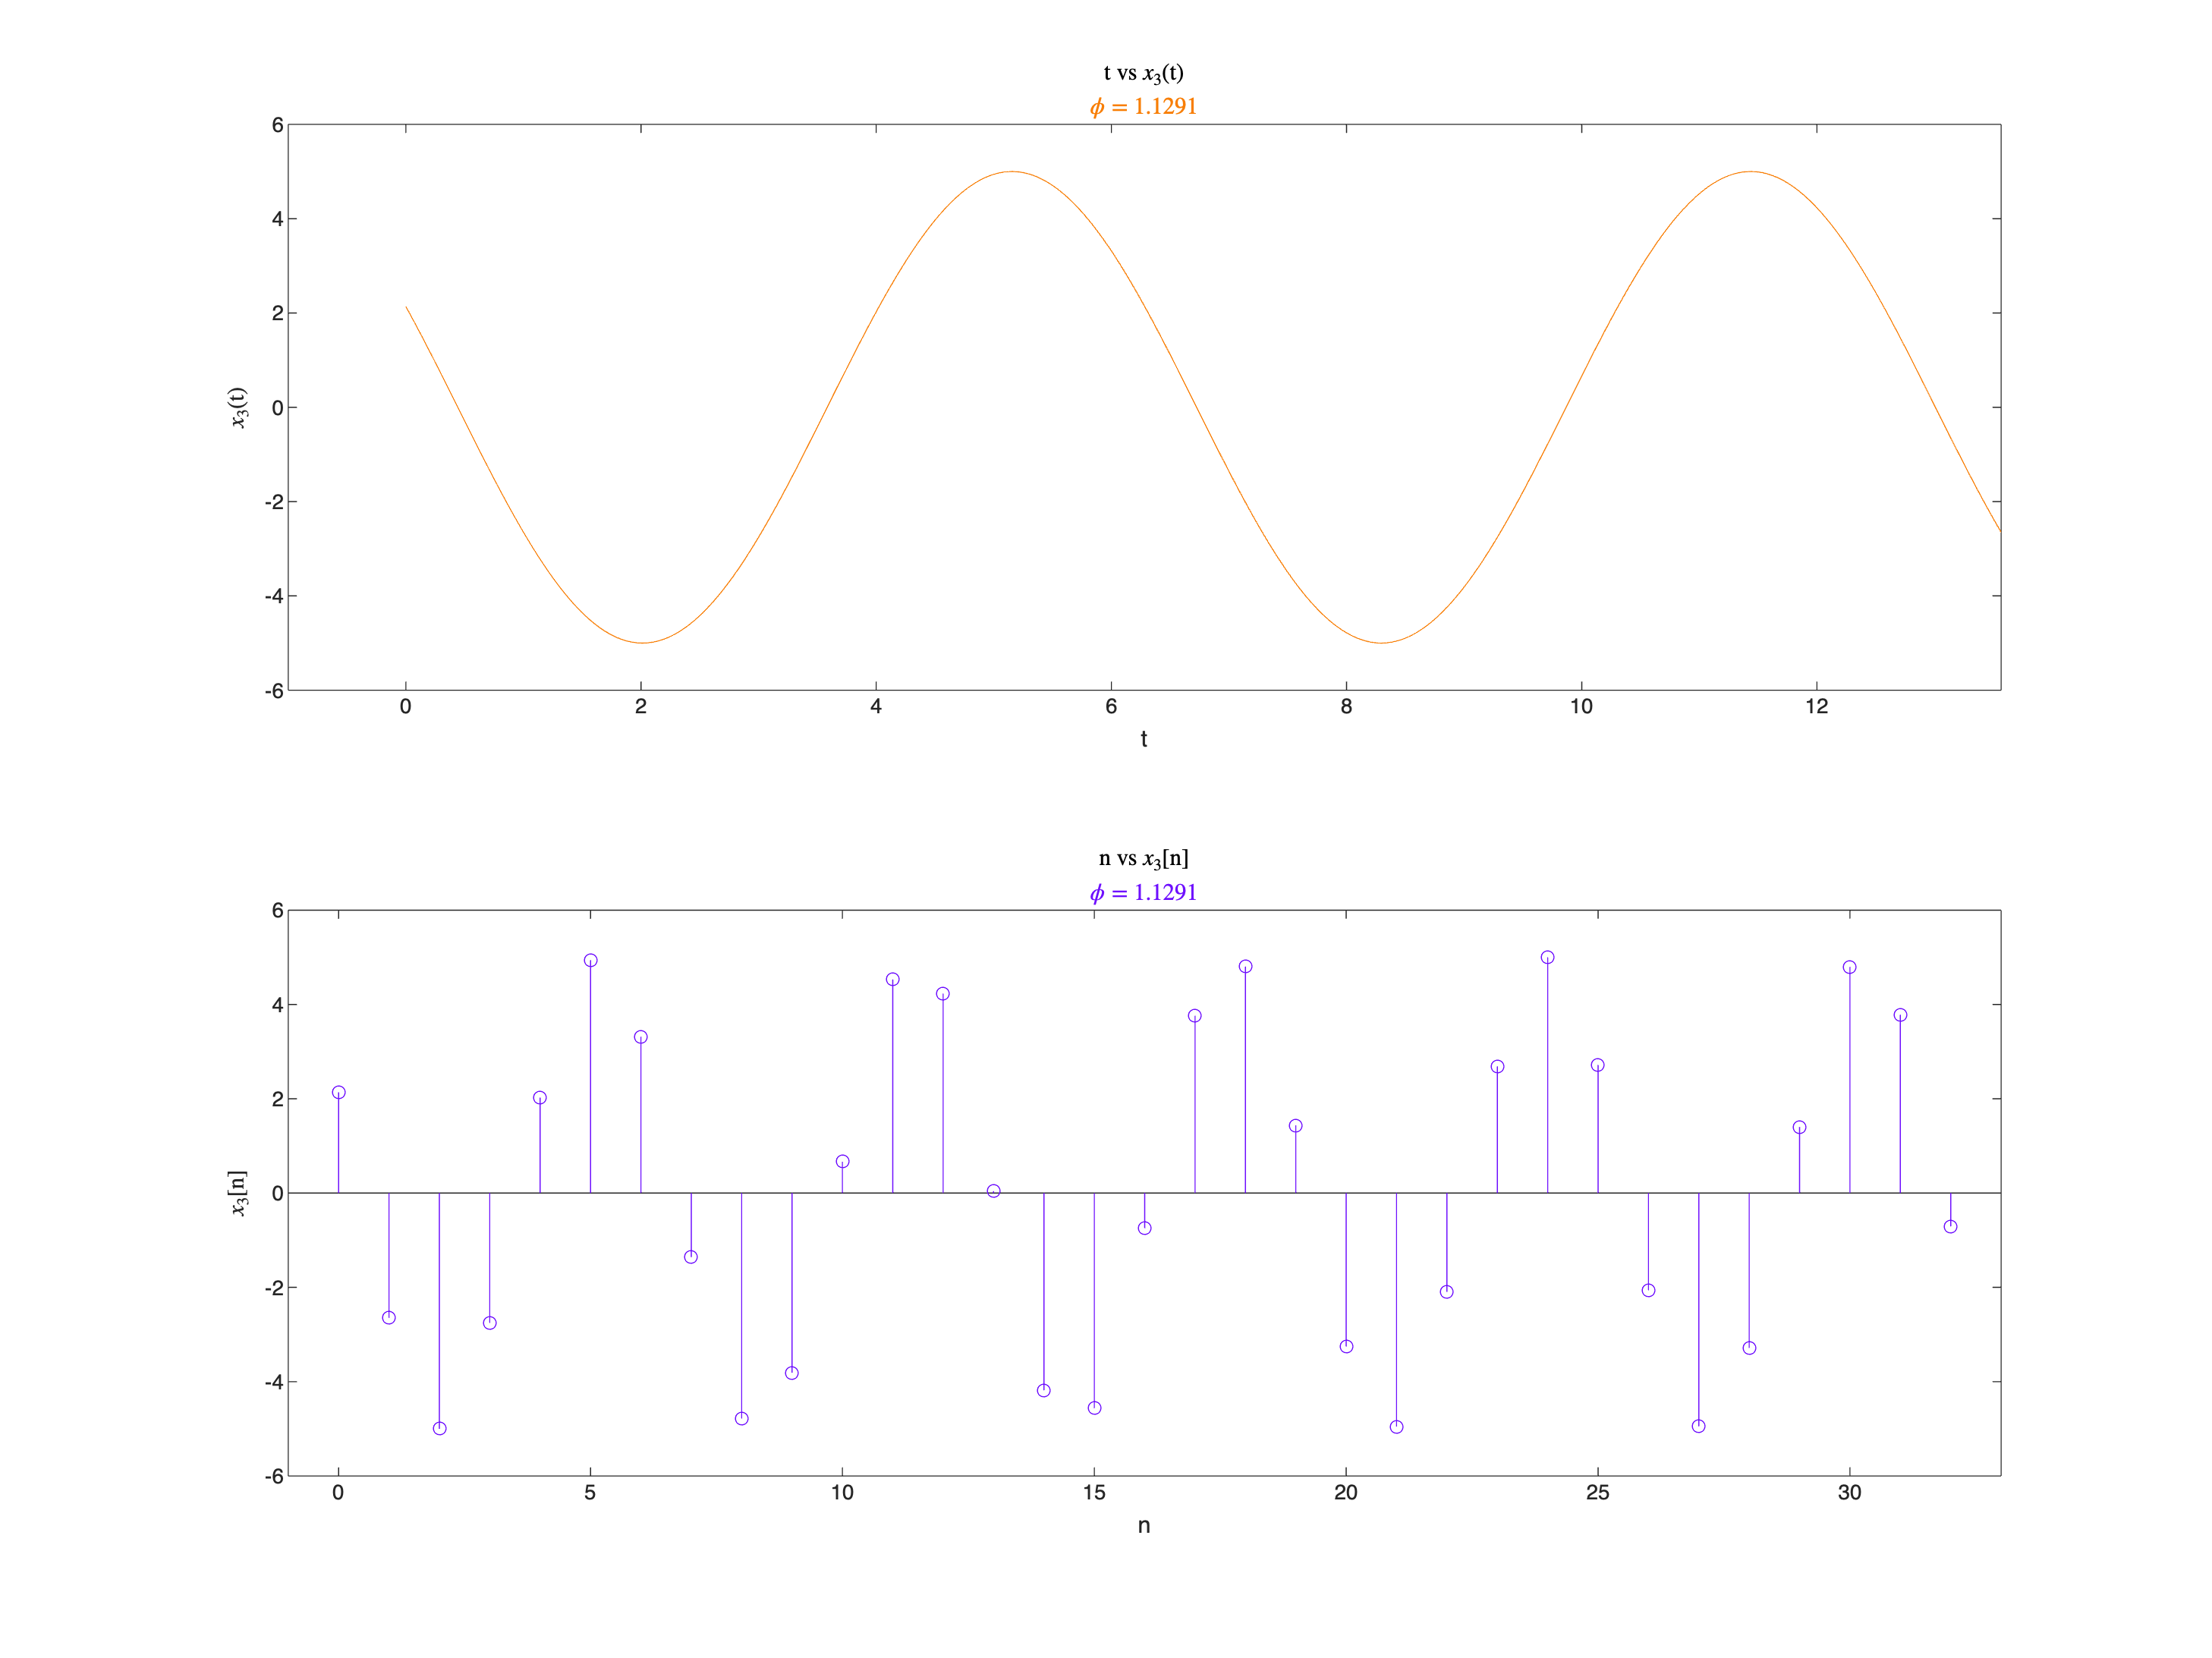


figure;
subplot(2,1,1);
plot(t, x3_t, Color = COLOUR_ORANGE);
xlabel("t"); 
ylabel("$x_3$(t)", Interpreter = "latex");
xlim([-1, 4*pi + 1]);
ylim([-6, 6])
title("t vs $x_3$(t)", Interpreter = "latex");
subtitle(['$\phi$ = ' num2str(phi)], Color = COLOUR_ORANGE, Interpreter = 'latex');

figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 2;

subplot(2,1,2);
stem(n, x3_n, Color = COLOUR_VIOLET);
xlabel("n"); 
ylabel("$x_3$[n]", Interpreter = "latex");
ylim([-6,6])
xlim([-1,33]);
title("n vs $x_3$[n]", Interpreter = "latex");
subtitle(['$\phi$ = ' num2str(phi)], Color = COLOUR_VIOLET, Interpreter = 'latex');

**Observation:**

Continuous time sinusoids are always periodic irrespective of what is the value of $\omega_0$. 

Thus Periods for Continuous time sinusoids given above are 

(1) $T_0
$ = 8 

(2) $T_0
$ = 16/3 

(3) $T_0
$ = $2\pi
$

Which is clearly concluded in the graph.

Discrete time sinusoids are periodic only if $\omega_0$ is an integral multiple of $\frac{2\pi}{N}$.

Thus N for Discerete time sinusoids given above are 

(1) N  = 8, $T_0
$ = 8 

(2) N = 16, $T_0
$ = 16/3 

(3) N = (Not Any Integer) thus it is not periodic. 

Which is concluded by the last graph.

**B. Exponential Sequences**

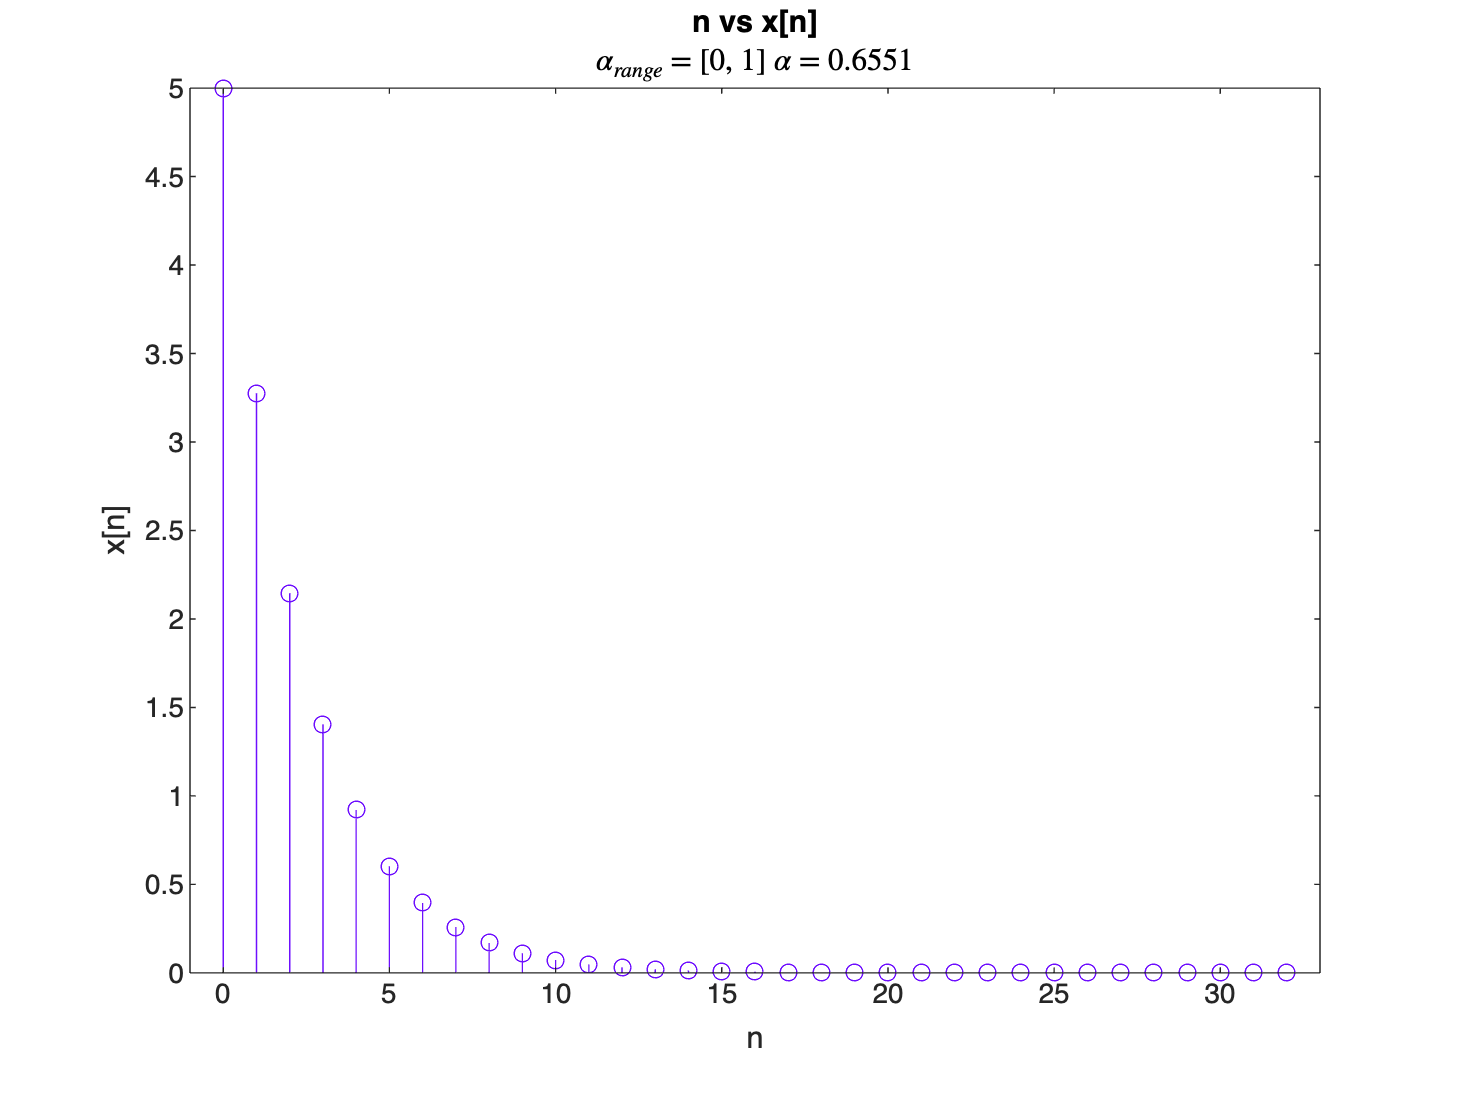

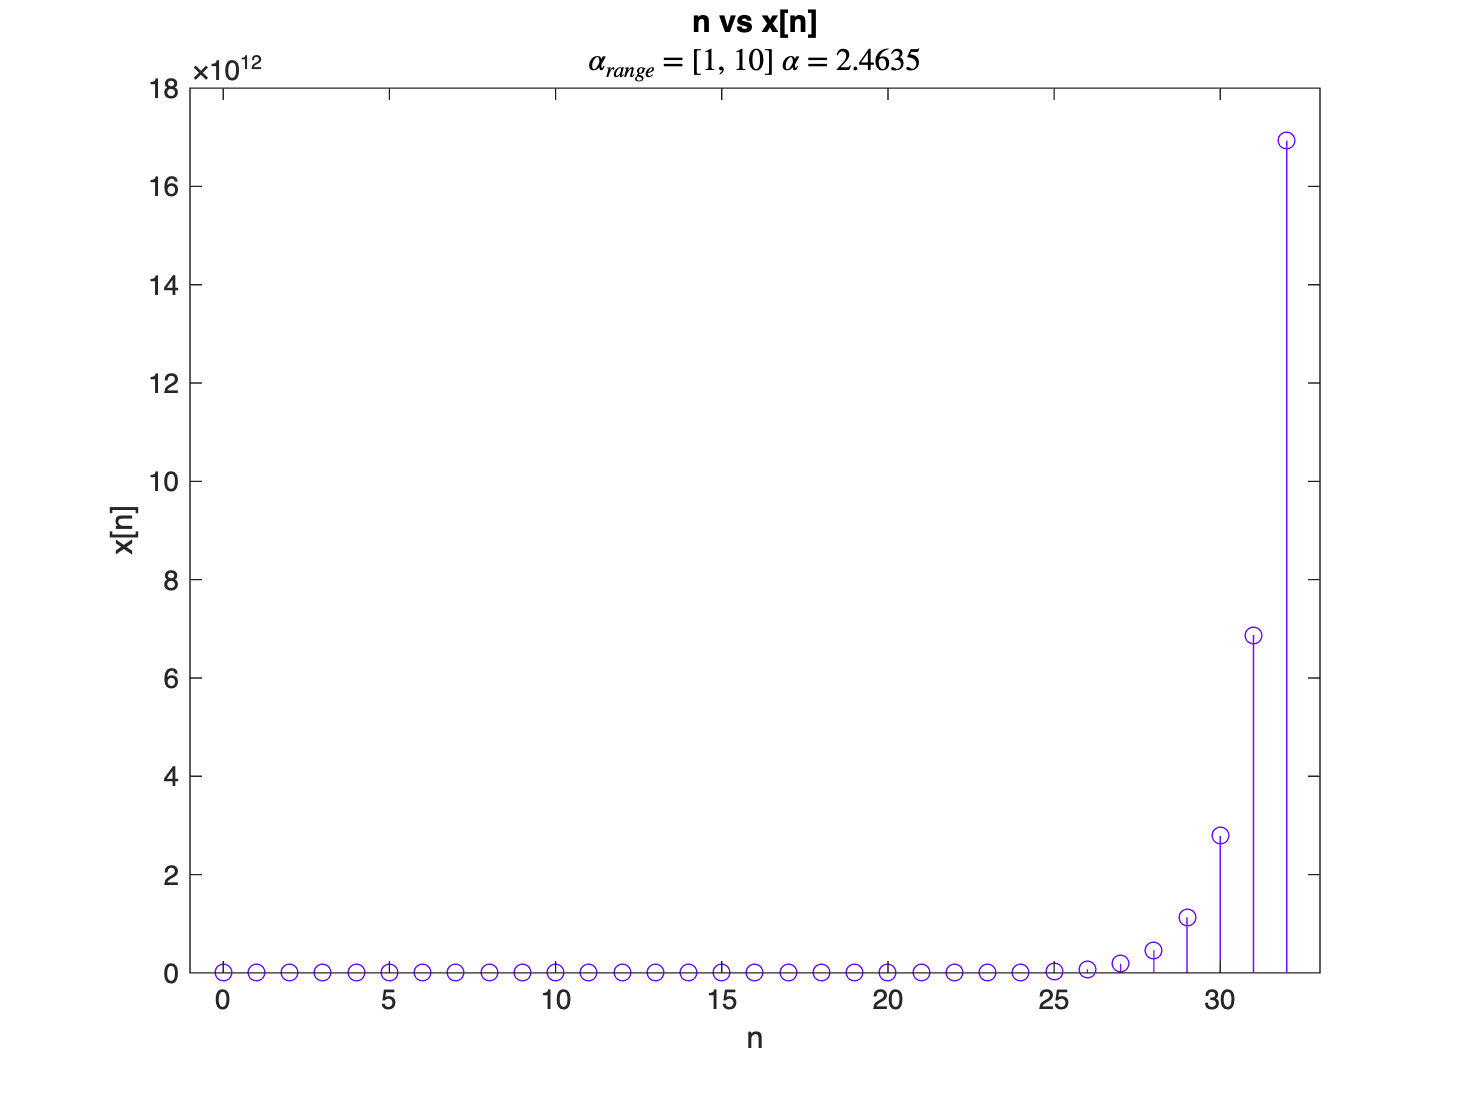

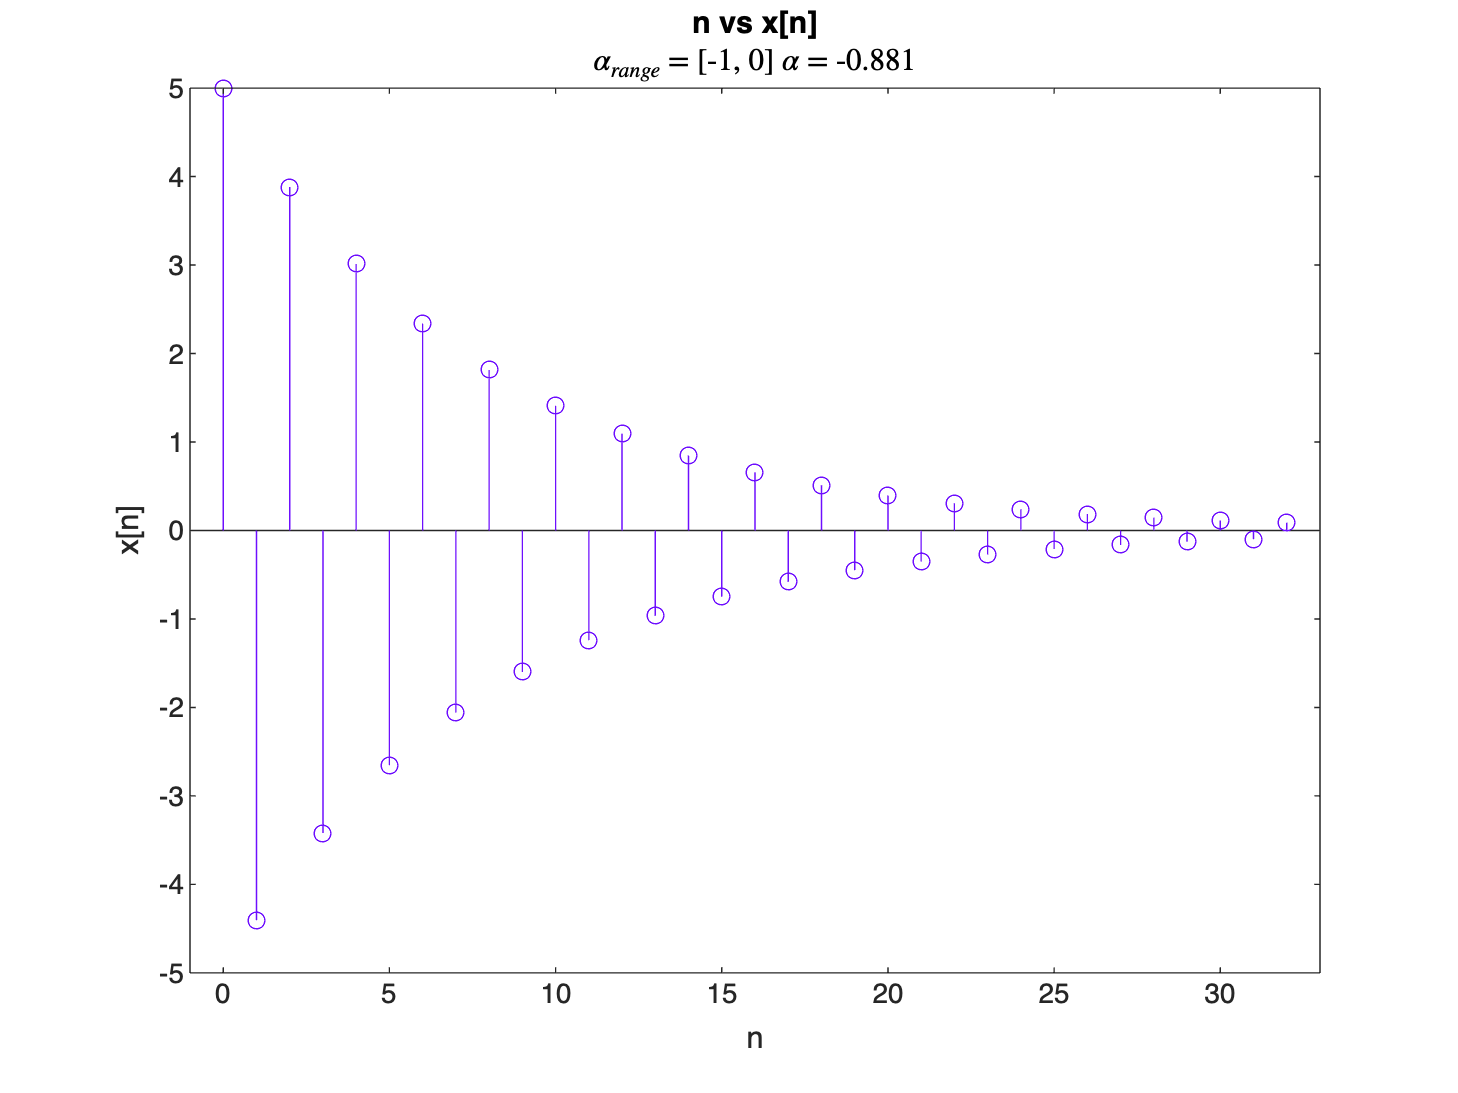

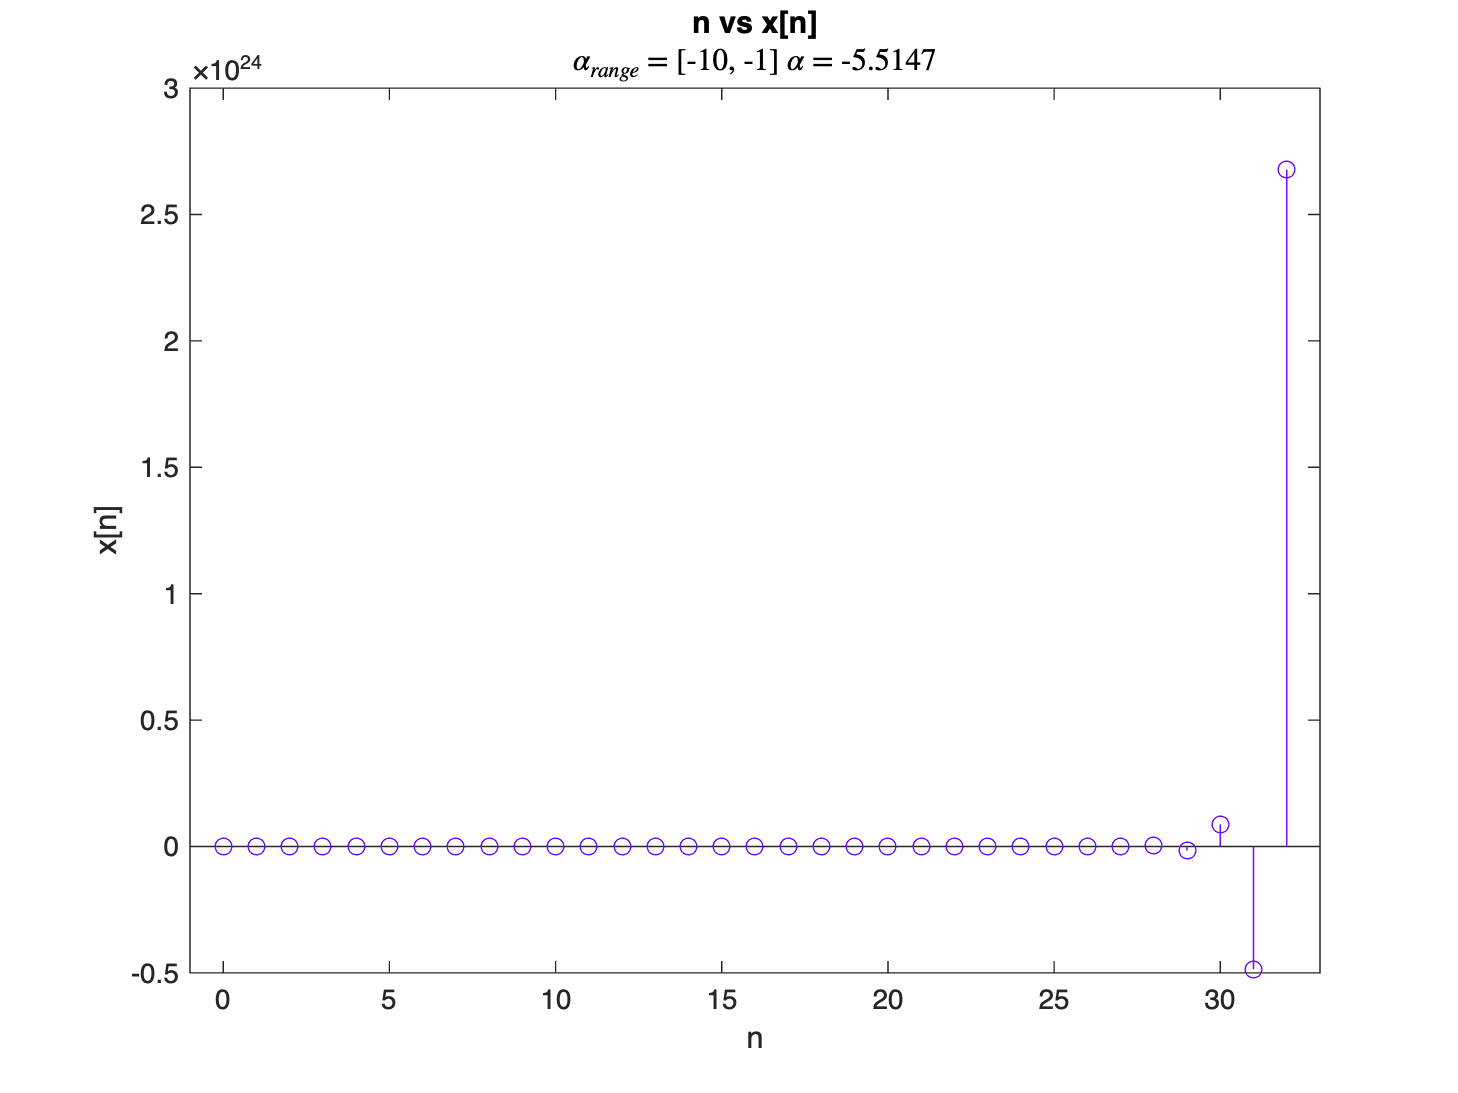

% Initialization of Required Variables
a = 5;
n = 0:1:32;

alphaRange = [0, 1; 1, 10; -1, 0; -10, -1];

% Alpha generation and plotting
for i = 1:size(alphaRange, 1)
    alpha = alphaRange(i, 1) + ((alphaRange(i, 2) - alphaRange(i, 1)) * rand());
    
    figure;
    x_n = a * (alpha .^ n);
    stem(n, x_n, Color = COLOUR_VIOLET);
    xlabel('n'); 
    ylabel('x[n]');
    xlim([-1,33]);
    title('n vs x[n]');
    subtitle(['$\alpha_{range}$ = [' num2str(alphaRange(i, 1)) ', ' num2str(alphaRange(i, 2)) '] $\alpha$ = ' num2str(alpha)], 'Interpreter', 'latex');
end

**C. Complex Sinusoids and Exponentials**

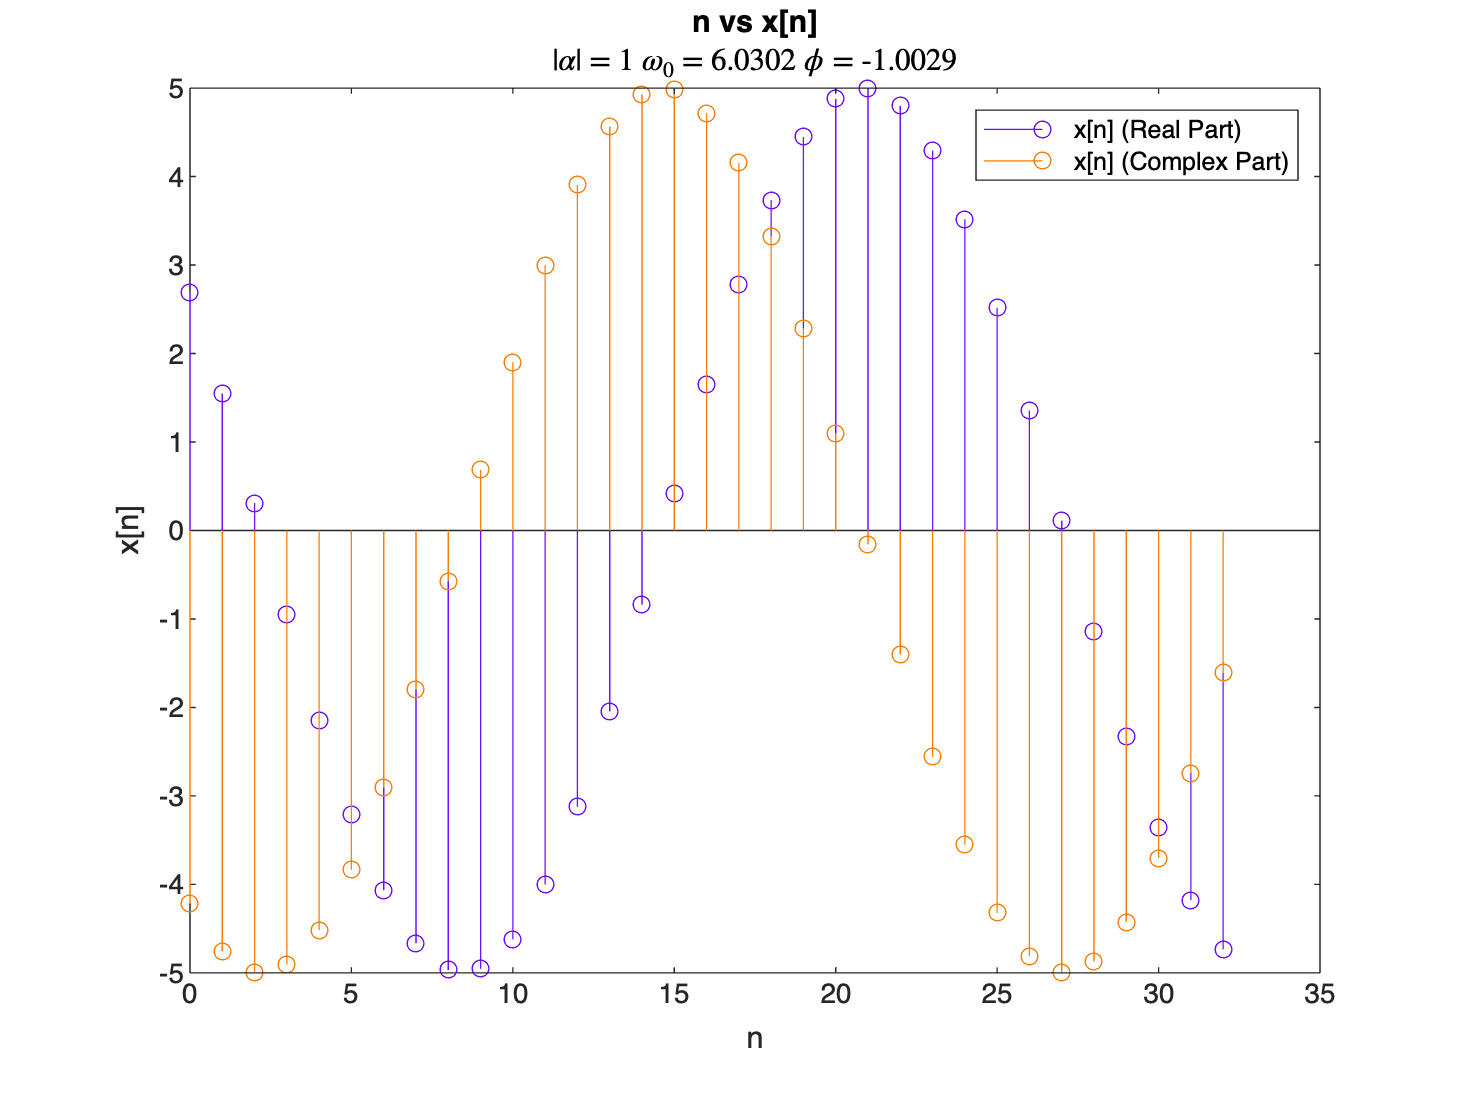

% Function for sketching Real and Complex parts of exponential based on the
% given alpha value
function sketchDecomposedExponential(alpha)
    modA = 5;
    w0 = rand() * 2 * pi;
    phi = -pi + rand() * 2 * pi;
    n = 0:1:32;

    figure;
    x_nReal = modA * (alpha .^ n) .* cos(((w0 * n) + phi));
    x_nComplex = modA * (alpha .^ n) .* sin(((w0 * n) + phi));

    stem(n, x_nReal, Color = "#6E0FFE");
    hold on;
    stem(n, x_nComplex, Color = "#F87E05");
    xlabel('n'); 
    ylabel('x[n]');
    legend({'x[n] (Real Part)', 'x[n] (Complex Part)'});
    title('n vs x[n]');
    subtitle(['|$\alpha$| = ' num2str(alpha) ' $\omega_0$ = ' num2str(w0) ' $\phi$ = ' num2str(phi)], Interpreter = 'latex');

end

modAlpha = 1;

sketchDecomposedExponential(modAlpha);

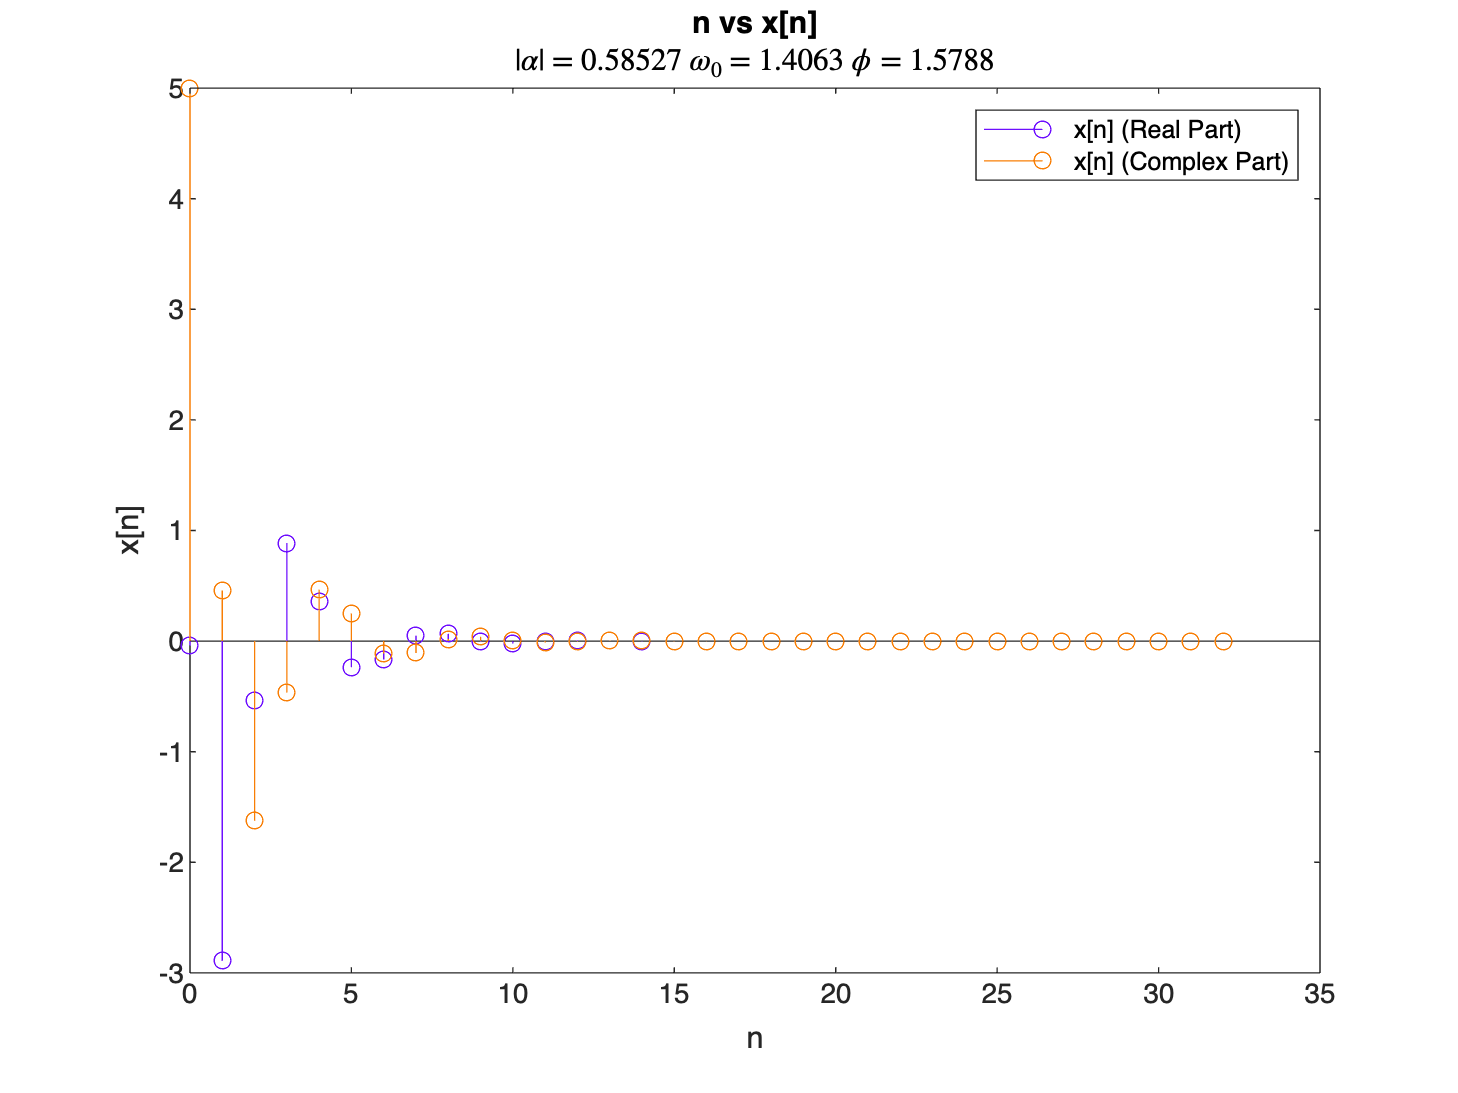


modAlpha = 0 + (1-0) * rand();

sketchDecomposedExponential(modAlpha);

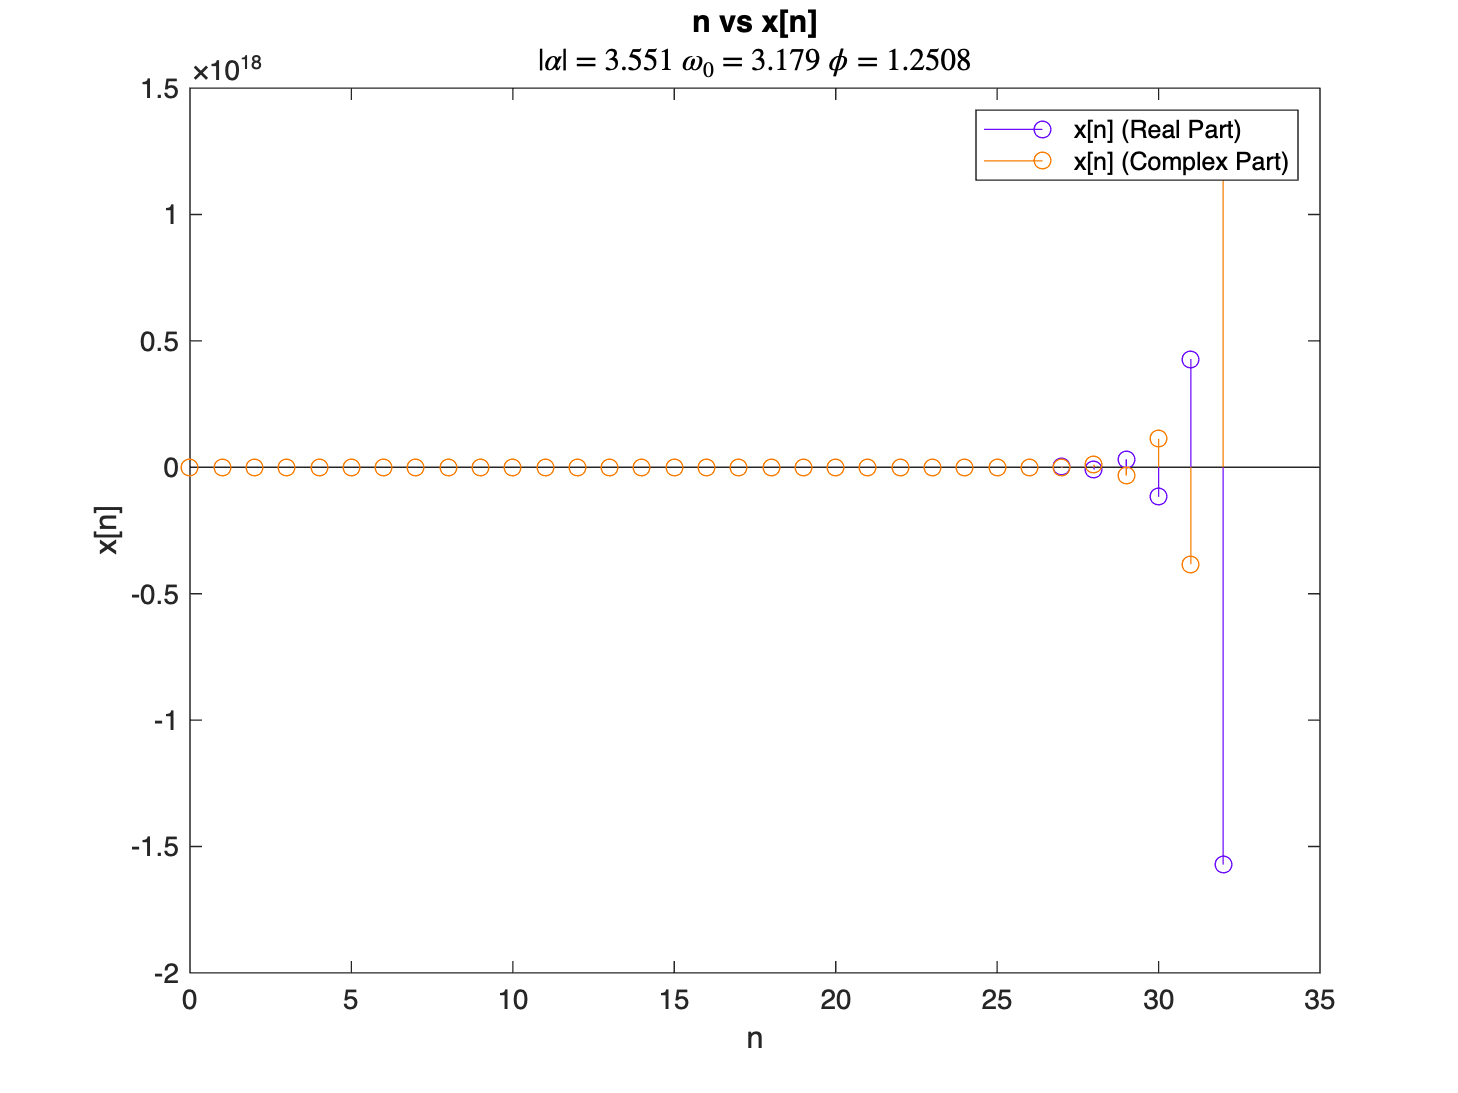


modAlpha = 1 + (10 - 0) * rand();

sketchDecomposedExponential(modAlpha);